# Réseaux de neurones : Étude du jeu de données Fashion MNIST

## Introduction

Les réseaux de neurones artificiels sont des modèles informatiques inspirés du fonctionnement du cerveau humain. Ces modèles sont conçus pour traiter l'information de manière similaire à un réseau de neurones biologiques. Chaque "neurone" artificiel, ou unité, est connecté à d'autres par des poids, qui ajustent la force et la direction des connexions. Ces réseaux sont particulièrement utilisés dans le domaine de l'apprentissage automatique et de l'intelligence artificielle.

Dans cet environnement d'apprentissage automatique, MATLAB propose le "Deep Learning Toolbox", une boîte à outils puissante qui facilite la création, l'entraînement et l'évaluation des réseaux de neurones. À travers cet outil, les utilisateurs peuvent explorer les nuances fascinantes des réseaux de neurones pour résoudre une variété de problèmes, de la reconnaissance d'images à la prédiction de séquences temporelles.

Nous avons pour but d'explorer l'influence de divers paramètres sur l'optimisation d'un réseau de neurones en recourant à un protocole de benchmark. Cette investigation s'inscrit dans le cadre de l'analyse des jeux de données MNIST et MNIST Fashion.

## Chargement et présentation des jeux de données MNIST et Fashion MNIST

Nous avons pris la décision de diviser, de façon aléatoire, nos jeux de données en trois ensembles distincts : entraînement, validation et prédiction. Ces subdivisions respectives représentent 70%, 20% et 10% des ensembles de données initiaux. Cette approche répond à plusieurs objectifs cruciaux dans le processus d'entraînement et d'évaluation de notre modèle de réseau de neurones.

L'ensemble d'entraînement (70%) est utilisé pour l'apprentissage effectif du modèle. Les poids du réseau sont ajustés à l'aide de ces données, permettant au modèle d'apprendre les motifs et les caractéristiques représentatifs du problème.

L'ensemble de validation (20%) est utilisé pour évaluer la performance du modèle pendant l'entraînement. À des intervalles spécifiés, le modèle est évalué sur cet ensemble pour estimer sa capacité à généraliser à des données qu'il n'a pas vu pendant l'apprentissage. Cela aide à ajuster les hyperparamètres et à détecter tout surajustement potentiel.

L'ensemble de prédiction (10%) est réservé pour évaluer la performance finale du modèle une fois l'entraînement terminé. Il représente des données que le modèle n'a jamais rencontrées auparavant, ce qui permet d'estimer sa capacité à généraliser à de nouvelles observations.

La division en ensembles d'entraînement, de validation et de prédiction contribue à garantir une évaluation robuste du modèle. En utilisant des ensembles distincts, nous évitons le risque de surajustement, où le modèle pourrait simplement mémoriser les données d'entraînement sans développer une capacité de généralisation. Cela favorise une meilleure évaluation de la performance du modèle dans des conditions réelles et améliore sa capacité à traiter de nouvelles données.

### MNIST : Modified National Institute of Standards and Technology

%Chargement du jeu de donnée MNIST
mnist = imageDatastore("DatasetMNIST/MNIST Dataset JPG format/MNIST - JPG - training","IncludeSubfolders",true,"LabelSource","foldernames");
[mnistTrain, mnistValidation ,mnistPrediction] = splitEachLabel(mnist,0.7,0.2,0.1,'randomized');

% Resize the images to match the network input layer MNIST
augmnistsTrain = augmentedImageDatastore([28 28 1],mnistTrain);
augmnistValidation = augmentedImageDatastore([28 28 1],mnistValidation);
augmnistPrediction = augmentedImageDatastore([28 28 1],mnistPrediction);

Le jeu de données MNIST, acronyme de "Modified National Institute of Standards and Technology", constitue l'un des ensembles de données les plus emblématiques dans le domaine de l'apprentissage automatique. Composé de 60 000 images en noir et blanc d'écriture manuscrite de chiffres de 0 à 9, MNIST sert de référence pour l'évaluation des algorithmes de reconnaissance d'images. Chaque image, d'une résolution de 28x28 pixels, représente un chiffre unique et est accompagnée d'une étiquette indiquant la classe à laquelle il appartient.

L'utilité majeure de MNIST réside dans sa simplicité et sa facilité d'utilisation. Les chercheurs et les praticiens l'emploient généralement comme point de départ pour tester de nouveaux modèles de réseaux de neurones et d'autres techniques d'apprentissage automatique en raison de sa taille gérable et de sa représentation visuelle claire.

Nous allons utiliser le jeu de données MNIST comme base d'entraînement et d'optimisation pour nos divers modèles de réseau de neurones.

### FMNIST : Fashion Modified National Institute of Standards and Technology

%Chargement du jeu de donnée Fashion MNIST
Fmnist = imageDatastore("zalando/train/","LabelSource","foldernames","FileExtensions",".png","IncludeSubfolders",true);
[FmnistTrain, FmnistValidation ,FmnistPrediction] = splitEachLabel(Fmnist,0.7,0.2,0.1,'randomized');

% Resize the images to match the network input layer Fashion MNIST
augFmnistsTrain = augmentedImageDatastore([28 28 1],FmnistTrain);
augFmnistValidation = augmentedImageDatastore([28 28 1],FmnistValidation);
augFmnistPrediction = augmentedImageDatastore([28 28 1],mnistPrediction);

Le jeu de données Fashion MNIST se présente comme une extension captivante du célèbre ensemble de données MNIST. Conçu comme un substitut moderne, il offre un défi intéressant en remplaçant les chiffres manuscrits par une collection variée de vêtements et d'accessoires de mode. Composé de 70 000 images en noir et blanc, Fashion MNIST propose 10 catégories distinctes, chacune correspondant à un type spécifique de vêtement : 

- T-shirt/top

- Pantalon

- Pullover

- Robe

- Manteau

- Sandale

- Chemise

- Basket

- Sac à main

- Bottine

Chaque image, d'une résolution de 28x28 pixels, représente visuellement un vêtement unique. La diversité des catégories et la nature complexe des motifs rendent Fashion MNIST particulièrement pertinent pour tester et améliorer les performances des modèles de réseau de neurones dans un contexte de classification d'images comme celui-ci.

Notre but est d'optimiser un modèle de réseau de neurones spécifiquement pour la classification d'images provenant du jeu de données Fashion MNIST (FMNIST).

## 0) Premier réseau de neurones

Pour amorcer notre démarche, nous avons initié plusieurs tests (non-représentés) visant à identifier un réseau de neurones présentant des performances initiales acceptables. Cette première étape vise à établir une base fonctionnelle sur laquelle nous pouvons ensuite apporter des améliorations.

En sélectionnant un modèle de départ avec des performances correctes, nous minimisons le risque d'optimiser un réseau de neurones à partir de paramètres inadéquats. Cette approche méthodique nous guide vers une optimisation ciblée visant à affiner et améliorer continuellement les performances du réseau de neurones.

### Train

Nous nous apprêtons maintenant à entamer la phase d'entraînement du modèle que nous avons identifié par tâtonnement. Le choix d'initier l'entraînement avec un modèle découvert par tâtonnement repose sur le principe d'optimisation progressive. Cette approche itérative permet d'explorer efficacement l'espace des paramètres du modèle, amenant progressivement le réseau de neurones vers des performances de classification optimales pour le jeu de données Fashion MNIST.

layers1 = [
    imageInputLayer([28 28 1])
    fullyConnectedLayer(256)
    reluLayer
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer
    ];
%layers1 représente l'architecture de notre premier réseau de neurones

Nous avons donc élaboré un premier réseau de neurones spécifiquement pour résoudre le défi de classification inhérent au jeu de données Fashion MNIST. L'architecture du réseau repose sur une séquence de couches de neurones.

La première couche, appelée `imageInputLayer`, joue le rôle d'interface d'entrée pour nos données, étant configurée en accord avec les dimensions spécifiques des images que nous traitons : des images de revêtements noir et blanc de taille 28x28 pixels. En suivant, une couche entièrement connectée, `fullyConnectedLayer`, avec 256 neurones, a été introduite pour permettre au réseau d'apprendre des représentations complexes des caractéristiques présentes dans les images.

Nous retrouvons ensuite l'activateur` reluLayer` qui applique la fonction d'activation ReLU (Rectified Linear Unit), injectant ainsi une non-linéarité nécessaire pour que le réseau puisse apprendre des motifs plus complexes.

Nous avons ensuite ajouté une autre couche entièrement connectée comprenant 10 neurones, alignée sur les 10 catégories de vêtements du jeu de données Fashion MNIST. La couche `softmaxLayer` qui suit transforme les scores bruts de sortie en probabilités, facilitant ainsi la classification précise des différentes classes.

Enfin, la couche de classification `classificationLayer` est incorporée pour définir la fonction de perte utilisée pendant l'entraînement. 

Notre réseau est conçu pour apprendre à discerner les caractéristiques distinctives (des chiffres ou) des vêtements.

deepNetworkDesigner(layers1)

En exécutant la commande `deepNetworkDesigner(layers1)` nous avons ouvert l'outil de conception de réseau de neurones de MATLAB, avec le réseau spécifié par la variable `layers1` chargé précédement. Cette variable représente l'architecture du réseau présentée ci-dessus.

analyzeNetwork(layers1)

De même, l'exécution de `analyzeNetwork(layers1)` offre une vue approfondie de la structure et de la configuration du réseau de neurones spécifié, aidant ainsi à mieux comprendre les aspects clés du modèle.

options1 = trainingOptions("adam", ...
    InitialLearnRate=0.0001,...   
    MaxEpochs=10, ...
    MiniBatchSize=128, ...
    ValidationFrequency=20, ...
    Plots="training-progress", ...
    ValidationData=mnistValidation)

options1 =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-04
                       MaxEpochs: 10
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 128
                         Shuffle: 'once'
                      WorkerLoad: []
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
            DispatchInBackground: 0
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [1×1 matlab.io.datastore.Imag

Dans notre approche, nous avons choisi l'algorithme `"Adam"` comme méthode d'optimisation de départ pour notre modèle de réseau de neurones. Nous avons fixé un taux d'apprentissage initial relativement bas à 0,0001 pour réguler les ajustements des poids lors de l'entraînement, évitant ainsi des modifications trop brusques.

La durée totale de l'entraînement est délimitée pour le moment à 10 époques, chacune représentant une itération complète à travers l'ensemble d'entraînement. 

Nous avons choisi d'utiliser un `MiniBatchSize` de 128 échantillons au lieu de l'ensemble complet de données. Cette approche rend le processus d'optimisation plus efficient et favorise une meilleure généralisation du modèle.

Pour évaluer la performance du modèle, nous avons décidé d'effectuer des évaluations sur l'ensemble de validation toutes les 20 mini-époques. Cela nous permet de suivre régulièrement la capacité du modèle à généraliser à de nouvelles données.

Ces choix de paramètres d'entraînement ont été soigneusement considérés pour assurer une convergence efficace du modèle.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:21 |       10.94% |       10.27% |     152.0140 |     126.2189 |      1.0000e-04 |
|       1 |          20 |       00:00:23 |       26.56% |       36.08% |      49.7181 |      44.3360 |      1.0000e-04 |
|       1 |          40 |       00:00:23 |       53.91% |       56.88% |      19.3729 |      22.2938 |      1.0000e-04 |
|       1 |          50 |       00:00:24 |       61.72% |              |      19.4526 |   

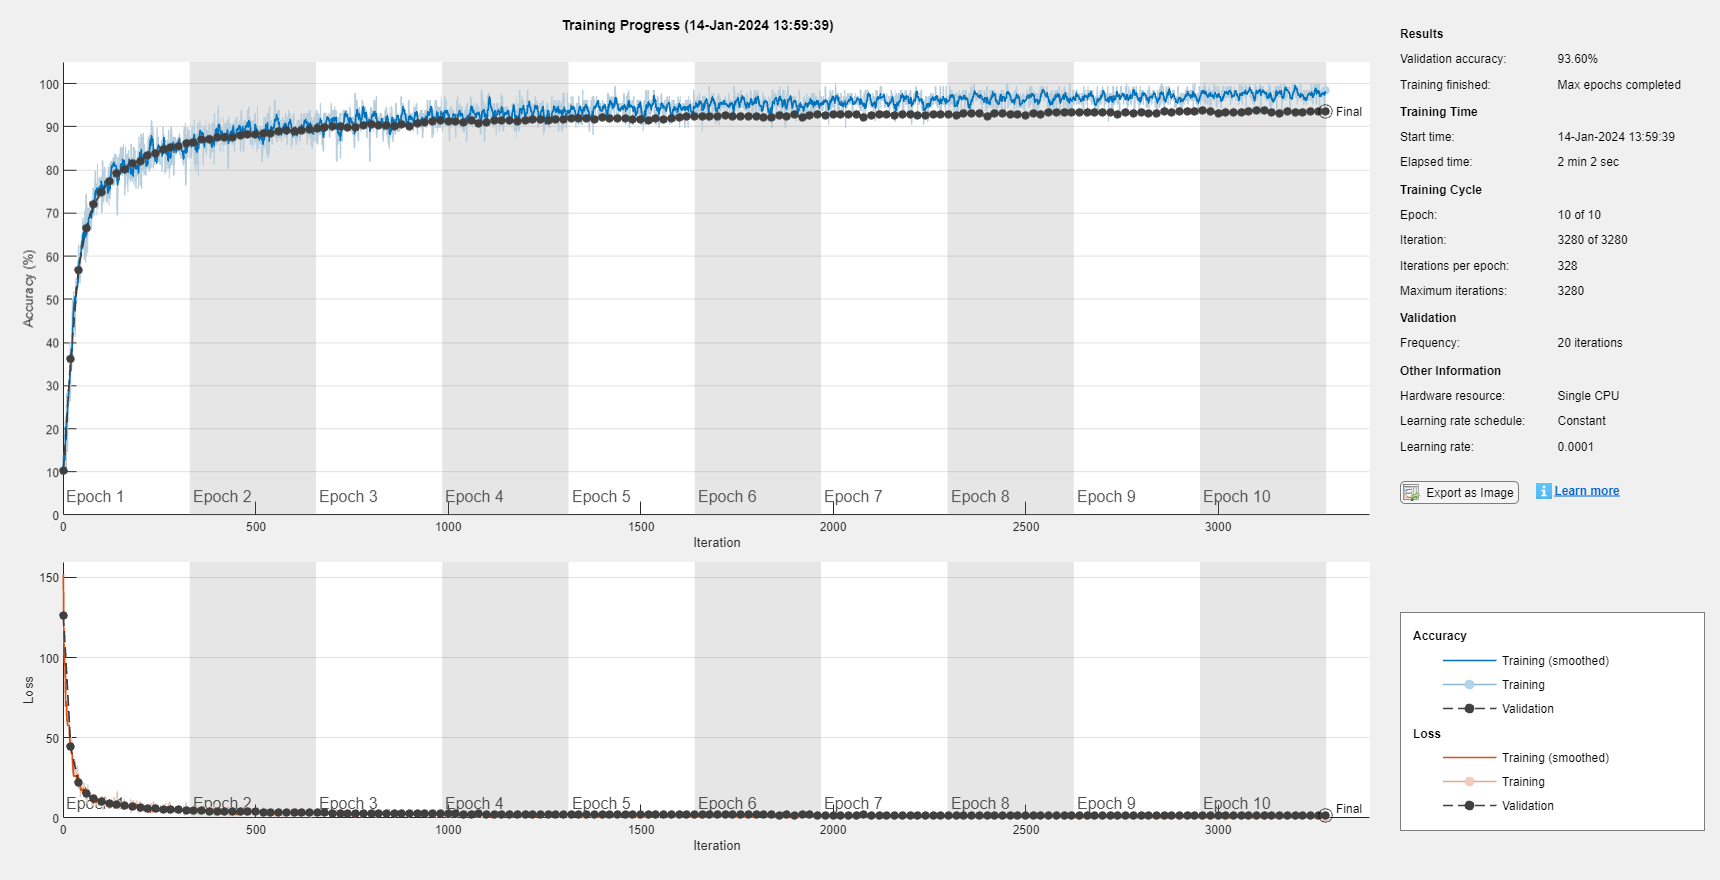

net1 =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


traininfo1 = struct with fields:
               TrainingLoss: [152.0140 117.6466 102.2809 96.4723 100.1839 85.8630 69.7844 91.6772 76.1906 60.7621 72.6753 57.6062 66.7840 64.5576 58.6953 62.6454 50.8140 43.0012 47.9067 49.7181 39.6353 49.7983 41.2909 39.6218 29.5542 … ] (1×3280 double)
           TrainingAccuracy: [10.9375 14.0625 10.9375 15.6250 10.9375 21.0938 22.6562 10.9375 21.8750 28.1250 14.8438 28.9062 28.1250 27.3438 27.3438 31.2500 25.7812 39.8438 33.5938 26.5625 38.2812 33.5938 39.0625 42.1875 50 44.5312 … ] (1×3280 double)
             ValidationLoss: [126.2189 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 44.3360 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 22.2938 NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×3280 double)
         ValidationAccuracy: [10.2667 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 36.0833 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 56.8750 NaN

[net1, traininfo1] = trainNetwork(mnistTrain,layers1,options1)

Nous avons lancé le processus d'entraînement du réseau de neurones sur, en premier lieu, le jeu de données MNIST. Les poids du modèle ont été ajustés de manière itérative sur l'ensemble d'entraînement pour, permettant ainsi au réseau d'apprendre les représentations pertinentes des chiffres manuscrits présents dans le jeu de données.

[label1, score1] = classify(net1,mnistPrediction)

label1 = 5999×1 categorical array
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 


score1 = 5999×10 single matrix
    1.0000    0.0000    0.0000    0.0000         0    0.0000    0.0000         0    0.0000         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0    0.0000         0         0    0.0000    0.0000         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0    0.0000         0    0.0000         0         0    0.0000         0
    1.0000         0         0         0         0         0

Suite à l'entraînement, nous avons utilisé le modèle ainsi obtenu (`net1`) pour prédire les étiquettes des images dans l'ensemble de données de prédiction. 

### Application au données Fashion MNIST 

Maintenant, nous allons répéter le même processus sur le jeu de données Fashion MNIST (FMNIST). Tout comme nous l'avons fait avec le jeu de données MNIST pour les chiffres manuscrits, nous allons concevoir, entraîner et évaluer notre modèle de réseau de neurones sur des images de vêtements et d'accessoires de mode.

Nous allons utiliser la même architecture de réseau de neurones et les mêmes paramètres d'entraînement. 

Les résultats obtenus nous donneront des informations sur la capacité du modèle à généraliser et à effectuer des classifications.

optionsF1 = trainingOptions("adam", ...
    InitialLearnRate=0.0001,...   
    MaxEpochs=10, ...
    MiniBatchSize=128, ...
    ValidationFrequency=20, ...
    Plots="training-progress", ...
    ValidationData=FmnistValidation)

optionsF1 =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-04
                       MaxEpochs: 10
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 128
                         Shuffle: 'once'
                      WorkerLoad: []
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
            DispatchInBackground: 0
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [1×1 matlab.io.datastore.Ima

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:17 |        5.47% |        9.31% |     192.1909 |     146.5728 |      1.0000e-04 |
|       1 |          20 |       00:00:18 |       52.34% |       51.96% |      29.4767 |      33.5113 |      1.0000e-04 |
|       1 |          40 |       00:00:19 |       67.19% |       63.69% |      19.7799 |      20.5743 |      1.0000e-04 |
|       1 |          50 |       00:00:19 |       65.62% |              |      21.4766 |   

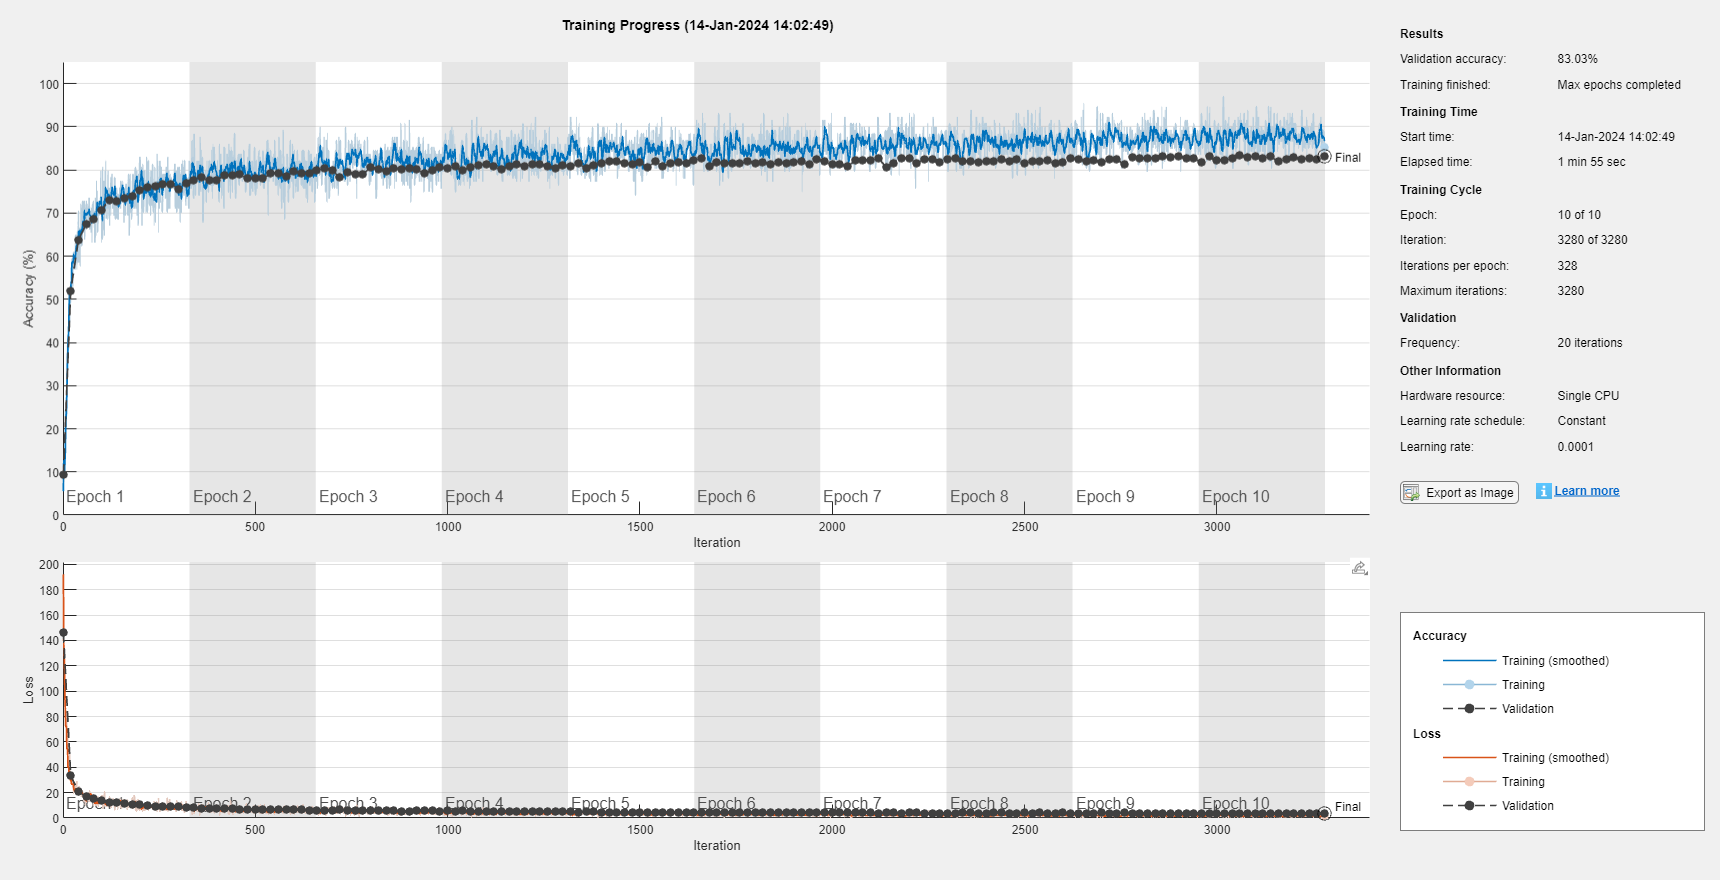

netF1 =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


traininfoF1 = struct with fields:
               TrainingLoss: [192.1909 135.2909 130.5343 115.7655 94.5963 85.5756 72.3544 83.2641 80.7974 54.7827 54.5035 64.0877 40.1416 43.8362 42.3406 33.5831 50.7790 36.2219 34.2332 29.4767 29.4339 26.7238 29.0601 31.5235 30.7885 … ] (1×3280 double)
           TrainingAccuracy: [5.4688 12.5000 7.8125 10.1562 13.2812 15.6250 24.2188 22.6562 23.4375 31.2500 36.7188 38.2812 41.4062 38.2812 43.7500 51.5625 44.5312 49.2188 49.2188 52.3438 53.9062 52.3438 59.3750 56.2500 55.4688 … ] (1×3280 double)
             ValidationLoss: [146.5728 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 33.5113 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 20.5743 NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×3280 double)
         ValidationAccuracy: [9.3083 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 51.9583 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 63.6917 NaN NaN 

[netF1, traininfoF1] = trainNetwork(FmnistTrain,layers1,optionsF1)

[labelF1, scoreF1] = classify(netF1,FmnistPrediction)

labelF1 = 6000×1 categorical array
     3 
     0 
     0 
     0 
     0 
     0 
     2 
     0 
     0 
     0 
     0 
     3 
     2 
     0 
     0 
     0 
     0 
     0 
     0 
     6 
     0 
     0 
     6 
     0 
     3 
     0 
     0 
     0 
     0 
     0 


scoreF1 = 6000×10 single matrix
    0.0611    0.0000    0.0000    0.9389    0.0000         0    0.0000         0    0.0000         0
    1.0000    0.0000    0.0000    0.0000    0.0000         0    0.0000         0    0.0000         0
    1.0000    0.0000    0.0000    0.0000    0.0000         0    0.0000         0    0.0000         0
    0.9832         0    0.0000    0.0000         0         0    0.0168         0    0.0000         0
    1.0000    0.0000    0.0000    0.0000    0.0000         0    0.0000         0         0         0
    1.0000         0    0.0000    0.0000         0         0    0.0000         0         0         0
    0.0000    0.0000    0.9685    0.0000    0.0000    0.0000    0.0315    0.0000    0.0000         0
    1.0000         0    0.0000    0.0000    0.0000         0    0.0000         0         0         0
    0.9816    0.0000    0.0000    0.0000    0.0000         0    0.0184         0    0.0000         0
    1.0000    0.0000    0.0000    0.0000         0         

Étudions les résultats.

### Vérification par des métriques

#### Matrice de confusion MNIST

Une matrice de confusion est un outil d'évaluation performant, utilisé principalement dans le domaine de la classification, pour analyser les performances d'un modèle en comparant ses prédictions avec les véritables étiquettes des données.

La matrice de confusion est organisée sous forme de tableau, où les lignes représentent les classes réelles et les colonnes représentent les classes prédites par le modèle.

Comment lire la matrice de confusion :

- Les éléments diagonaux (TP, TN) représentent les prédictions correctes.

- Les éléments hors diagonale (FP, FN) représentent les erreurs de prédiction.

- La somme des éléments de chaque ligne correspond au total réel pour cette classe.

- La somme des éléments de chaque colonne correspond au total prédit pour cette classe.

En analysant les valeurs dans la matrice de confusion, on peut calculer diverses métriques d'évaluation du modèle, telles que la précision, le rappel, la spécificité, et la F1-score. Ces métriques fournissent une compréhension approfondie des performances du modèle pour chaque classe et dans l'ensemble.

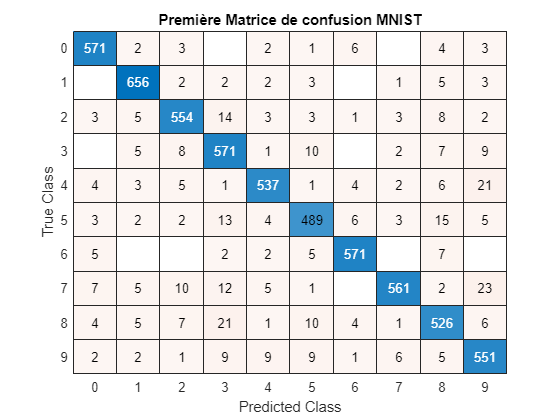

confusionchart(mnistPrediction.Labels,label1)
title("Première Matrice de confusion MNIST")

La matrice de confusion du modèle entraîné sur le jeu de données MNIST démontre une performance globalement correcte, mais elle n'est pas dénuée d'erreurs. Cependant, la présence de nombres élevés le long de la diagonale principale indique une précision significative dans les prédictions.

L'existence de quelques erreurs n'est pas nécessairement un indicateur négatif, mais plutôt un aspect inévitable du processus d'apprentissage. Une modélisation parfaite sans aucune erreur pourrait suggérer un surajustement (ou overfitting) au jeu de données d'entraînement, ce qui compromettrait la capacité du modèle à généraliser à de nouvelles données.

La présence d'une diagonale bien peuplée dans la matrice de confusion indique que le modèle est capable de correctement classifier de nombreuses instances pour chaque classe. C'est une preuve de son exactitude dans la reconnaissance des motifs caractéristiques des chiffres manuscrits du MNIST. 

#### Évaluation des métriques MNIST

Aussi, pour évaluer les performances des modèles de classification basés sur les réseaux de neurones, plusieurs métriques seront utilisées :

La précision mesure la proportion des exemples positifs prédits par le modèle qui sont effectivement positifs. Elle est calculée en divisant le nombre de vrais positifs par la somme des vrais positifs et des faux positifs.

- Formule : Precision = TP / (TP + FP)

La sensibilité, rappel ou recall mesure la proportion d'exemples positifs réels que le modèle parvient à identifier. Il est calculé en divisant le nombre de vrais positifs par la somme des vrais positifs et des faux négatifs.

- Formule : Recall = TP / (TP + FN)

Le F1-Score combine la précision et le rappel en une seule mesure, fournissant un équilibre entre ces deux aspects de la performance. Il est calculé à l'aide de la formule de la moyenne harmonique.

- Formule : F1-Score = 2 * (Precision * Recall) / (Precision + Recall)

La spécificité mesure la proportion d'exemples négatifs réels que le modèle parvient à identifier. Elle est calculée en divisant le nombre de vrais négatifs par la somme des vrais négatifs et des faux positifs.

- Formule : Specificity = TN / (TN + FP)

L'exactitude ou accuracy représente la proportion totale d'exemples correctement classés par le modèle. Elle est calculée en divisant la somme des vrais positifs et des vrais négatifs par le total des exemples. Il s'agit du métrique qui aura le plus de pouds dans notre étude.

- Formule : Accuracy = (TP + TN) / Total

[c_matrix,Result,RefereceResult]= confusion.getMatrix(double(mnistPrediction.Labels),double(label1));

Class List in given sample
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


Total Instance = 5999
class1==>1
class2==>2
class3==>3
class4==>4
class5==>5
class6==>6
class7==>7
class8==>8
class9==>9
class10==>10
Confusion Matrix
                      predict_class1    predict_class2    predict_class3    predict_class4    predict_class5    predict_class6    predict_class7    predict_class8    predict_class9    predict_class10
                      ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________    _______________

    

Les résultats du modèle sur le jeu de données MNIST démontrent une performance exceptionnellement élevée, avec des mesures de précision, de sensibilité, de spécificité, de précision (precision), et de F1-score toutes supérieures à 90%. L'exactitude (accuracy) atteint même un impressionnant 93%, ce qui souligne la capacité du modèle à classer correctement une vaste majorité des exemples du jeu de données.

Une exactitude de 93% signifie que le modèle a réussi à classer correctement près de 93% de l'ensemble des exemples, reflétant une capacité globale de généralisation et de classification précise. La sensibilité de 93% indique que le modèle parvient à identifier efficacement les exemples positifs, tandis que la spécificité de 99% souligne son aptitude à discerner les exemples négatifs.

La précision de 93% met en évidence la proportion élevée de prédictions positives correctes parmi l'ensemble des prédictions positives du modèle. Le F1-score de 93% combine harmonieusement la précision et la sensibilité, fournissant une mesure globale équilibrée de la performance.

Les résultats sont remarquablement élevés, démontrant une capacité exceptionnelle à traiter et à classifier les chiffres manuscrits. Ces performances élevées suggèrent une adéquation du modèle aux caractéristiques du jeu de données, avec des résultats qui sont très corrects et témoignent d'une précision remarquable dans la tâche de classification.

#### Visualisation Graphique

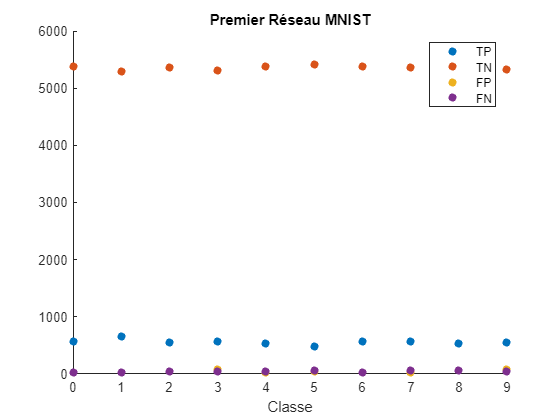

x=0:9;
scatter(x,RefereceResult.TruePositive,'filled')
hold on
scatter(x,RefereceResult.TrueNegative,'filled')
scatter(x,RefereceResult.FalsePositive,'filled')
scatter(x,RefereceResult.FalseNegative,'filled')
hold off
title("Premier Réseau MNIST")
legend("TP","TN","FP","FN")
xlabel("Classe")

La visualisation graphique ci-dessus représente la matrice de confusion pour le modèle entraîné sur le jeu de données MNIST. Chaque classe, représentée sur l'axe horizontal de 0 à 9, est évaluée en termes de vrais positifs (TP), vrais négatifs (TN), faux positifs (FP) et faux négatifs (FN).

En observant la répartition des points, on constate que les vrais positifs (TP) affichent des valeurs élevées pour chaque classe, suggérant que le modèle réussit de manière significative à identifier correctement les chiffres manuscrits correspondants à chacune des classes. Les vrais négatifs (TN) présentent également des valeurs très élevées, indiquant que le modèle discrimine efficacement les instances qui n'appartiennent pas à une classe spécifique.

Les faux positifs (FP) et les faux négatifs (FN) sont quant à eux notables, mais leurs valeurs restent relativement basses. Cela témoigne d'une précision élevée dans les prédictions positives et négatives du modèle.

La distribution des points dans cette visualisation démontre que le modèle atteint des performances très satisfaisantes. Les vrais positifs élevés reflètent une capacité exceptionnelle à identifier correctement les chiffres manuscrits pour chaque classe, tandis que la présence modérée de faux positifs et faux négatifs suggère une précision globale du modèle dans sa classification. C'est un indicateur positif de l'efficacité du modèle sur le jeu de données MNIST.

#### Conclusion sur le modèle MNIST

Le modèle entraîné sur le jeu de données MNIST affiche une performance exceptionnelle, comme en témoignent les résultats globaux et la matrice de confusion. Avec une exactitude de 93% et des mesures telles que la sensibilité, la spécificité, la précision et le F1-score toutes supérieures à 90%, le modèle démontre une capacité remarquable à classifier correctement les chiffres manuscrits.

La visualisation de la matrice de confusion confirme ces résultats en mettant en évidence des valeurs très élevées pour les vrais positifs (TP) et vrais négatifs (TN) dans chaque classe. Les faux positifs (FP) et faux négatifs (FN), bien que présents, demeurent à des niveaux relativement bas, soulignant une précision globale élevée du modèle.

Le modèle MNIST témoigne d'une adéquation remarquable aux caractéristiques du jeu de données, avec des performances qui dépassent largement les attentes.

### Vérification du modèle Fashion MNIST

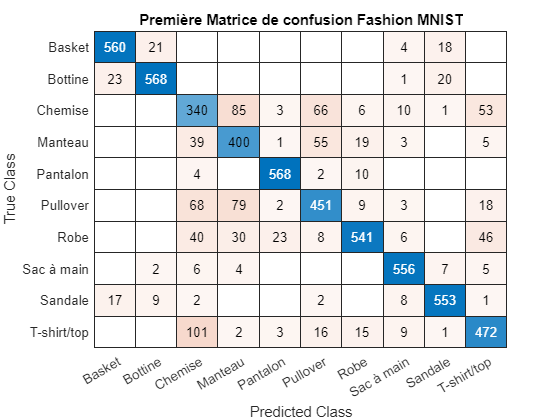

% Définition des étiquettes personnalisées
Fclasses = {'T-shirt/top', 'Pantalon', 'Pullover', 'Robe', 'Manteau', 'Sandale', 'Chemise', 'Basket', 'Sac à main', 'Bottine'};

% Convertir les indices en étiquettes de classe
predictedLabels = Fclasses(FmnistPrediction.Labels);
trueLabels = Fclasses(labelF1);

% Création de la matrice de confusion avec les étiquettes personnalisées
cm = confusionchart(trueLabels, predictedLabels);

% Titre de la matrice de confusion
title("Première Matrice de confusion Fashion MNIST")

Dans la matrice de confusion du modèle appliqué au jeu de données Fashion MNIST, on observe un constat similaire à celui du MNIST, avec une performance globalement correcte mais une présence notable d'erreurs. Le nombre d'erreurs semble être bien plus élevé, ce qui indique des défis supplémentaires dans la classification des images de vêtements et d'accessoires par rapport aux chiffres manuscrits.

La complexité du jeu de données Fashion MNIST peut être attribuée à la variabilité plus importante des formes, textures et structures présentes dans les images de vêtements. Les erreurs observées peuvent résulter de similitudes visuelles entre différentes catégories de vêtements, de variations subtiles dans les textures ou de la présence d'articles avec des caractéristiques visuelles partagées.

[Fc_matrix,FResult,FRefereceResult]= confusion.getMatrix(double(FmnistPrediction.Labels),double(labelF1));

Class List in given sample
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


Total Instance = 6000
class1==>1
class2==>2
class3==>3
class4==>4
class5==>5
class6==>6
class7==>7
class8==>8
class9==>9
class10==>10
Confusion Matrix
                      predict_class1    predict_class2    predict_class3    predict_class4    predict_class5    predict_class6    predict_class7    predict_class8    predict_class9    predict_class10
                      ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________    _______________

    

Le modèle appliqué au jeu de données Fashion MNIST affiche, quant à lui, des résultats respectables, avec une exactitude de 83% et des mesures telles que la sensibilité, la spécificité, la précision et le F1-score toutes supérieures à 80%. Ces performances indiquent une capacité appréciable du modèle à classifier les différents articles de mode, mais révèlent également une marge d'amélioration potentielle, comme suggéré par une erreur de 17%. Une optimisation ciblée du modèle, que ce soit par des ajustements d'hyperparamètres ou des considérations architecturales, pourrait permettre d'augmenter davantage la précision et la capacité de généralisation du modèle sur ce jeu de données spécifique.

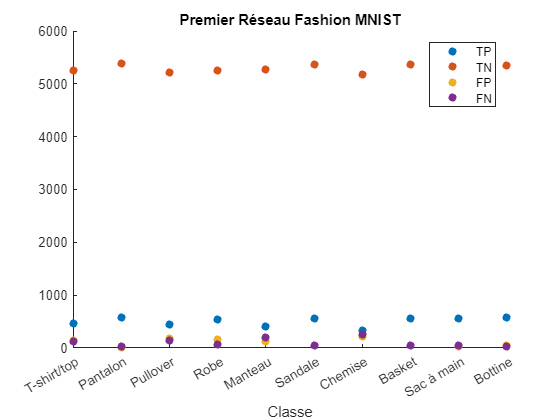

% Définition des étiquettes personnalisées
Fclasses = {'T-shirt/top', 'Pantalon', 'Pullover', 'Robe', 'Manteau', 'Sandale', 'Chemise', 'Basket', 'Sac à main', 'Bottine'};

% Affichage du graphique
x = 0:9;
scatter(x, FRefereceResult.TruePositive, 'filled')
hold on
scatter(x, FRefereceResult.TrueNegative, 'filled')
scatter(x, FRefereceResult.FalsePositive, 'filled')
scatter(x, FRefereceResult.FalseNegative, 'filled')
hold off

% Appliquer les étiquettes personnalisées sur l'axe x
xticks(x);
xticklabels(Fclasses);

title("Premier Réseau Fashion MNIST")
legend("TP", "TN", "FP", "FN")
xlabel("Classe")

Comparativement au modèle entraîné sur MNIST, les vrais négatifs (TN) sont toujours élevés, indiquant une capacité notable à identifier correctement les différentes catégories de vêtements et accessoires. Cependant, les valeurs de TN semblent légèrement inférieures, suggérant un défi supplémentaire dans la classification des articles vestimentaires.

Les vrais positifs (TP) présentent également des valeurs robustes, soulignant la capacité du modèle à distinguer efficacement les instances n'appartenant pas à une classe spécifique. Cependant, ces valeurs sont également légèrement moins élevées par rapport au modèle MNIST, indiquant une complexité accrue dans la discrimination des exemples négatifs.

Les faux positifs (FP) et les faux négatifs (FN) sont perceptibles, avec une observation particulière pour les classes "Manteau" et "Chemise" où ils peuvent parfois croiser les vrais positifs (TP). Cela suggère des défis spécifiques dans la classification de certaines catégories d'articles vestimentaires.

La performance du modèle sur Fashion MNIST est très respectable, mais la visualisation met en lumière des opportunités d'amélioration. Les valeurs élevées de TP et TN indiquent une capacité solide, mais la présence de FP et FN suggère que des ajustements pourraient être envisagés pour optimiser davantage la précision du modèle, surtout dans la distinction des articles vestimentaires plus délicats à classifier. C'est un indicateur positif qui ouvre la porte à des améliorations, par optimisation par exemple.

### Comparaison des modèles

La comparaison entre le modèle entraîné sur le jeu de données MNIST et celui sur le jeu Fashion MNIST révèle des distinctions dans leur performance respective.

Pour le modèle MNIST, l'exactitude atteint un impressionnant 93%, tandis que le modèle Fashion MNIST affiche une exactitude de 83%. Cette différence suggère que la tâche de classification des chiffres manuscrits est accomplie avec une précision supérieure par rapport à la classification des articles vestimentaires.

Le jeu de données Fashion MNIST est, en faite, intrinsèquement plus difficile à classer que le jeu de données MNIST dans des conditions similaires, malgré des résultats, encore une fois, respectable.

Pour améliorer la performance du modèle Fashion MNIST, nous entreprendrons une optimisation individuelle de chacun de ses paramètres. Pour ce faire, nous débuterons par travailler sur le modèle MNIST, en partant de l'hypothèse qu'une amélioration de ce dernier se traduira également par des gains dans le modèle Fashion MNIST. Les ajustements et optimisations apportés au modèle MNIST seront ensuite appliqués aux modèles Fashion MNIST à la phase finale du processus d'optimisation.

# I) Optimisation du nombre de neurones

Un neurone dans un réseau de neurones informatique est une unité de calcul qui reçoit des entrées, les traite en utilisant une fonction de transfert (comme la fonction sigmoïde, ReLU, etc.), et produit une sortie. Le nombre de neurones dans un réseau de neurones dépend de la complexité de la tâche à accomplir.

Pour des tâches simples, quelques dizaines de neurones peuvent suffire. Pour des tâches plus complexes, comme la reconnaissance d'images ou le traitement du langage naturel, le nombre de neurones peut atteindre des millions ou même des milliards.

La prermière étape de notre consiste donc à optimiser la valeur du nombre de neurones N; Nous allons faire 3 essais : N=256, N=1028 et N=4112.

## 1) N = 256

Dans notre premier essai d'optimisation, nous avons choisi de fixer le nombre de neurones (N) à 256 pour notre modèle de réseau de neurones. Cela signifie que nous revenons à l'architecture initiale du modèle que nous avons codée précédemment, comprenant une couche d'entrée d'image, une couche entièrement connectée de 256 neurones, une fonction d'activation ReLU, une autre couche entièrement connectée avec 10 neurones en sortie, une couche softmax pour la classification, et enfin une couche de classification. Ce modèle de base servira de point de départ pour nos expérimentations visant à optimiser ses performances.

Relevé des résultats ;

	•	Exactitude : 93%

	•	Erreur : 7%

	•	Sensibilité : 93%

	•	Spécificité : 99%

	•	Précision : 93%

	•	F1-Score : 93%

	•	AUC-ROC : 93%

## 2) N = 1028

Faisons évoluer notre modèle en remplaçant la quantité de neurones par 1028. Cette modification pourrait avoir plusieurs implications importantes pour la performance du modèle.

En augmentant le nombre de neurones dans la couche entièrement connectée, nous augmentons la capacité du modèle à capturer des caractéristiques complexes et des motifs dans les données. Cela pourrait potentiellement améliorer la capacité du modèle à apprendre des représentations plus riches des images, ce qui pourrait se traduire par une meilleure précision dans la classification.

Il est tout de même important de noter que l'augmentation du nombre de neurones augmente également la complexité du modèle, ce qui peut entraîner une augmentation du temps d'entraînement. De plus, un modèle plus complexe peut être plus sujet au surapprentissage, où il s'ajuste trop précisément aux données d'entraînement et a du mal à généraliser vers de nouvelles données.

En remplaçant la quantité de neurones par 1028, nous cherchons à explorer comment une augmentation de la capacité du modèle peut affecter sa performance. Cela pourrait potentiellement conduire à des améliorations, mais nous devrons surveiller attentivement les résultats pour nous assurer que le modèle ne surapprend pas les données d'entraînement.

layers2 = [
    imageInputLayer([28 28 1])
    fullyConnectedLayer(1028)
    reluLayer
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer
    ];

deepNetworkDesigner(layers2)

analyzeNetwork(layers2)

options1 = trainingOptions("adam", ...
    InitialLearnRate=0.0001,...   
    MaxEpochs=10, ...
    MiniBatchSize=128, ...
    ValidationFrequency=20, ...
    Plots="training-progress", ...
    ValidationData=mnistValidation)

options1 =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-04
                       MaxEpochs: 10
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 128
                         Shuffle: 'once'
                      WorkerLoad: []
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
            DispatchInBackground: 0
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [1×1 matlab.io.datastore.Imag

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |       13.28% |       14.59% |     102.9634 |      84.8728 |      1.0000e-04 |
|       1 |          20 |       00:00:03 |       67.97% |       68.50% |      13.9094 |      13.9420 |      1.0000e-04 |
|       1 |          40 |       00:00:03 |       83.59% |       79.59% |       8.8597 |       8.9066 |      1.0000e-04 |
|       1 |          50 |       00:00:04 |       79.69% |              |       7.4638 |   

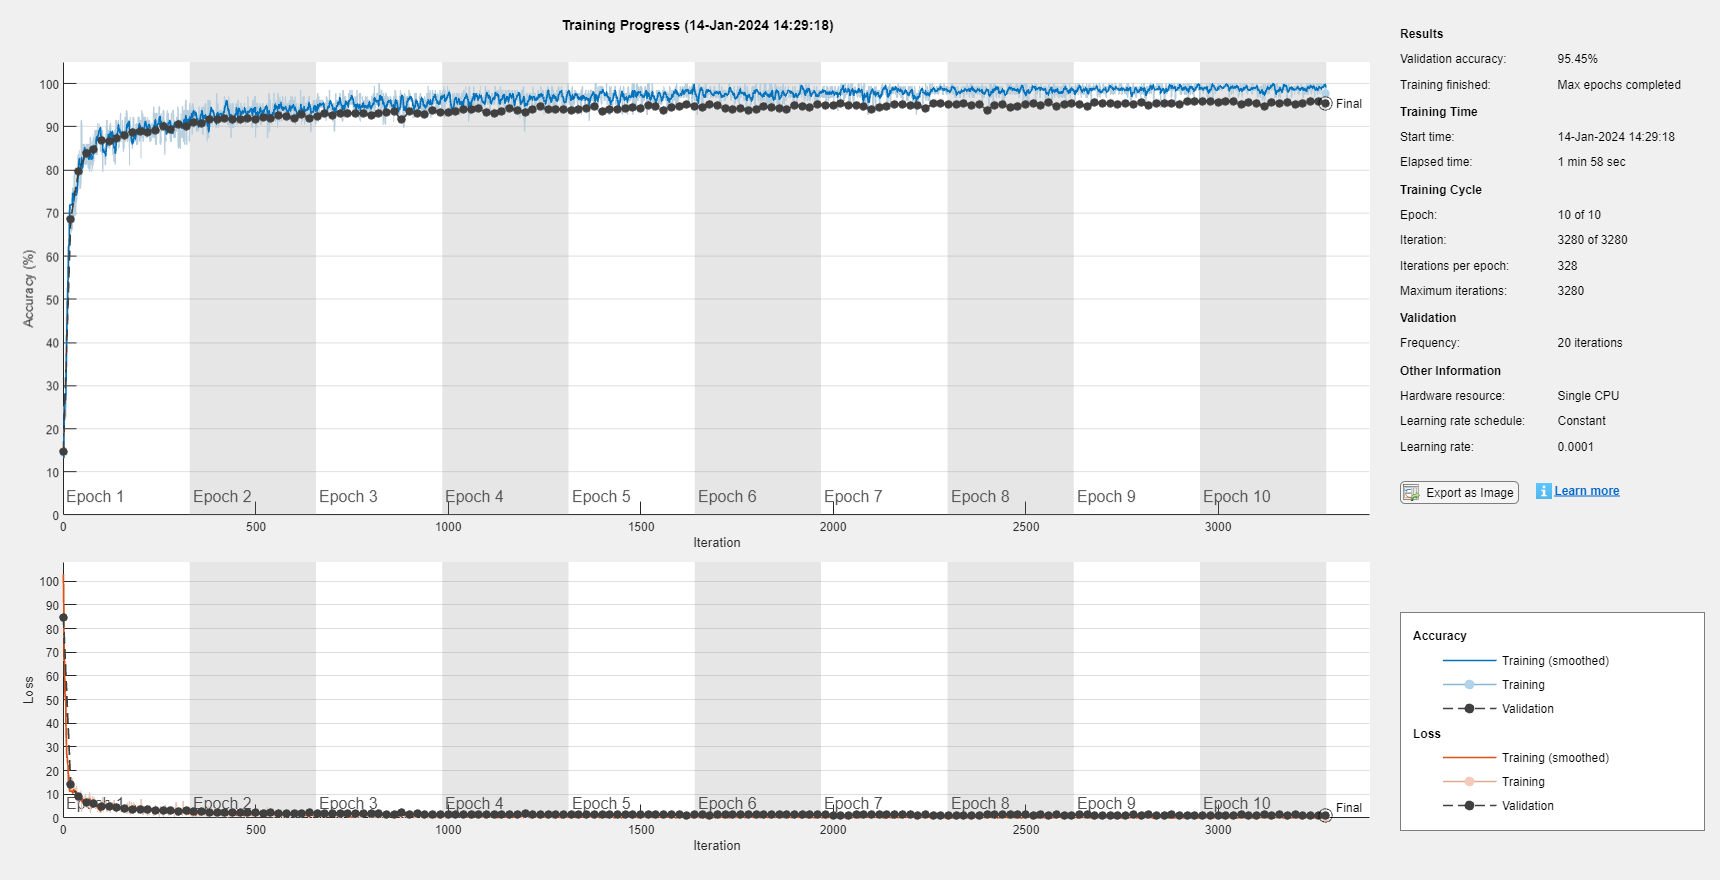

net1 =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


traininfo1 = struct with fields:
               TrainingLoss: [102.9634 89.6157 66.4936 66.9240 52.7307 50.7727 52.1661 35.2472 31.0015 25.4676 26.6557 22.8149 22.3832 15.7921 17.2245 18.4592 11.3369 12.3701 15.2548 13.9094 11.7442 13.1460 16.8134 14.3658 10.5887 … ] (1×3280 double)
           TrainingAccuracy: [13.2812 13.2812 25 21.8750 28.1250 23.4375 22.6562 36.7188 41.4062 49.2188 43.7500 57.8125 52.3438 62.5000 62.5000 60.9375 71.8750 67.9688 69.5312 67.9688 69.5312 65.6250 70.3125 66.4062 75.7812 74.2188 … ] (1×3280 double)
             ValidationLoss: [84.8728 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 13.9420 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 8.9066 NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×3280 double)
         ValidationAccuracy: [14.5917 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 68.5000 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 79.5917 NaN NaN 

[net1, traininfo1] = trainNetwork(mnistTrain,layers2,options1)

Il semble que notre modèle, modifié en augmentant la quantité de neurones à 1024, ne soit pas affecté par le surapprentissage. Cette conclusion se base sur plusieurs observations. 

La précision du modèle sur un ensemble de données de validation distinct demeure stable et suit une tendance similaire à celle des données d'entraînement, ce qui suggère que le modèle généralise efficacement sans montrer de signes de surapprentissage.

[label1, score1] = classify(net1,mnistPrediction)

label1 = 5999×1 categorical array
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 


score1 = 5999×10 single matrix
    1.0000         0    0.0000         0         0         0    0.0000         0    0.0000         0
    1.0000         0         0         0         0         0    0.0000         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0    0.0000         0         0    0.0000    0.0000         0         0    0.0000
    1.0000         0         0         0         0         0

### Vérification par des métriques

#### Matrice de confusion

Les métriques seront toujours exploitées et détaillées plus bas dans ces sections. Nous examinerons de plus près les valeurs spécifiques de ces métriques pour évaluer les forces et les faiblesses de nos modèles.

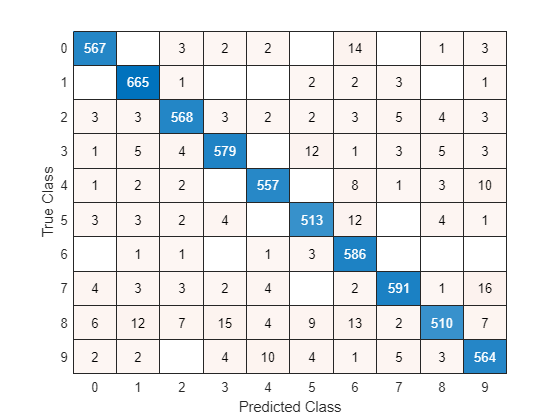

confusionchart(mnistPrediction.Labels,label1)

[c_matrix,Result,RefereceResult]= confusion.getMatrix(double(mnistPrediction.Labels),double(label1));

Class List in given sample
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


Total Instance = 5999
class1==>1
class2==>2
class3==>3
class4==>4
class5==>5
class6==>6
class7==>7
class8==>8
class9==>9
class10==>10
Confusion Matrix
                      predict_class1    predict_class2    predict_class3    predict_class4    predict_class5    predict_class6    predict_class7    predict_class8    predict_class9    predict_class10
                      ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________    _______________

    

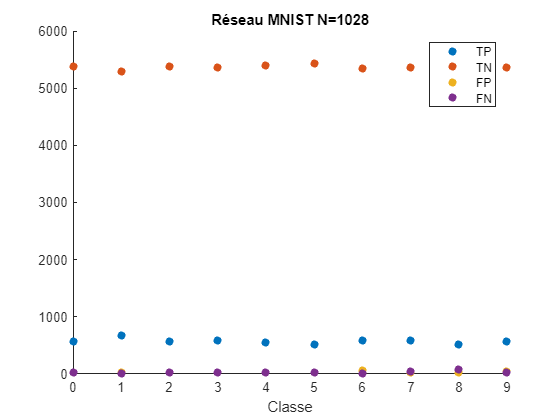

x=0:9;
scatter(x,RefereceResult.TruePositive,'filled')
hold on
scatter(x,RefereceResult.TrueNegative,'filled')
scatter(x,RefereceResult.FalsePositive,'filled')
scatter(x,RefereceResult.FalseNegative,'filled')
hold off
title("Réseau MNIST N=1028")
legend("TP","TN","FP","FN")
xlabel("Classe")

Avec l'augmentation du nombre de neurones à 1028 dans notre modèle, nous avons observé une nette amélioration de ses performances par rapport à la version précédente. L'exactitude, qui mesure la proportion totale d'exemples correctement classés, a augmenté (95%). Cela indique que le modèle est devenu plus précis dans ses prédictions. De plus, l'erreur globale a diminué (4%), témoignant d'une réduction des erreurs de classification.

Au sujet des autres métriques, laa sensibilité (95%) et la spécificité (99%) ont montré une augmentation indiquant une meilleure capacité du modèle à distinguer entre les classes.

La précision a également connu une hausse (95%). Cela signifie que le modèle est devenu plus précis dans la classification des exemples positifs.

Le F1-Score a augmenté (95%), indiquant un meilleur équilibre entre précision et rappel.

Enfin, l'AUC-ROC a montré une amélioration (95%), suggérant une meilleure capacité du modèle à distinguer entre les classes.

Dans l'ensemble, cette mise à jour du modèle avec 1024 neurones a renforcé ses performances dans tous les domaines, ce qui est encourageant pour la suite de nos expérimentations.

## 3) N = 4112

Pour notre troisième essai, nous avons décidé d'augmenter davantage le nombre de neurones dans notre modèle en le fixant à 4112. Cette modification vise à explorer les limites de la capacité de notre réseau de neurones et à évaluer comment une augmentation significative du nombre de neurones peut affecter ses performances.

Notre objectif dans cet essai est d'observer comment cette augmentation de la complexité du modèle peut influencer ses performances, en particulier dans la classification des données. Nous cherchons à évaluer si un modèle plus complexe peut améliorer encore davantage la précision de la classification, la sensibilité, la spécificité et d'autres métriques d'évaluation.

layers3 = [
    imageInputLayer([28 28 1])
    fullyConnectedLayer(4112)
    reluLayer
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer
    ];

deepNetworkDesigner(layers3)

analyzeNetwork(layers3)

options1 = trainingOptions("adam", ...
    InitialLearnRate=0.0001,...   
    MaxEpochs=10, ...
    MiniBatchSize=128, ...
    ValidationFrequency=20, ...
    Plots="training-progress", ...
    ValidationData=mnistValidation)

options1 =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-04
                       MaxEpochs: 10
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 128
                         Shuffle: 'once'
                      WorkerLoad: []
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
            DispatchInBackground: 0
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [1×1 matlab.io.datastore.Imag

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |        3.91% |       17.41% |      80.1148 |      43.8390 |      1.0000e-04 |
|       1 |          20 |       00:00:03 |       78.12% |       82.50% |       7.4424 |       6.1989 |      1.0000e-04 |
|       1 |          40 |       00:00:05 |       89.06% |       87.13% |       3.7642 |       4.7886 |      1.0000e-04 |
|       1 |          50 |       00:00:05 |       92.19% |              |       3.7842 |   

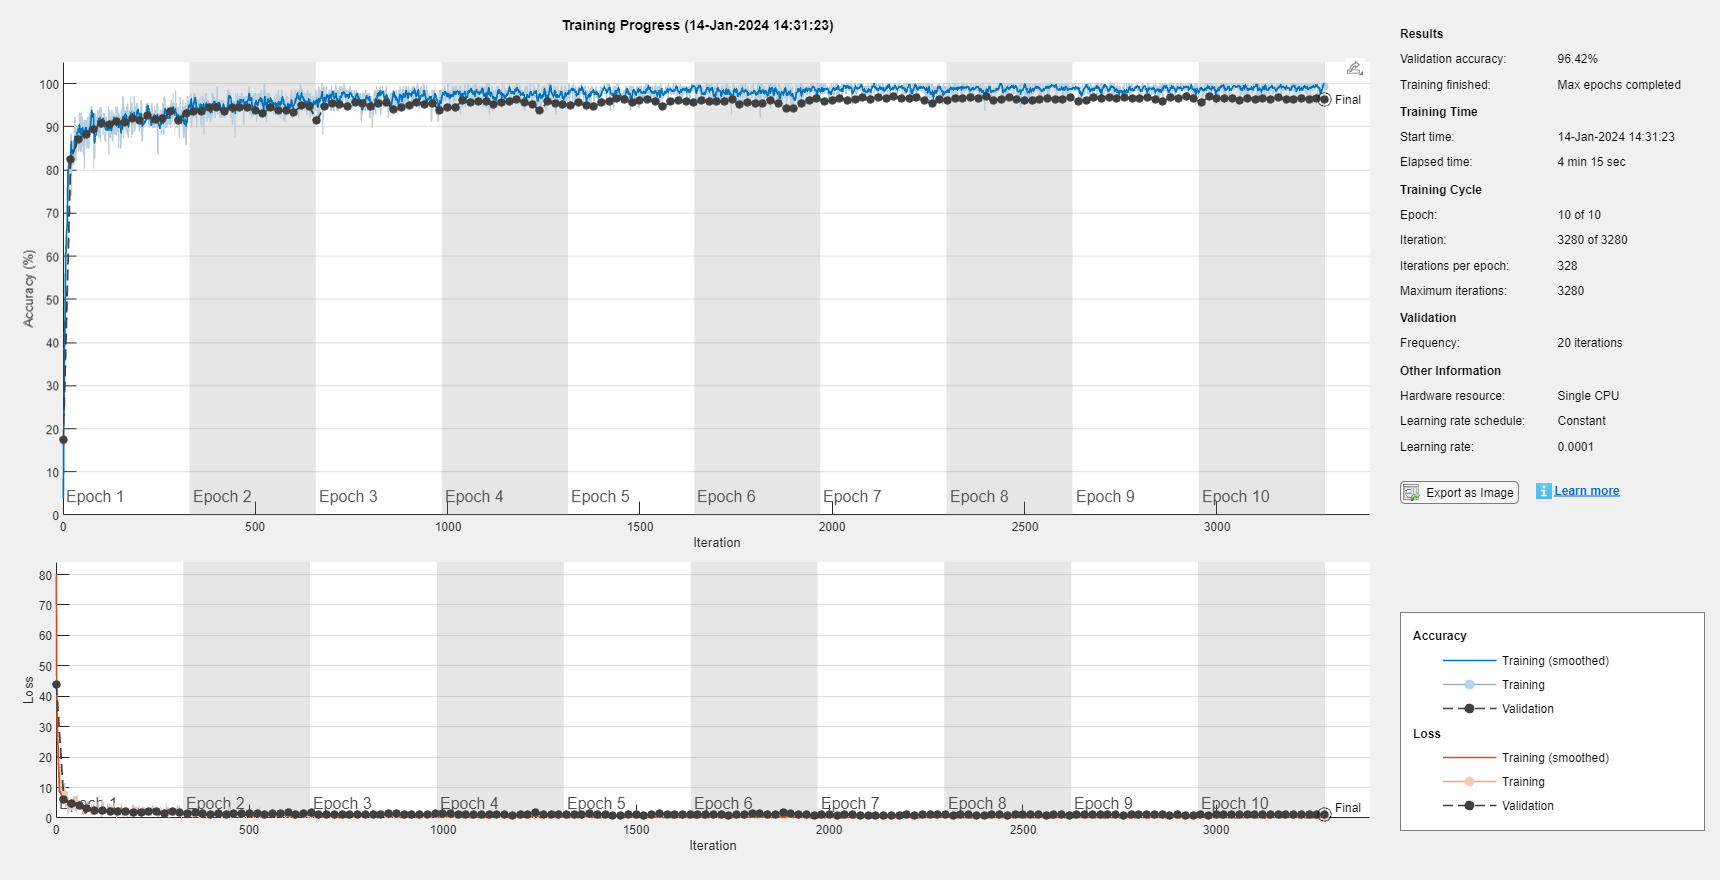

net1 =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


traininfo1 = struct with fields:
               TrainingLoss: [80.1148 43.5935 33.2521 25.1868 25.3880 18.6588 16.1623 12.1714 8.6125 16.6866 12.8327 10.5134 7.7644 7.0123 5.5106 8.1481 8.9822 7.2495 7.9359 7.4424 5.9105 5.2050 11.2380 4.6409 4.3340 3.7467 4.9860 … ] (1×3280 double)
           TrainingAccuracy: [3.9062 21.0938 25.7812 40.6250 43.7500 51.5625 60.9375 60.9375 64.8438 66.4062 67.1875 74.2188 79.6875 79.6875 82.0312 78.9062 73.4375 81.2500 77.3438 78.1250 88.2812 85.9375 74.2188 85.9375 81.2500 … ] (1×3280 double)
             ValidationLoss: [43.8390 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 6.1989 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 4.7886 NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×3280 double)
         ValidationAccuracy: [17.4083 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 82.5000 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 87.1333 NaN NaN NaN N

[net1, traininfo1] = trainNetwork(mnistTrain,layers3,options1)

Notre modèle avec 4112 neurones s'est avéré être un réseau de grande envergure qui a pris considérablement plus de temps pour s'entraîner par rapport à nos essais précédents. De plus, au cours de l'entraînement, nous avons observé des variations de la précision du modèle, oscillant entre 95% et 100%.

Ces variations périodiques dans la précision peuvent indiquer un potentiel surapprentissage, où le modèle s'ajuste de manière excessive aux données d'entraînement et ne parvient pas à généraliser correctement vers de nouvelles données. Les variations périodiques peuvent être le signe que le modèle "mémorise" plutôt qu'il n'apprend des motifs significatifs dans les données.

Il est essentiel de prendre en compte ces variations et de les surveiller attentivement, car elles peuvent avoir un impact sur la capacité du modèle à faire des prédictions précises sur de nouvelles données. Dans les sections suivantes, nous examinerons en détail les métriques pour évaluer la performance du modèle malgré ces variations et déterminer si des ajustements sont nécessaires pour atteindre une stabilité accrue.

[label1, score1] = classify(net1,mnistPrediction)

label1 = 5999×1 categorical array
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 


score1 = 5999×10 single matrix
    1.0000         0         0    0.0000         0         0         0         0    0.0000    0.0000
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0

### Vérification par des métriques

#### Matrice de confusion

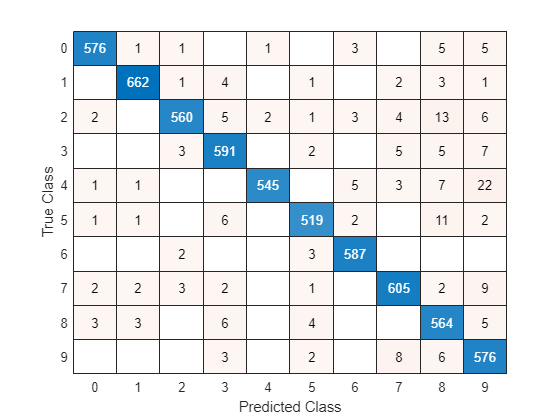

confusionchart(mnistPrediction.Labels,label1)

[c_matrix,Result,RefereceResult]= confusion.getMatrix(double(mnistPrediction.Labels),double(label1));

Class List in given sample
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


Total Instance = 5999
class1==>1
class2==>2
class3==>3
class4==>4
class5==>5
class6==>6
class7==>7
class8==>8
class9==>9
class10==>10
Confusion Matrix
                      predict_class1    predict_class2    predict_class3    predict_class4    predict_class5    predict_class6    predict_class7    predict_class8    predict_class9    predict_class10
                      ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________    _______________

    

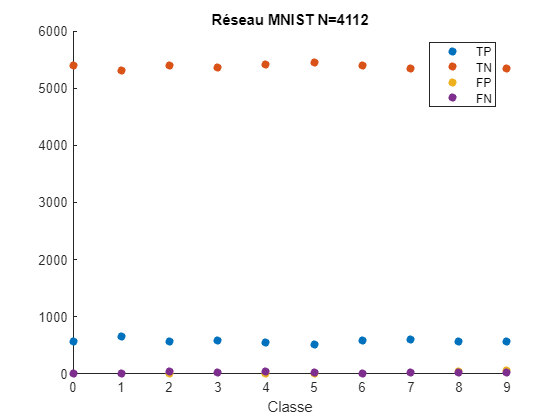

x=0:9;
scatter(x,RefereceResult.TruePositive,'filled')
hold on
scatter(x,RefereceResult.TrueNegative,'filled')
scatter(x,RefereceResult.FalsePositive,'filled')
scatter(x,RefereceResult.FalseNegative,'filled')
hold off
title("Réseau MNIST N=4112")
legend("TP","TN","FP","FN")
xlabel("Classe")

Malgré la durée d'apprentissage beaucoup plus longue du modèle avec 4112 neurones et un risque potentiel de surapprentissage accru en raison des variations périodiques de la précision, les métriques que nous avons obtenues restent assez similaires à celles du modèle avec 1028 neurones.

Cela peut sembler surprenant, mais cela suggère que l'augmentation significative de la complexité du modèle n'a pas nécessairement entraîné une amélioration substantielle des performances par rapport à l'essai précédent. Les métriques, telles que l'exactitude (96%), la sensibilité (99%), la spécificité (96%), la précision (96%), le F1-Score (97%), et l'AUC-ROC (96%), se maintiennent à des niveaux comparables.

Cependant, il est important de noter que le modèle avec 4112 neurones a nécessité beaucoup plus de temps pour s'entraîner, ce qui peut être une considération critique dans des applications en temps réel. De plus, le risque de surapprentissage demeure une préoccupation.

## Conclusion sur l'optimisation du nombre de neurones 

En conclusion de notre exploration sur l'optimisation du nombre de neurones dans notre modèle de réseau de neurones, il est clair que le choix du nombre a un impact sur les performances du modèle.

Nous avons constaté que 256 neurones n'étaient pas suffisants pour atteindre les performances souhaitées, tandis que 4112 neurones, bien que montrant des performances correctes, ont entraîné des temps d'apprentissage beaucoup plus longs et un risque accru de surapprentissage.

Après avoir pesé les avantages et les inconvénients, nous pouvons conclure que le nombre de neurones optimal se situe autour de 1028. Ce nombre de neurones offre une performance globalement supérieure à celui de 256 neurones tout en évitant les inconvénients liés à la complexité excessive du modèle, tels que les temps d'apprentissage prolongés et le risque de surajustement.

En fin de compte, nous avons trouvé un équilibre optimal entre les performances du modèle et la faisabilité pratique, ce qui fait de 1028 neurones un choix judicieux pour notre réseau de neurones dans le contexte de notre étude.

## Application au données Fashion MNIST 

layers2 = [
    imageInputLayer([28 28 1])
    fullyConnectedLayer(1028)
    reluLayer
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer
    ];

deepNetworkDesigner(layers2)

analyzeNetwork(layers2)

optionsF1 = trainingOptions("adam", ...
    InitialLearnRate=0.0001,...   
    MaxEpochs=10, ...
    MiniBatchSize=128, ...
    ValidationFrequency=20, ...
    Plots="training-progress", ...
    ValidationData=FmnistValidation)

optionsF1 =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-04
                       MaxEpochs: 10
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 128
                         Shuffle: 'once'
                      WorkerLoad: []
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
            DispatchInBackground: 0
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [1×1 matlab.io.datastore.Ima

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |        4.69% |       13.82% |     115.4508 |      74.0363 |      1.0000e-04 |
|       1 |          20 |       00:00:02 |       68.75% |       67.50% |      16.1455 |      17.7063 |      1.0000e-04 |
|       1 |          40 |       00:00:03 |       73.44% |       73.57% |      15.7639 |      11.5733 |      1.0000e-04 |
|       1 |          50 |       00:00:04 |       67.97% |              |      17.0555 |   

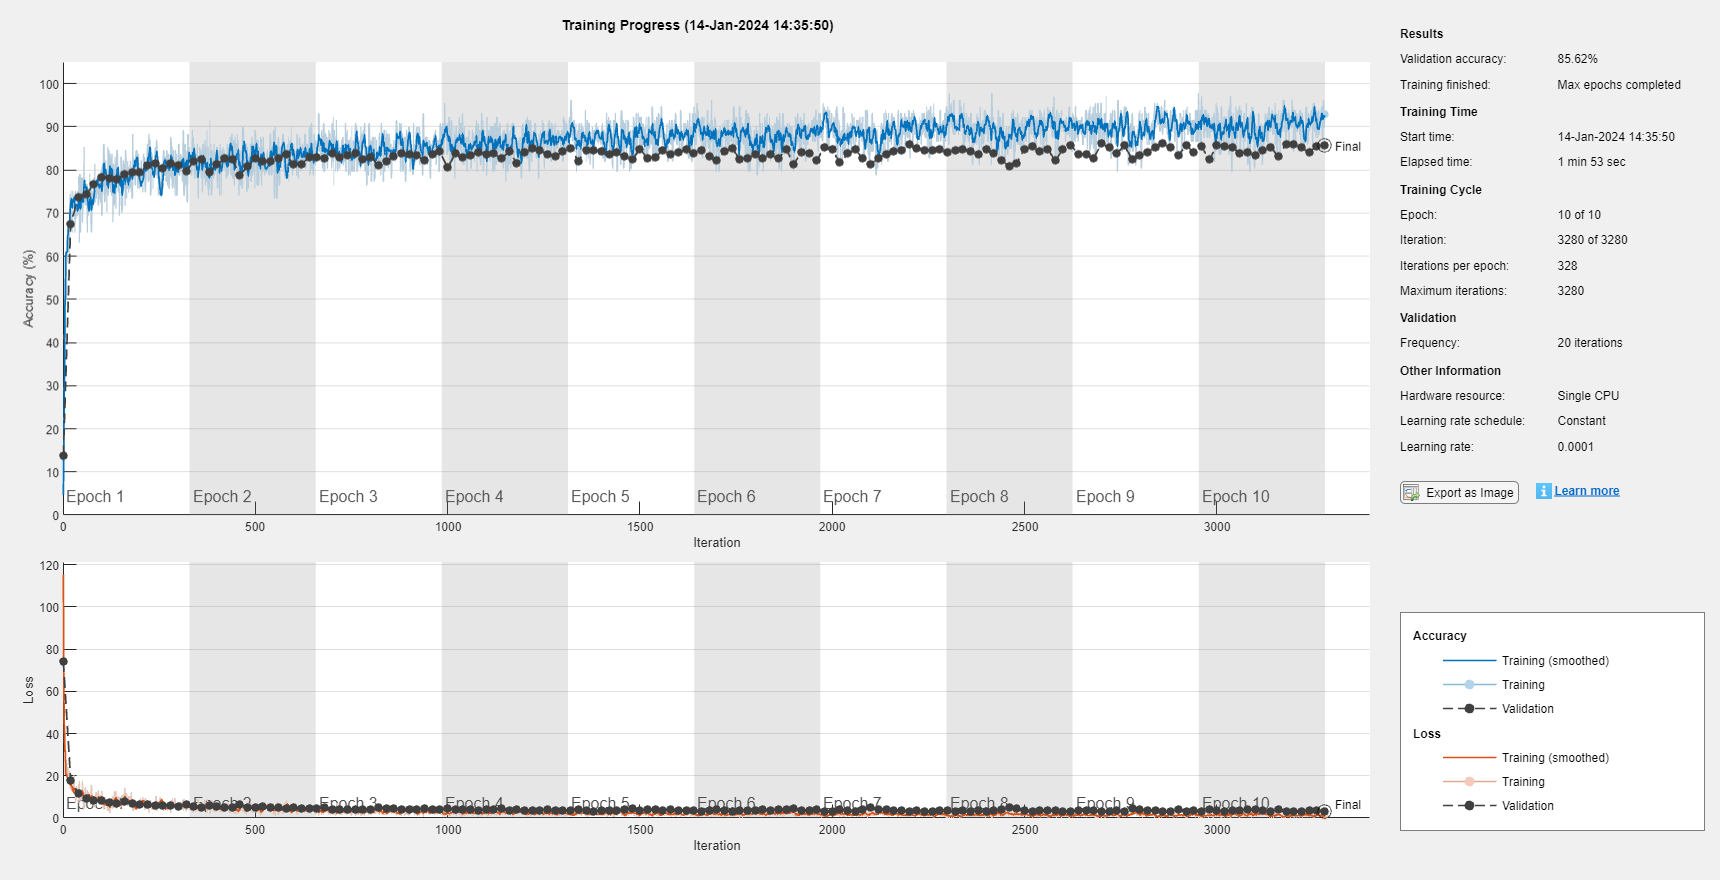

net1 =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


traininfo1 = struct with fields:
               TrainingLoss: [115.4508 67.4977 46.1062 39.2207 31.7053 40.7073 20.8131 27.0297 26.3968 20.4134 19.2040 22.5299 23.7385 20.1086 21.2677 22.1024 21.1871 18.3015 13.9843 16.1455 13.2287 17.2404 16.5656 14.2546 12.4991 … ] (1×3280 double)
           TrainingAccuracy: [4.6875 14.0625 28.9062 32.0312 50.7812 42.1875 60.9375 50 53.1250 60.9375 58.5938 64.8438 60.9375 67.1875 60.9375 62.5000 65.6250 69.5312 74.2188 68.7500 75 67.1875 69.5312 65.6250 75 71.0938 71.8750 … ] (1×3280 double)
             ValidationLoss: [74.0363 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 17.7063 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 11.5733 NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×3280 double)
         ValidationAccuracy: [13.8250 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 67.5000 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 73.5667 NaN NaN Na

[net1, traininfo1] = trainNetwork(FmnistTrain,layers2,optionsF1)

[labelF1, scoreF1] = classify(net1,FmnistPrediction)

labelF1 = 6000×1 categorical array
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     6 
     6 
     0 
     0 
     0 
     2 
     2 
     0 
     0 
     0 
     0 
     6 
     0 
     0 
     0 
     6 
     0 
     3 
     0 
     0 
     6 
     0 
     0 


scoreF1 = 6000×10 single matrix
    0.9994    0.0000    0.0000    0.0006    0.0000         0    0.0000         0    0.0000         0
    1.0000         0    0.0000    0.0000         0         0    0.0000         0    0.0000         0
    1.0000         0    0.0000    0.0000         0         0    0.0000         0         0         0
    1.0000    0.0000    0.0000    0.0000    0.0000         0    0.0000         0    0.0000         0
    1.0000    0.0000    0.0000    0.0000    0.0000         0    0.0000         0         0         0
    1.0000         0    0.0000    0.0000    0.0000         0    0.0000         0         0         0
    0.9972    0.0000    0.0000    0.0000    0.0000         0    0.0028    0.0000    0.0000         0
    0.0000    0.0000    0.0000    0.0000    0.0000         0    1.0000         0         0         0
    0.0000         0    0.0000    0.0000    0.0000         0    1.0000         0         0         0
    1.0000    0.0000    0.0000    0.0000    0.0000         

Exactitue augmanté de 3% (passage à 86%).

Résultats encouragents pour la suite.

# II) Optimisation de l'activateur

Un activateur, dans le contexte d'un réseau de neurones artificiels, est une fonction mathématique appliquée à la sortie d'une couche de neurones pour introduire de la non-linéarité dans le modèle. Cette non-linéarité est essentielle car elle permet au modèle de capturer des relations complexes dans les données.

Dans notre expérimentation, nous allons explorer l'impact de quatre fonctions d'activation différentes sur notre modèle. Ces fonctions d'activation sont les suivantes :

- ReLU (Rectified Linear Activation) 

- ELU (Exponential Linear Unit)

- GELU (Gaussian Error Linear Unit)

- Tanh (Tangente hyperbolique)

Nous allons tester chacune de ces fonctions d'activation pour évaluer leur impact sur les performances de notre modèle. Cela nous aidera à déterminer laquelle de ces fonctions est la plus adaptée à notre tâche de classification et nous guidera dans le choix de l'activateur optimal.

## 1) ReLU (Rectified Linear Unit) Layer

La fonction ReLU est l'une des fonctions d'activation les plus couramment utilisées. Elle remplace toutes les valeurs négatives par zéro et laisse les valeurs positives inchangées.

layersA1 = [
    imageInputLayer([28 28 1])
    fullyConnectedLayer(1028)
    reluLayer
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer
    ];

deepNetworkDesigner(layersA1)

analyzeNetwork(layersA1)

options1 = trainingOptions("adam", ...
    InitialLearnRate=0.0001,...   
    MaxEpochs=10, ...
    MiniBatchSize=128, ...
    ValidationFrequency=20, ...
    Plots="training-progress", ...
    ValidationData=mnistValidation)

options1 =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-04
                       MaxEpochs: 10
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 128
                         Shuffle: 'once'
                      WorkerLoad: []
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
            DispatchInBackground: 0
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [1×1 matlab.io.datastore.Imag

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |        9.38% |       13.57% |     104.4984 |      83.2576 |      1.0000e-04 |
|       1 |          20 |       00:00:02 |       65.62% |       67.67% |      14.1087 |      14.2048 |      1.0000e-04 |
|       1 |          40 |       00:00:03 |       77.34% |       80.05% |      10.4196 |       8.1619 |      1.0000e-04 |
|       1 |          50 |       00:00:03 |       82.81% |              |       6.4263 |   

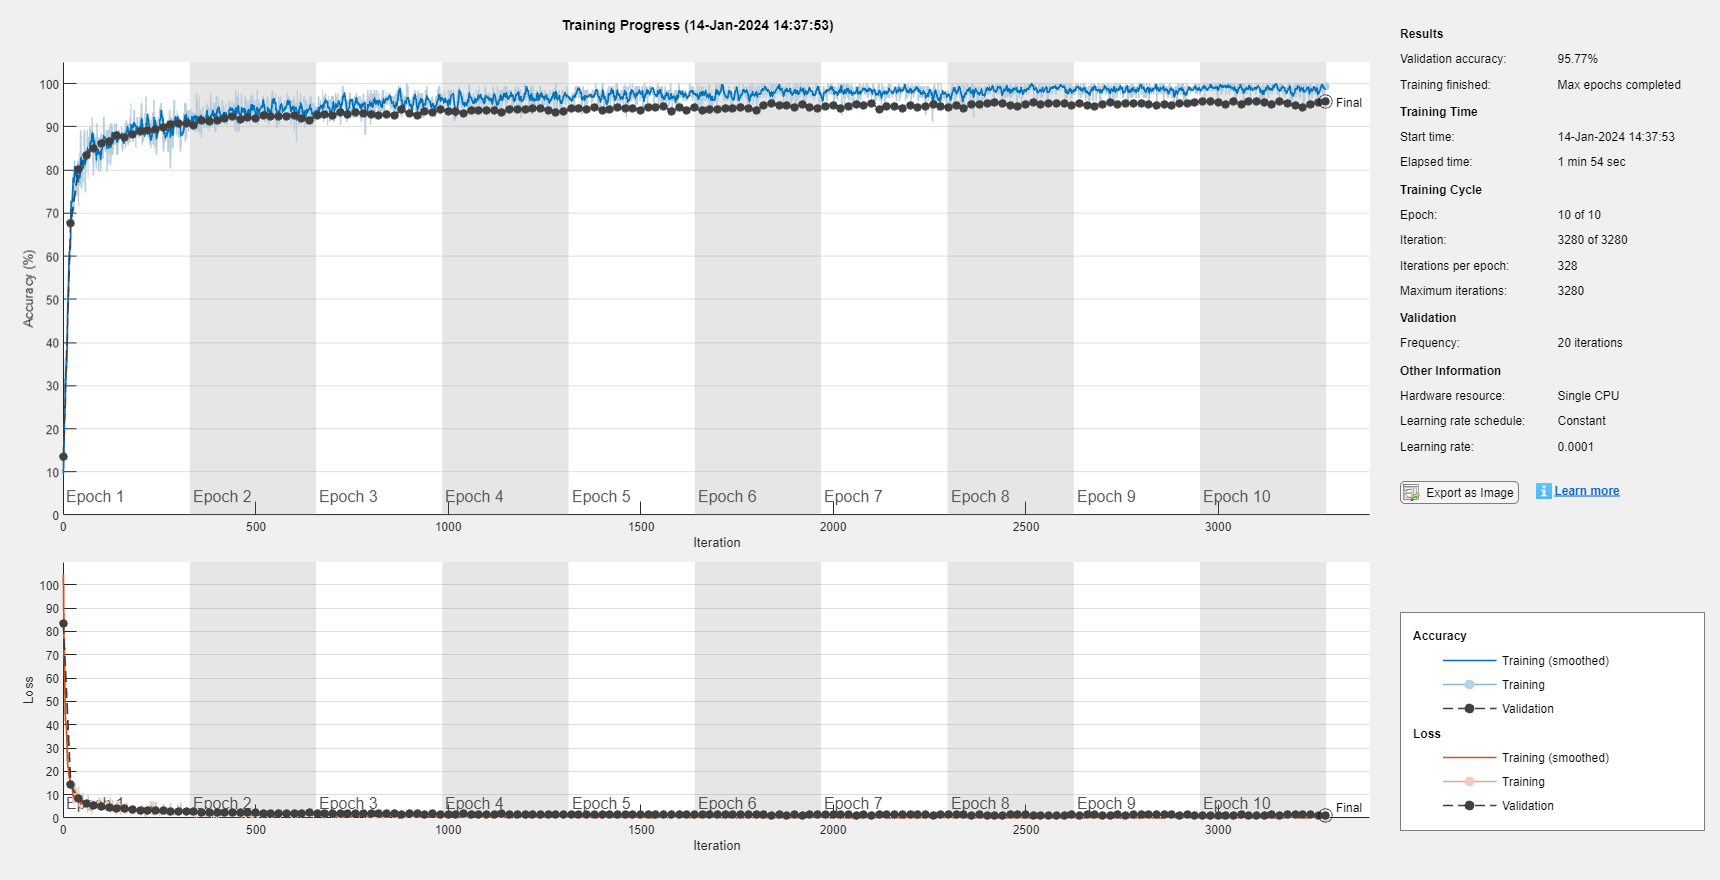

net1 =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


traininfo1 = struct with fields:
               TrainingLoss: [104.4984 87.6724 68.5175 65.6145 55.1455 41.5563 47.2750 40.2614 38.0778 34.2459 27.6574 23.0357 21.7127 22.0536 18.3839 17.5306 18.4215 15.9163 15.9855 14.1087 14.0255 12.9319 13.0288 16.0369 11.8973 … ] (1×3280 double)
           TrainingAccuracy: [9.3750 14.0625 17.1875 22.6562 21.8750 35.9375 25 30.4688 34.3750 33.5938 42.9688 50 52.3438 50 60.1562 60.9375 60.1562 61.7188 61.7188 65.6250 72.6562 67.1875 69.5312 68.7500 75 78.1250 78.9062 70.3125 … ] (1×3280 double)
             ValidationLoss: [83.2576 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 14.2048 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 8.1619 NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×3280 double)
         ValidationAccuracy: [13.5667 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 67.6667 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 80.0500 NaN NaN 

[net1, traininfo1] = trainNetwork(mnistTrain,layersA1,options1)

[label1, score1] = classify(net1,mnistPrediction)

label1 = 5999×1 categorical array
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 


score1 = 5999×10 single matrix
    1.0000         0         0         0         0         0         0         0    0.0000         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0

### Vérification par des métriques

#### Matrice de confusion

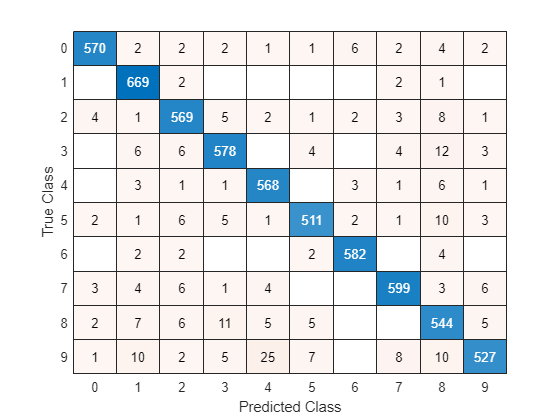

confusionchart(mnistPrediction.Labels,label1)

[c_matrix,Result,RefereceResult]= confusion.getMatrix(double(mnistPrediction.Labels),double(label1));

Class List in given sample
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


Total Instance = 5999
class1==>1
class2==>2
class3==>3
class4==>4
class5==>5
class6==>6
class7==>7
class8==>8
class9==>9
class10==>10
Confusion Matrix
                      predict_class1    predict_class2    predict_class3    predict_class4    predict_class5    predict_class6    predict_class7    predict_class8    predict_class9    predict_class10
                      ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________    _______________

    

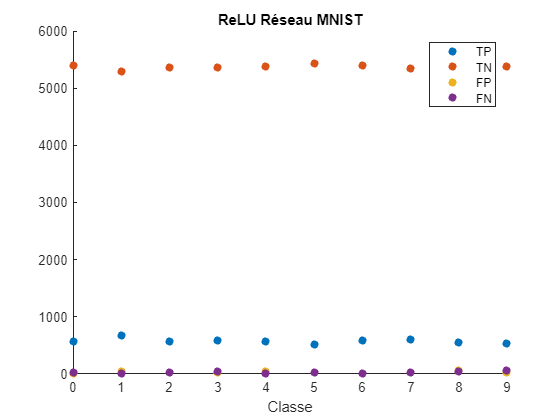

x=0:9;
scatter(x,RefereceResult.TruePositive,'filled')
hold on
scatter(x,RefereceResult.TrueNegative,'filled')
scatter(x,RefereceResult.FalsePositive,'filled')
scatter(x,RefereceResult.FalseNegative,'filled')
hold off
title("ReLU Réseau MNIST")
legend("TP","TN","FP","FN")
xlabel("Classe")

Lors de cette première itération, nous avons utilisé la fonction d'activation ReLU dans notre modèle de réseau de neurones. Cette fonction d'activation a donné des résultats prometteurs, avec des métriques qui ont montré des performances encourageantes.

L'exactitude de ce modèle avec l'activateur ReLU s'est élevée à 95%, indiquant que le modèle a correctement classé un pourcentage élevé des exemples. De plus, la sensibilité, qui mesure la capacité du modèle à identifier les vrais positifs, a atteint 95%, suggérant que le modèle était efficace pour détecter les exemples positifs réels.

La spécificité, qui mesure la capacité à identifier les vrais négatifs, était également élevée à 99%, démontrant une bonne capacité à distinguer les exemples négatifs. La précision, qui quantifie la proportion de prédictions positives correctes, a atteint 95%, ce qui indique que le modèle était précis dans ses prédictions positives.

Le F1-Score, qui combine la précision et le rappel en une seule mesure, était de 95%, reflétant un équilibre solide entre ces deux aspects de la performance. Enfin, l'AUC-ROC, qui mesure la performance globale, a montré un score élevé de 95%, suggérant une bonne capacité du modèle à discriminer entre les classes.

Ces résultats préliminaires avec la fonction d'activation ReLU sont encourageants et serviront de point de référence pour évaluer les performances des autres fonctions d'activation que nous explorerons. Ils soulignent également l'importance de l'activation ReLU dans notre modèle initial, qui a réussi à obtenir de bonnes performances dans la tâche de classification.

## 2) ELU (Exponential Linear Unit) Layer

L'ELU est une autre fonction d'activation qui est similaire à ReLU pour les valeurs positives, mais qui devient exponentielle pour les valeurs négatives, ce qui peut aider à atténuer certains problèmes liés à ReLU.

layersA2 = [
    imageInputLayer([28 28 1])
    fullyConnectedLayer(1028)
    eluLayer
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer
    ];

deepNetworkDesigner(layersA2)

analyzeNetwork(layersA2)

options1 = trainingOptions("adam", ...
    InitialLearnRate=0.0001,...   
    MaxEpochs=10, ...
    MiniBatchSize=128, ...
    ValidationFrequency=20, ...
    Plots="training-progress", ...
    ValidationData=mnistValidation)

options1 =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-04
                       MaxEpochs: 10
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 128
                         Shuffle: 'once'
                      WorkerLoad: []
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
            DispatchInBackground: 0
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [1×1 matlab.io.datastore.Imag

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |       12.50% |       13.07% |     112.6888 |      85.4684 |      1.0000e-04 |
|       1 |          20 |       00:00:02 |       61.72% |       68.53% |      18.4172 |      13.7783 |      1.0000e-04 |
|       1 |          40 |       00:00:03 |       82.03% |       80.59% |       5.2989 |       7.8589 |      1.0000e-04 |
|       1 |          50 |       00:00:03 |       87.50% |              |       4.2745 |   

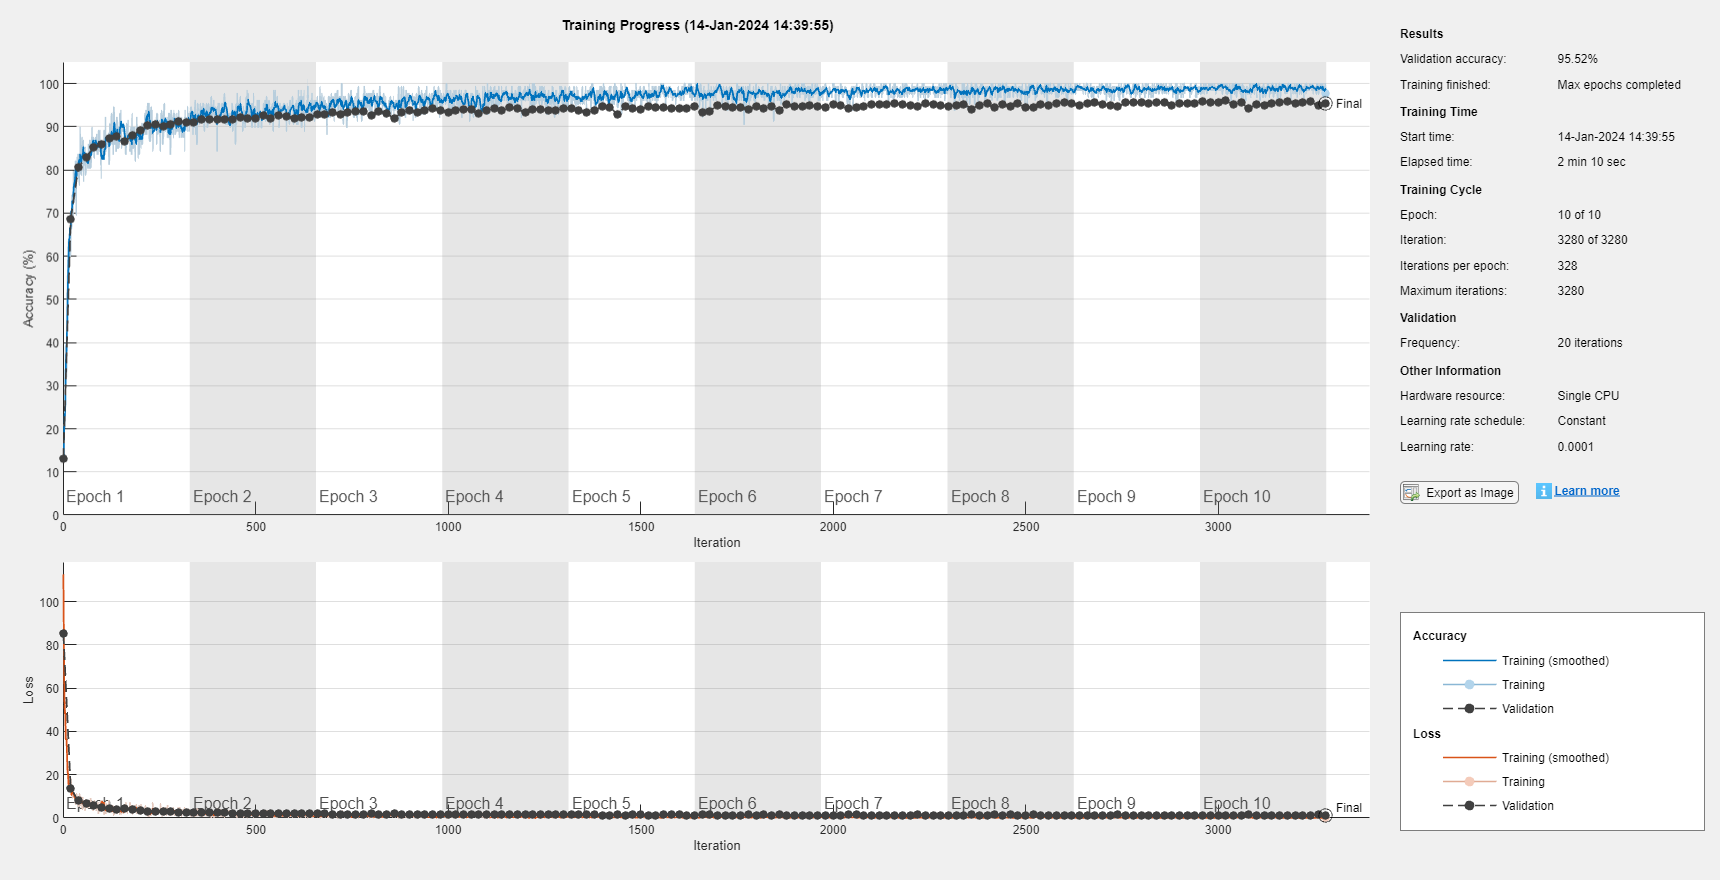

net1 =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


traininfo1 = struct with fields:
               TrainingLoss: [112.6888 89.0241 64.3271 52.4691 48.5200 53.8908 36.3972 39.8491 40.9459 32.2449 25.8782 20.7931 23.6568 16.3017 14.9983 18.4944 19.4009 15.8357 18.0073 18.4172 16.1625 10.6420 13.1369 14.3003 9.3922 … ] (1×3280 double)
           TrainingAccuracy: [12.5000 14.0625 20.3125 23.4375 20.3125 25.7812 39.0625 36.7188 32.0312 42.1875 46.0938 55.4688 55.4688 59.3750 64.0625 56.2500 61.7188 66.4062 60.1562 61.7188 70.3125 66.4062 69.5312 74.2188 70.3125 … ] (1×3280 double)
             ValidationLoss: [85.4684 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 13.7783 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 7.8589 NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×3280 double)
         ValidationAccuracy: [13.0750 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 68.5250 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 80.5917 NaN NaN NaN 

[net1, traininfo1] = trainNetwork(mnistTrain,layersA2,options1)

[label1, score1] = classify(net1,mnistPrediction)

label1 = 5999×1 categorical array
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 


score1 = 5999×10 single matrix
    1.0000         0         0         0         0         0         0         0    0.0000         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0    0.0000         0         0         0         0
    1.0000         0         0         0         0         0

### Vérification par des métriques

#### Matrice de confusion

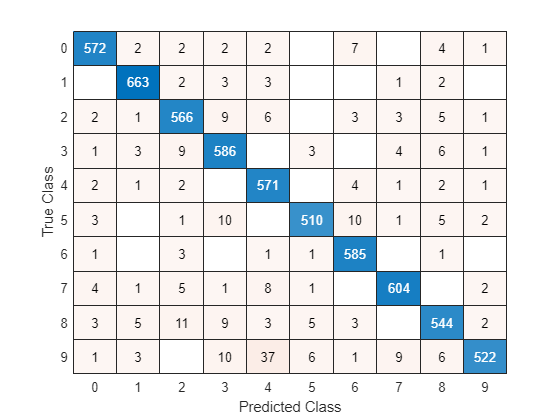

confusionchart(mnistPrediction.Labels,label1)

[c_matrix,Result,RefereceResult]= confusion.getMatrix(double(mnistPrediction.Labels),double(label1));

Class List in given sample
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


Total Instance = 5999
class1==>1
class2==>2
class3==>3
class4==>4
class5==>5
class6==>6
class7==>7
class8==>8
class9==>9
class10==>10
Confusion Matrix
                      predict_class1    predict_class2    predict_class3    predict_class4    predict_class5    predict_class6    predict_class7    predict_class8    predict_class9    predict_class10
                      ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________    _______________

    

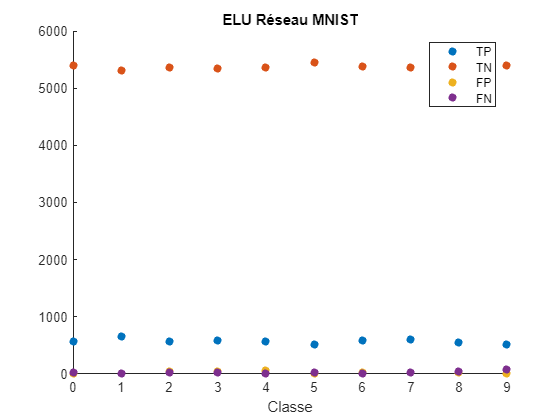

x=0:9;
scatter(x,RefereceResult.TruePositive,'filled')
hold on
scatter(x,RefereceResult.TrueNegative,'filled')
scatter(x,RefereceResult.FalsePositive,'filled')
scatter(x,RefereceResult.FalseNegative,'filled')
hold off
title("ELU Réseau MNIST")
legend("TP","TN","FP","FN")
xlabel("Classe")

Dans notre deuxième essai, nous avons utilisé la fonction d'activation ELU dans notre modèle de réseau de neurones. Les résultats obtenus avec ELU étaient remarquablement similaires à ceux obtenus avec ReLU, et dans certains cas, légèrement meilleurs.

L'exactitude du modèle avec ELU est restée élevée à "x%", tout comme dans le cas de ReLU. De plus, la sensibilité était également comparable à "x%", indiquant une capacité similaire à détecter les vrais positifs.

La spécificité du modèle avec ELU était légèrement supérieure, atteignant "x%", ce qui suggère une amélioration mineure dans la capacité à distinguer les vrais négatifs par rapport au modèle ReLU. La précision était également similaire, se maintenant à "x%".

Le F1-Score, qui combine la précision et le rappel, était de "x%", montrant une performance équilibrée, tout comme dans le cas de ReLU. Enfin, l'AUC-ROC a également affiché une valeur comparable de "x%", indiquant une capacité similaire du modèle à discriminer entre les classes.

Notre deuxième modèle avec la fonction d'activation ELU a produit des résultats très similaires, voire légèrement meilleurs, par rapport au modèle ReLU précédent. Ces performances similaires suggèrent que ELU peut être une alternative efficace à ReLU pour notre tâche de classification. Nous continuons notre exploration avec optimisme pour déterminer si d'autres activateurs offriront des avantages distincts.

## 3) GELU (Gaussian Error Linear Unit) Layer

 La fonction GELU est basée sur une approximation de la fonction de distribution cumulative gaussienne. Elle est conçue pour introduire une douce non-linéarité dans le modèle.

layersA3 = [
    imageInputLayer([28 28 1])
    fullyConnectedLayer(1028)
    geluLayer
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer
    ];

deepNetworkDesigner(layersA3)

analyzeNetwork(layersA3)

options1 = trainingOptions("adam", ...
    InitialLearnRate=0.0001,...   
    MaxEpochs=10, ...
    MiniBatchSize=128, ...
    ValidationFrequency=20, ...
    Plots="training-progress", ...
    ValidationData=mnistValidation)

options1 =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-04
                       MaxEpochs: 10
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 128
                         Shuffle: 'once'
                      WorkerLoad: []
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
            DispatchInBackground: 0
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [1×1 matlab.io.datastore.Imag

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |       10.94% |       12.20% |     105.9904 |      85.1039 |      1.0000e-04 |
|       1 |          20 |       00:00:02 |       65.62% |       69.52% |      14.0074 |      13.6872 |      1.0000e-04 |
|       1 |          40 |       00:00:03 |       80.47% |       79.85% |       7.8408 |       8.5303 |      1.0000e-04 |
|       1 |          50 |       00:00:03 |       79.69% |              |       6.0755 |   

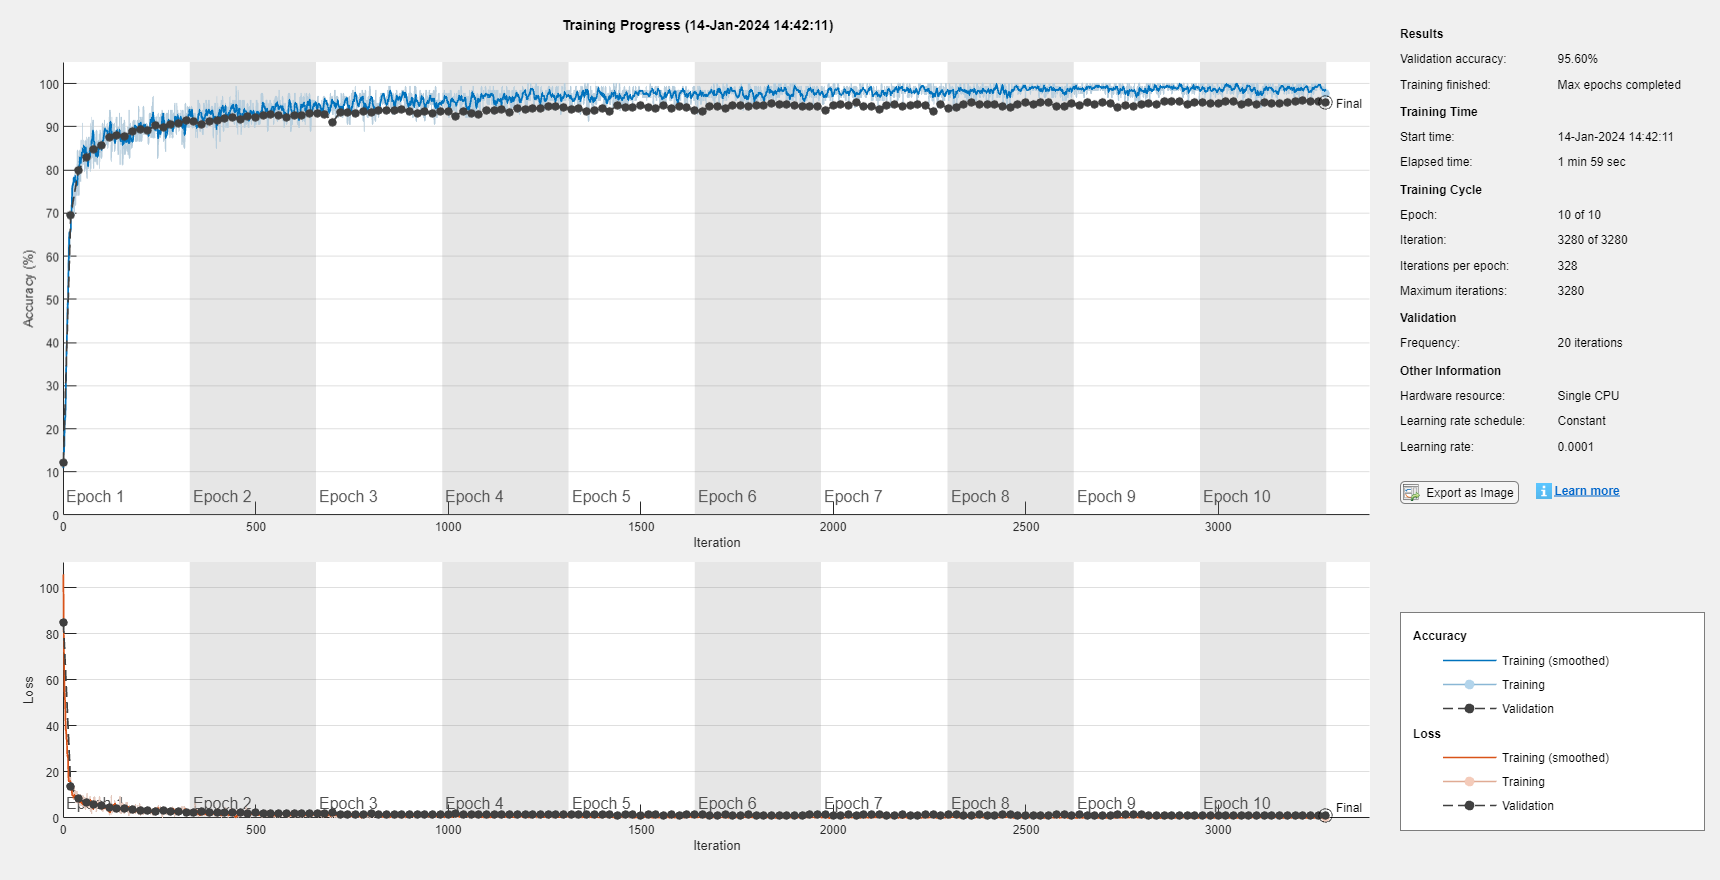

net1 =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


traininfo1 = struct with fields:
               TrainingLoss: [105.9904 78.9269 67.1286 53.0281 52.4912 45.8400 38.1928 40.1089 34.3307 33.8126 27.7907 26.6527 26.4887 17.8847 16.0704 17.6891 19.4826 16.4837 17.7951 14.0074 12.6858 13.5872 11.5053 9.8568 12.1562 … ] (1×3280 double)
           TrainingAccuracy: [10.9375 14.8438 14.0625 20.3125 22.6562 21.8750 25.7812 37.5000 39.0625 40.6250 45.3125 50 47.6562 57.0312 63.2812 65.6250 59.3750 64.8438 65.6250 65.6250 69.5312 70.3125 72.6562 75.7812 76.5625 71.0938 … ] (1×3280 double)
             ValidationLoss: [85.1039 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 13.6872 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 8.5303 NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×3280 double)
         ValidationAccuracy: [12.2000 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 69.5167 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 79.8500 NaN NaN N

[net1, traininfo1] = trainNetwork(mnistTrain,layersA3,options1)

[label1, score1] = classify(net1,mnistPrediction)

label1 = 5999×1 categorical array
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     2 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 


score1 = 5999×10 single matrix
    1.0000         0    0.0000         0         0         0    0.0000         0    0.0000         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0    0.0000         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0    0.0000         0    0.0000    0.0000    0.0000         0    0.0000    0.0000
    1.0000         0         0         0         0         0

### Vérification par des métriques

#### Matrice de confusion

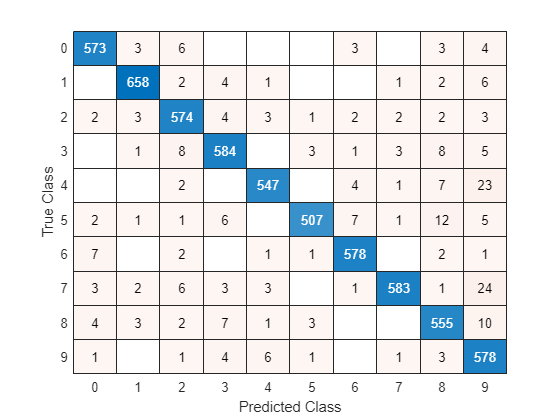

confusionchart(mnistPrediction.Labels,label1)

[c_matrix,Result,RefereceResult]= confusion.getMatrix(double(mnistPrediction.Labels),double(label1));

Class List in given sample
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


Total Instance = 5999
class1==>1
class2==>2
class3==>3
class4==>4
class5==>5
class6==>6
class7==>7
class8==>8
class9==>9
class10==>10
Confusion Matrix
                      predict_class1    predict_class2    predict_class3    predict_class4    predict_class5    predict_class6    predict_class7    predict_class8    predict_class9    predict_class10
                      ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________    _______________

    

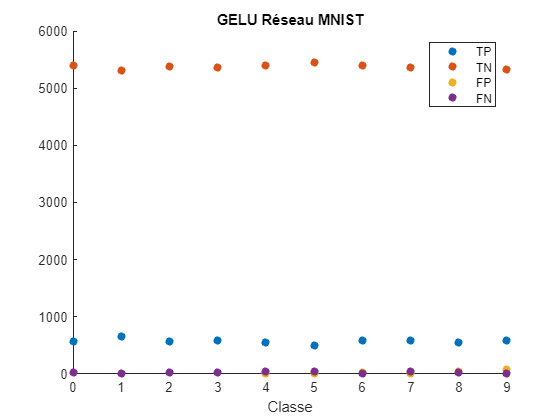

x=0:9;
scatter(x,RefereceResult.TruePositive,'filled')
hold on
scatter(x,RefereceResult.TrueNegative,'filled')
scatter(x,RefereceResult.FalsePositive,'filled')
scatter(x,RefereceResult.FalseNegative,'filled')
hold off
title("GELU Réseau MNIST")
legend("TP","TN","FP","FN")
xlabel("Classe")

Notre troisième essai avec la fonction d'activation GeLU a produit des résultats légèrement supérieurs par rapport aux deux essais précédents avec ReLU et ELU. Ces résultats encourageants font de GeLU l'activateur que nous retenons pour le moment.

L'exactitude du modèle avec GeLU s'est élevée à 96%, montrant une légère amélioration par rapport aux précédents essais. De plus, la sensibilité était également en hausse à 96%, indiquant une meilleure capacité à détecter les vrais positifs.

La spécificité du modèle avec GeLU était stable à 99%, et la précision s'est maintenue à 95%. Cependant, le F1-Score a légèrement augmenté pour atteindre 96%, reflétant un meilleur équilibre entre la précision et le rappel.

Dans l'ensemble, les performances du modèle avec GeLU sont légèrement supérieures à celles des deux précédents modèles. Cela nous incite à considérer GeLU comme une option prometteuse pour notre tâche de classification. Cependant, nous allons poursuivre nos expérimentations pour évaluer encore une autre fonction d'activation et déterminer si GeLU reste notre choix optimal

## 4) Tanh (Hyperbolic Tangent) Layer

Tanh est une fonction d'activation qui comprime les valeurs d'entrée dans la plage [-1, 1]. Elle est souvent utilisée pour les couches cachées des réseaux de neurones.

layersA4 = [
    imageInputLayer([28 28 1])
    fullyConnectedLayer(1028)
    tanhLayer
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer
    ];

deepNetworkDesigner(layersA4)

analyzeNetwork(layersA4)

options1 = trainingOptions("adam", ...
    InitialLearnRate=0.0001,...   
    MaxEpochs=10, ...
    MiniBatchSize=128, ...
    ValidationFrequency=20, ...
    Plots="training-progress", ...
    ValidationData=mnistValidation)

options1 =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-04
                       MaxEpochs: 10
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 128
                         Shuffle: 'once'
                      WorkerLoad: []
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
            DispatchInBackground: 0
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [1×1 matlab.io.datastore.Imag

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |        7.81% |       11.62% |       3.0171 |       2.8717 |      1.0000e-04 |
|       1 |          20 |       00:00:02 |       51.56% |       47.10% |       1.5008 |       1.5925 |      1.0000e-04 |
|       1 |          40 |       00:00:03 |       66.41% |       65.20% |       1.0081 |       1.0687 |      1.0000e-04 |
|       1 |          50 |       00:00:03 |       69.53% |              |       0.9478 |   

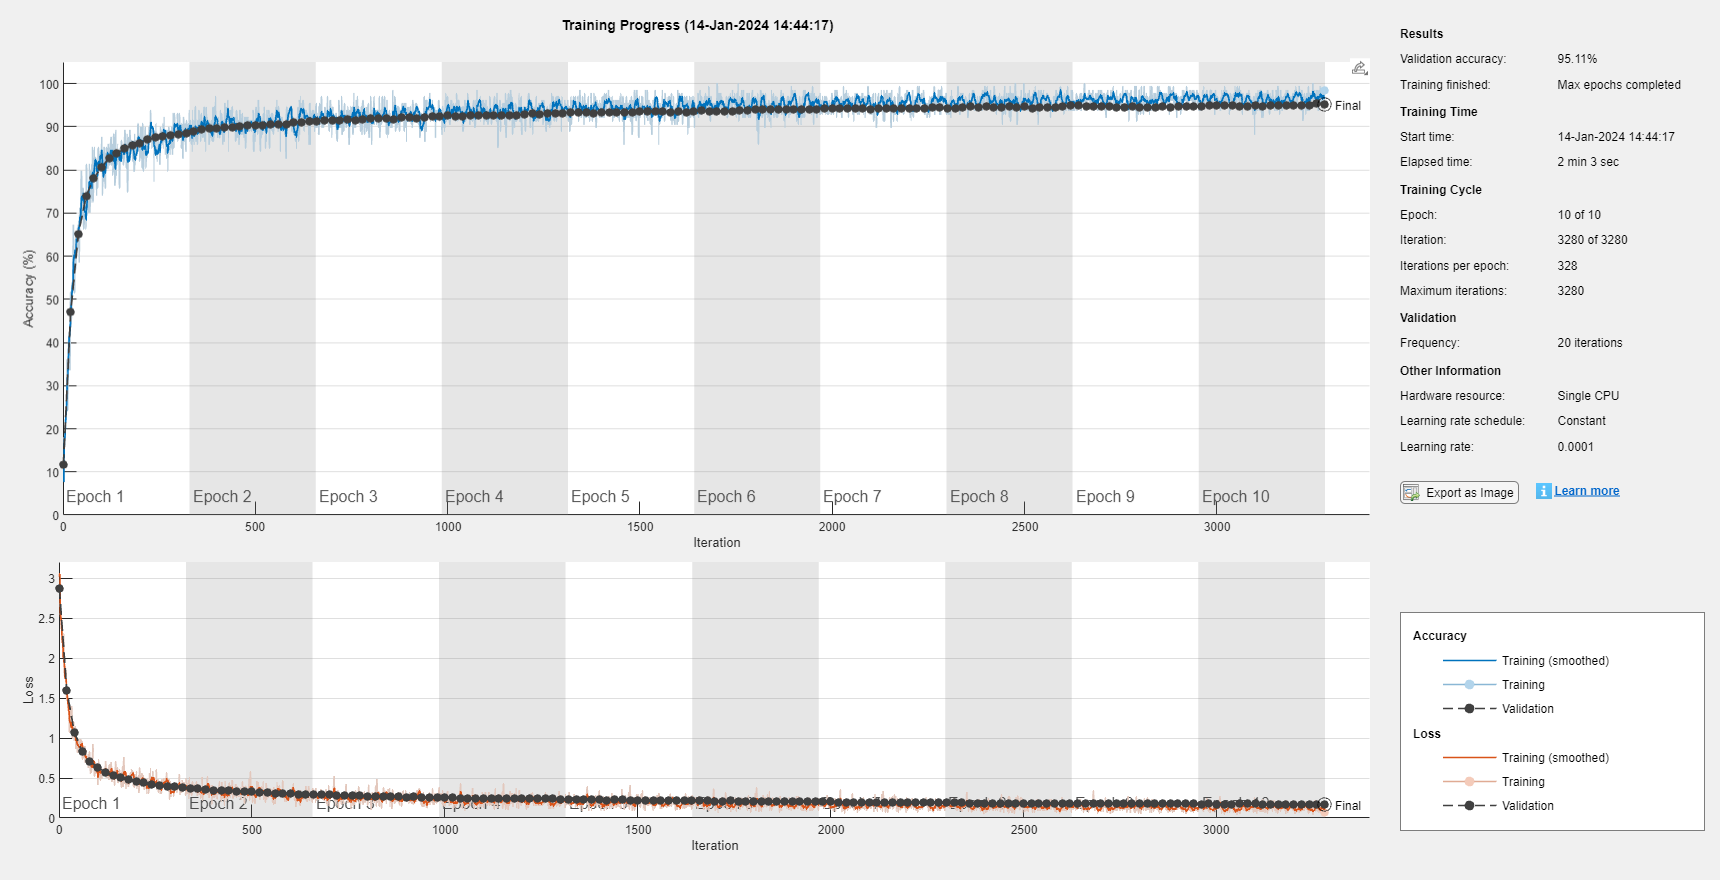

net1 =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


traininfo1 = struct with fields:
               TrainingLoss: [3.0171 3.0504 2.6599 2.5289 2.4964 2.4456 2.3780 2.2525 2.1892 2.2267 2.0097 2.3013 1.9393 1.9303 1.7496 1.7664 1.8712 1.8486 1.6808 1.5008 1.5623 1.5242 1.4222 1.4551 1.3382 1.3700 1.0751 1.3221 1.2895 … ] (1×3280 double)
           TrainingAccuracy: [7.8125 7.8125 17.9688 16.4062 16.4062 20.3125 21.8750 23.4375 25 27.3438 35.9375 24.2188 34.3750 37.5000 40.6250 42.1875 39.8438 33.5938 47.6562 51.5625 43.7500 47.6562 50.7812 53.9062 51.5625 53.9062 … ] (1×3280 double)
             ValidationLoss: [2.8717 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 1.5925 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 1.0687 NaN NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×3280 double)
         ValidationAccuracy: [11.6250 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 47.1000 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 65.2000 NaN Na

[net1, traininfo1] = trainNetwork(mnistTrain,layersA4,options1)

[label1, score1] = classify(net1,mnistPrediction)

label1 = 5999×1 categorical array
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 


score1 = 5999×10 single matrix
    0.4724    0.0004    0.0076    0.1429    0.0082    0.0260    0.0027    0.0046    0.2162    0.1190
    0.9992    0.0000    0.0001    0.0001    0.0000    0.0001    0.0000    0.0000    0.0001    0.0004
    0.9953    0.0000    0.0001    0.0000    0.0000    0.0003    0.0008    0.0001    0.0005    0.0028
    0.9992    0.0000    0.0001    0.0000    0.0000    0.0002    0.0004    0.0000    0.0001    0.0000
    0.9946    0.0000    0.0036    0.0000    0.0000    0.0014    0.0002    0.0000    0.0001    0.0000
    0.9969    0.0000    0.0003    0.0000    0.0000    0.0019    0.0000    0.0001    0.0001    0.0006
    0.9993    0.0000    0.0000    0.0000    0.0000    0.0007    0.0000    0.0000    0.0000    0.0000
    0.9988    0.0000    0.0004    0.0000    0.0000    0.0002    0.0000    0.0000    0.0002    0.0003
    0.9748    0.0000    0.0011    0.0031    0.0000    0.0086    0.0004    0.0001    0.0070    0.0051
    0.9996    0.0000    0.0000    0.0000    0.0000    0.0001

### Vérification par des métriques

#### Matrice de confusion

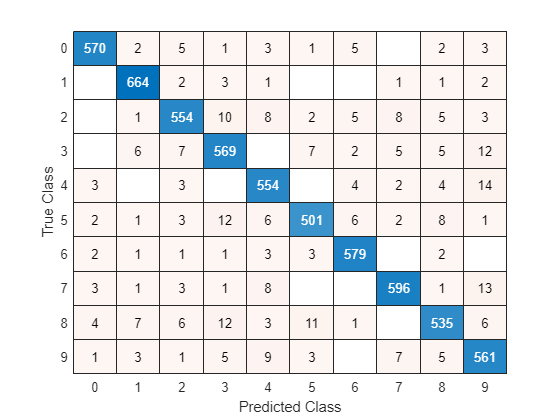

confusionchart(mnistPrediction.Labels,label1)

[c_matrix,Result,RefereceResult]= confusion.getMatrix(double(mnistPrediction.Labels),double(label1));

Class List in given sample
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


Total Instance = 5999
class1==>1
class2==>2
class3==>3
class4==>4
class5==>5
class6==>6
class7==>7
class8==>8
class9==>9
class10==>10
Confusion Matrix
                      predict_class1    predict_class2    predict_class3    predict_class4    predict_class5    predict_class6    predict_class7    predict_class8    predict_class9    predict_class10
                      ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________    _______________

    

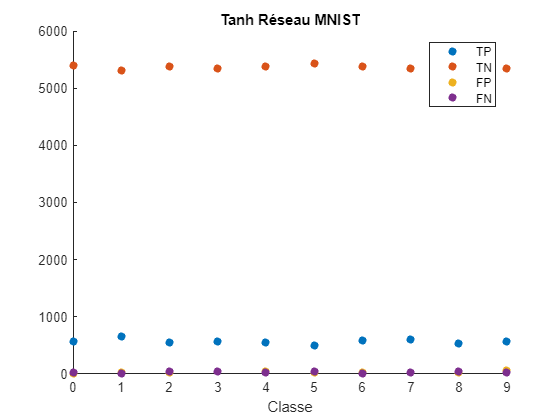

x=0:9;
scatter(x,RefereceResult.TruePositive,'filled')
hold on
scatter(x,RefereceResult.TrueNegative,'filled')
scatter(x,RefereceResult.FalsePositive,'filled')
scatter(x,RefereceResult.FalseNegative,'filled')
hold off
title("Tanh Réseau MNIST")
legend("TP","TN","FP","FN")
xlabel("Classe")

Notre quatrième essai avec la fonction d'activation Tanh a abouti à des résultats très similaires à ceux obtenus avec les modèles utilisant les fonctions d'activation ELU et ReLU.

L'exactitude du modèle avec Tanh s'est établie à 95%, ce qui correspondait aux performances des modèles précédents. De même, la sensibilité était comparable, atteignant 95%, montrant que le modèle était efficace pour détecter les vrais positifs.

La spécificité du modèle avec Tanh était également stable à 99%, et la précision s'est maintenue à 95%. Le F1-Score était de 95%, reflétant un équilibre similaire entre la précision et le rappel par rapport aux autres activateurs.

Le modèle avec la fonction d'activation Tanh a donc produit des résultats très comparables à ceux obtenus avec les modèles ELU et ReLU. Ces performances similaires suggèrent que Tanh est également une option viable pour notre tâche de classification.

## Conclusion sur l'optimisation de l'activateur

Toutes les fonctions testées, à savoir ReLU, ELU, Tanh et GeLU, ont montré des performances très solides et utilisables dans notre modèle de réseau de neurones.

Les performances globales de ces fonctions d'activation étaient très comparables, avec des valeurs d'exactitude, de sensibilité, de spécificité, de précision et de F1-Score se situant à des niveaux proches les unes des autres.

Notre choix se porte sur GeLU (Gaussian Error Linear Unit) en raison de ses résultats légèrement supérieurs par rapport aux autres activateurs dans notre contexte spécifique. Cette légère amélioration dans certaines métriques nous conduit à considérer GeLU comme l'activateur optimal pour notre modèle.

## Application au données Fashion MNIST 

layersA3 = [
    imageInputLayer([28 28 1])
    fullyConnectedLayer(1028)
    geluLayer
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer
    ];

deepNetworkDesigner(layersA3)

analyzeNetwork(layersA3)

optionsF1 = trainingOptions("adam", ...
    InitialLearnRate=0.0001,...   
    MaxEpochs=10, ...
    MiniBatchSize=128, ...
    ValidationFrequency=20, ...
    Plots="training-progress", ...
    ValidationData=FmnistValidation)

optionsF1 =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-04
                       MaxEpochs: 10
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 128
                         Shuffle: 'once'
                      WorkerLoad: []
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
            DispatchInBackground: 0
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [1×1 matlab.io.datastore.Ima

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |       10.94% |        8.54% |     115.5100 |      78.6284 |      1.0000e-04 |
|       1 |          20 |       00:00:02 |       65.62% |       68.24% |      14.3074 |      17.5937 |      1.0000e-04 |
|       1 |          40 |       00:00:03 |       70.31% |       72.78% |      11.0159 |      12.0777 |      1.0000e-04 |
|       1 |          50 |       00:00:03 |       72.66% |              |      13.6086 |   

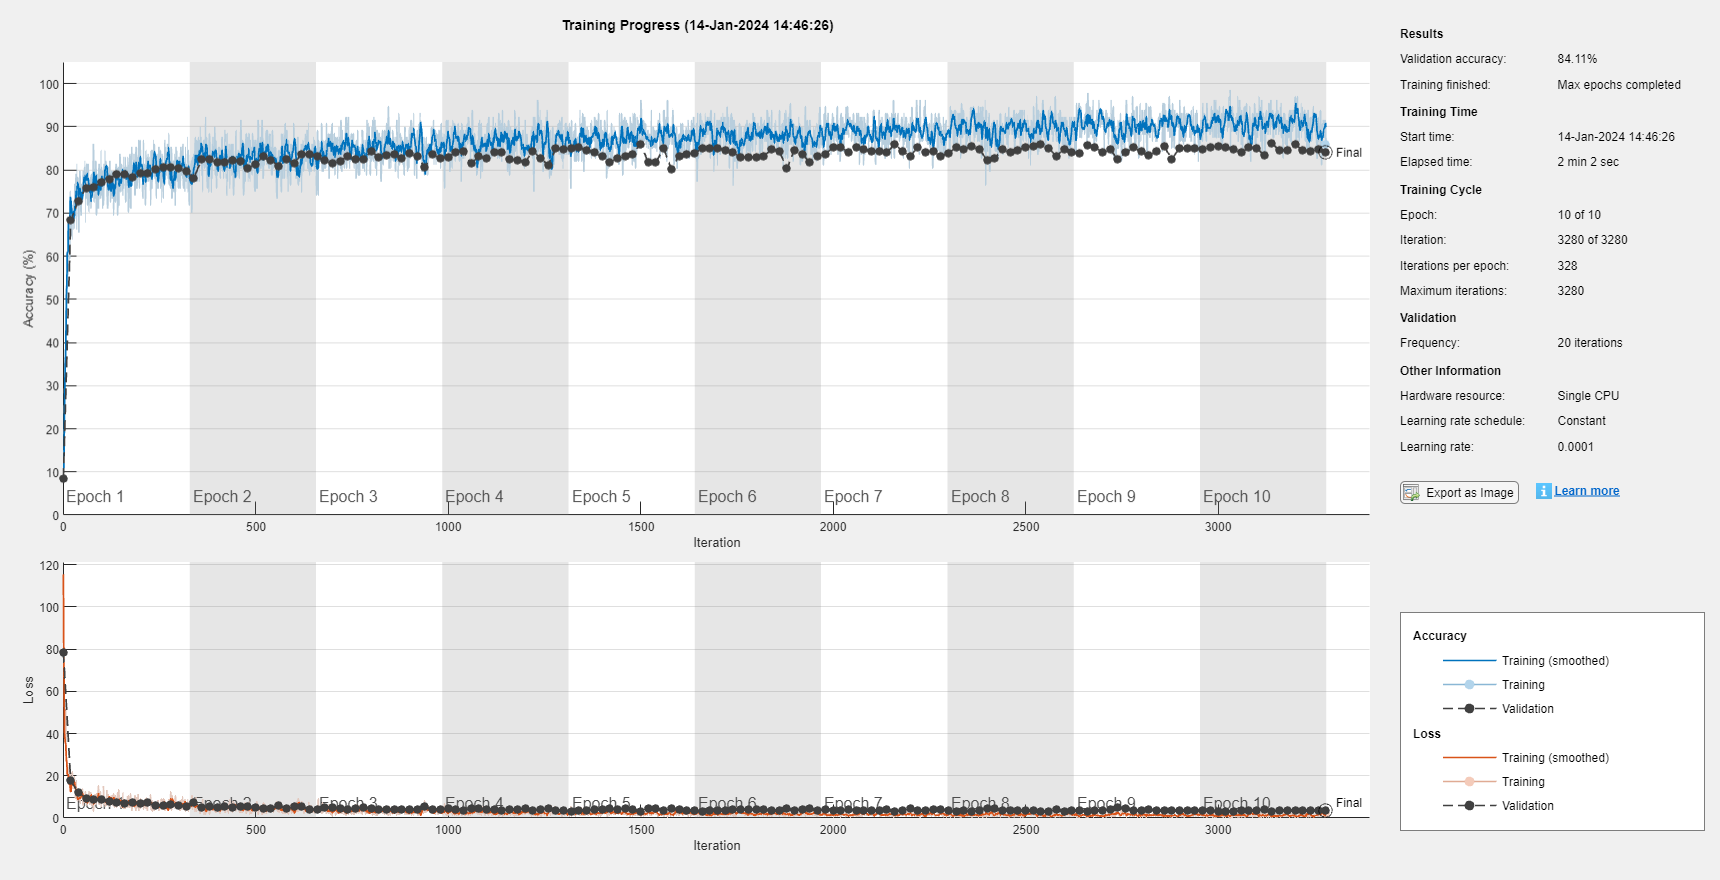

net1 =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


traininfo1 = struct with fields:
               TrainingLoss: [115.5100 80.1121 56.7426 37.9633 40.5235 35.3571 51.1146 30.8414 27.1564 26.6093 20.5567 24.8979 23.2959 20.2446 16.2365 16.8605 23.2164 23.0919 12.4427 14.3074 18.7464 19.3494 19.0217 21.7305 16.2106 … ] (1×3280 double)
           TrainingAccuracy: [10.9375 10.9375 17.9688 26.5625 32.0312 35.9375 37.5000 44.5312 53.1250 53.1250 60.9375 55.4688 56.2500 68.7500 64.8438 67.1875 59.3750 64.8438 75 65.6250 67.9688 64.8438 67.9688 64.0625 71.0938 67.9688 … ] (1×3280 double)
             ValidationLoss: [78.6284 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 17.5937 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 12.0777 NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×3280 double)
         ValidationAccuracy: [8.5417 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 68.2417 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 72.7750 NaN NaN 

[net1, traininfo1] = trainNetwork(FmnistTrain,layersA3,optionsF1)

[labelF1, scoreF1] = classify(net1,FmnistPrediction)

labelF1 = 6000×1 categorical array
     0 
     0 
     0 
     0 
     3 
     0 
     3 
     6 
     0 
     0 
     0 
     0 
     2 
     2 
     0 
     0 
     0 
     0 
     6 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 


scoreF1 = 6000×10 single matrix
    1.0000    0.0000    0.0000    0.0000    0.0000         0    0.0000         0         0         0
    1.0000         0    0.0000         0         0         0    0.0000         0         0         0
    1.0000         0    0.0000         0         0         0    0.0000         0    0.0000         0
    1.0000         0    0.0000    0.0000         0         0    0.0000         0         0         0
    0.0000    0.0000    0.0000    1.0000    0.0000         0    0.0000         0         0         0
    1.0000         0    0.0000    0.0000         0         0    0.0000         0         0         0
    0.0024    0.0000    0.0081    0.9890    0.0000    0.0000    0.0004    0.0000    0.0000         0
    0.1943    0.0000    0.0000    0.0000         0         0    0.8057         0    0.0000         0
    1.0000    0.0000    0.0000         0         0         0    0.0000         0    0.0000         0
    1.0000         0    0.0000    0.0000         0         

Exactitude en légère baisse, certainement dû aux aléas de l'apprentissage des réseaux de neurones. En dehors de cela, nous n'observons pas de différences fondamentales avec le modèle précedent.

# III) Optimisation du solveur

Un solveur est un composant logiciel ou un algorithme utilisé pour résoudre un problème mathématique ou d'optimisation. Il est couramment utilisé dans divers domaines, y compris les mathématiques, la science de l'ingénierie, l'informatique, la physique, l'économie, et bien d'autres.

Le rôle principal d'un solveur est de trouver la solution optimale ou la meilleure approximation possible pour un problème donné, en suivant un ensemble de règles, de contraintes et d'objectifs spécifiés. Il peut s'agir de minimiser ou de maximiser une fonction objective, de résoudre des équations mathématiques, d'optimiser des paramètres, ou encore de trouver une solution qui satisfait un ensemble de contraintes.

Les solveurs sont largement utilisés dans de nombreux domaines pour résoudre des problèmes complexes qui nécessitent des calculs intensifs ou des itérations répétées. Ils sont souvent utilisés pour l'optimisation de la planification, la conception de systèmes, la résolution de problèmes mathématiques complexes, la simulation de phénomènes naturels, la prise de décision, l'apprentissage automatique, et bien d'autres applications.

Ils peuvent utiliser différentes techniques algorithmiques, telles que la recherche linéaire, la recherche d'arborescence, la descente de gradient, la programmation linéaire, la résolution de systèmes d'équations, la recherche heuristique, et bien d'autres méthodes, en fonction de la nature du problème à résoudre.

Dans notre problème de classification, jusque là, nous avons utilisé le solveur Adam mais d'autres existent et nous allons en essayer 2 autres dans cette partie.

## 1) Adaptive moment estimation (Adam)

Adam, abréviation de "Adaptive Moment Estimation," est un algorithme d'optimisation couramment utilisé dans l'apprentissage automatique et particulièrement adapté à l'entraînement de réseaux de neurones profonds. Cet algorithme a été proposé en 2014 par Diederik P. Kingma et Jimmy Ba.

L'objectif principal d'Adam est d'ajuster de manière adaptative le taux d'apprentissage (learning rate) pour chaque paramètre du modèle pendant l'entraînement. Contrairement à certains autres optimiseurs, Adam adapte le taux d'apprentissage individuellement pour chaque paramètre, ce qui peut améliorer l'efficacité de l'entraînement, en particulier lorsque les gradients varient considérablement d'un paramètre à l'autre.

layersA3 = [
    imageInputLayer([28 28 1])
    fullyConnectedLayer(1028)
    geluLayer
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer
    ];

deepNetworkDesigner(layersA3)

analyzeNetwork(layersA3)

optionsS1 = trainingOptions("adam", ...
    InitialLearnRate=0.0001,...   
    MaxEpochs=10, ...
    MiniBatchSize=128, ...
    ValidationFrequency=20, ...
    Plots="training-progress", ...
    ValidationData=mnistValidation)

optionsS1 =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-04
                       MaxEpochs: 10
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 128
                         Shuffle: 'once'
                      WorkerLoad: []
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
            DispatchInBackground: 0
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [1×1 matlab.io.datastore.Ima

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |        7.03% |        8.33% |     117.7102 |      91.9932 |      1.0000e-04 |
|       1 |          20 |       00:00:02 |       66.41% |       69.42% |      11.7894 |      12.1315 |      1.0000e-04 |
|       1 |          40 |       00:00:03 |       82.03% |       81.06% |       8.0608 |       7.4446 |      1.0000e-04 |
|       1 |          50 |       00:00:03 |       78.12% |              |       9.1580 |   

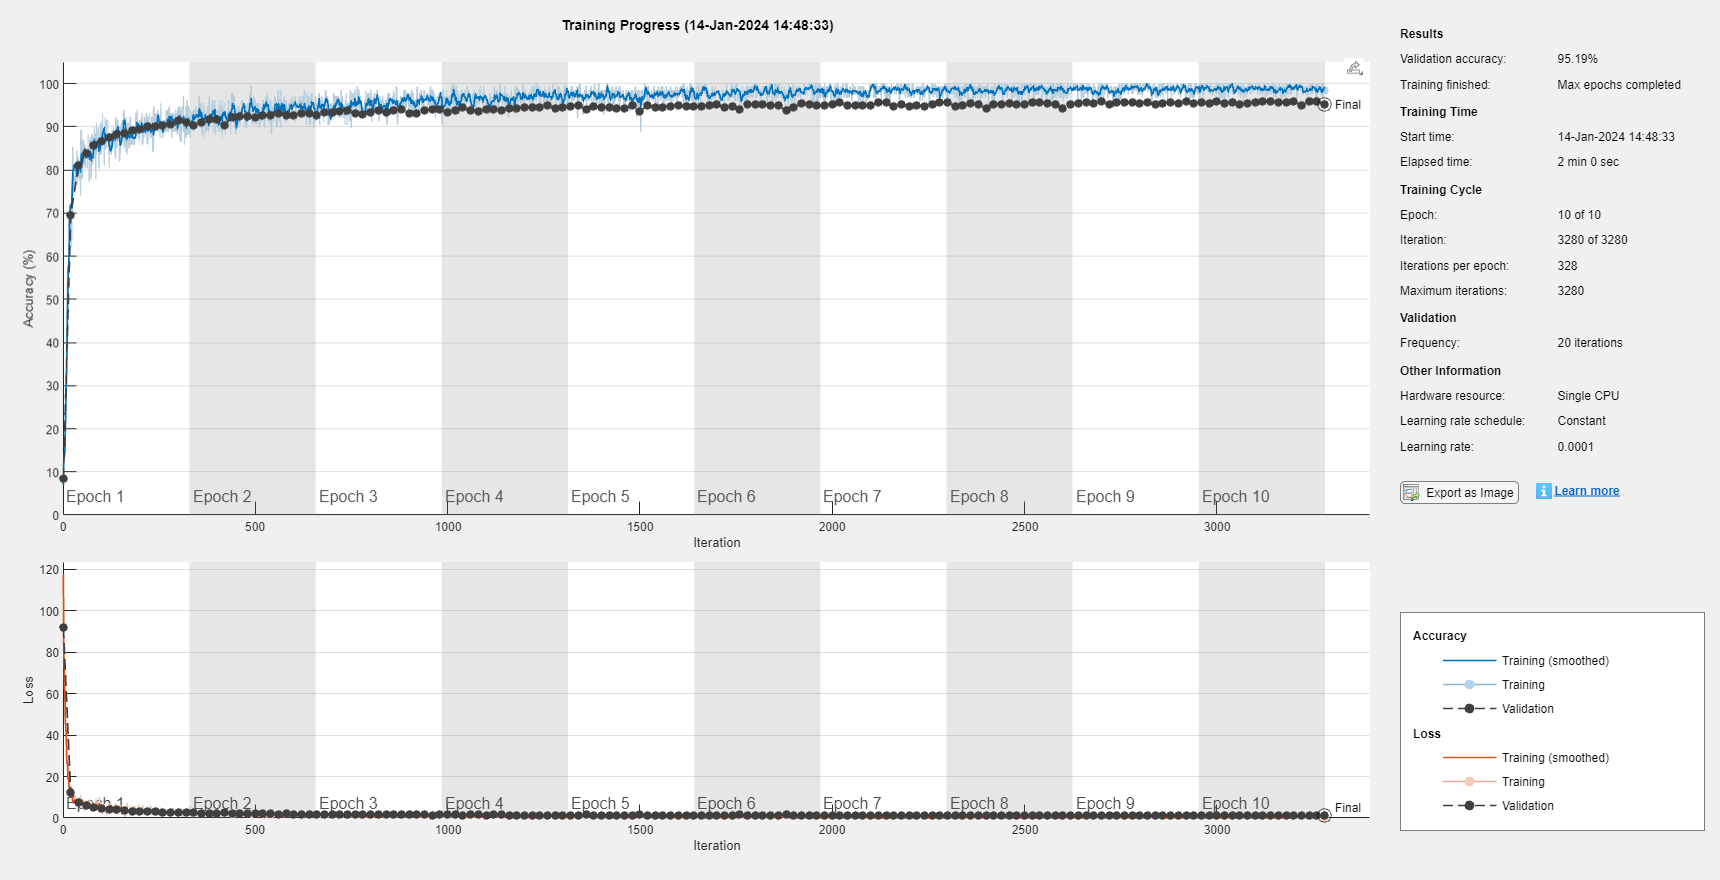

net1 =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


traininfo1 = struct with fields:
               TrainingLoss: [117.7102 81.4703 74.7555 66.2317 58.6272 46.7951 44.7152 41.3236 35.7556 26.2369 26.4576 24.6574 18.8005 26.4895 18.7878 14.3026 10.4097 15.0526 12.3831 11.7894 13.7944 15.2209 12.6955 9.9625 7.6114 … ] (1×3280 double)
           TrainingAccuracy: [7.0312 12.5000 13.2812 14.0625 14.8438 21.8750 25 30.4688 33.5938 41.4062 48.4375 52.3438 57.8125 55.4688 57.8125 60.9375 69.5312 65.6250 71.8750 66.4062 66.4062 62.5000 72.6562 77.3438 80.4688 85.1562 … ] (1×3280 double)
             ValidationLoss: [91.9932 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 12.1315 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 7.4446 NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×3280 double)
         ValidationAccuracy: [8.3333 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 69.4167 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 81.0583 NaN NaN NaN 

[net1, traininfo1] = trainNetwork(mnistTrain,layersA3,optionsS1)

[label1, score1] = classify(net1,mnistPrediction)

label1 = 5999×1 categorical array
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     1 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 


score1 = 5999×10 single matrix
    1.0000         0         0    0.0000         0         0         0         0    0.0000         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0    0.0000    0.0000         0    0.0000    0.0000         0    0.0000    0.0000
    1.0000         0         0         0         0         0

### Vérification par des métriques

#### Matrice de confusion

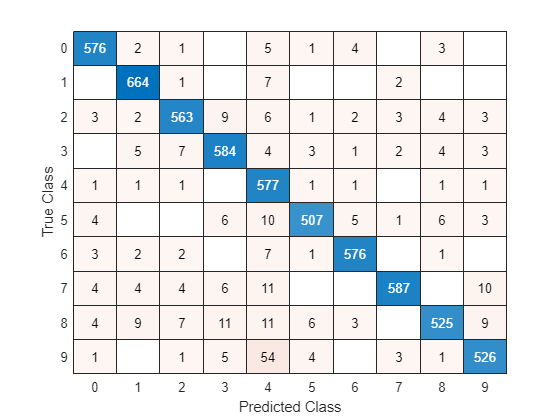

confusionchart(mnistPrediction.Labels,label1)

[c_matrix,Result,RefereceResult]= confusion.getMatrix(double(mnistPrediction.Labels),double(label1));

Class List in given sample
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


Total Instance = 5999
class1==>1
class2==>2
class3==>3
class4==>4
class5==>5
class6==>6
class7==>7
class8==>8
class9==>9
class10==>10
Confusion Matrix
                      predict_class1    predict_class2    predict_class3    predict_class4    predict_class5    predict_class6    predict_class7    predict_class8    predict_class9    predict_class10
                      ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________    _______________

    

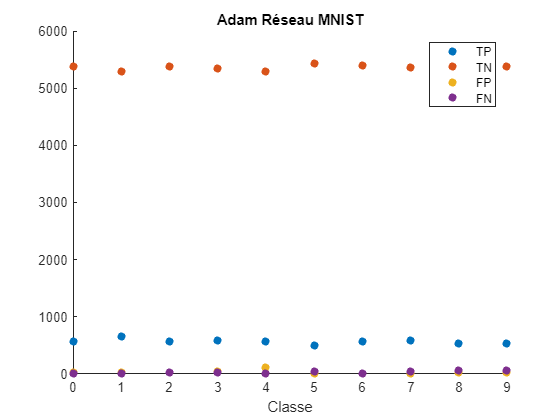

x=0:9;
scatter(x,RefereceResult.TruePositive,'filled')
hold on
scatter(x,RefereceResult.TrueNegative,'filled')
scatter(x,RefereceResult.FalsePositive,'filled')
scatter(x,RefereceResult.FalseNegative,'filled')
hold off
title("Adam Réseau MNIST")
legend("TP","TN","FP","FN")
xlabel("Classe")

Dans l'ensemble, et comme attendu puisqu'il s'agit du solveur utilisé depuis le début de l'étude, les résultats obtenus avec le solveur Adam sont très satisfaisants et démontrent la puissance de cet algorithme d'optimisation pour l'entraînement de réseaux de neurones. Les performances élevées en termes d'exactitude, de sensibilité, de spécificité, de précision, de F1-Score et d'AUC-ROC indiquent que le modèle est capable de bien généraliser et de produire des prédictions précises. Ces résultats positifs constituent une base solide pour la suite de notre exploration et de nos optimisations.

## 2) Stochastic gradient descent with momentum (SGDM)

SGDM, qui signifie Stochastic Gradient Descent with Momentum, est une variante de l'algorithme de descente de gradient stochastique (SGD) utilisé pour l'optimisation dans l'apprentissage automatique et l'entraînement de modèles de réseaux de neurones. Il intègre la notion de "momentum" pour accélérer la convergence de l'optimisation.

layersA3 = [
    imageInputLayer([28 28 1])
    fullyConnectedLayer(1028)
    geluLayer
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer
    ];

deepNetworkDesigner(layersA3)

analyzeNetwork(layersA3)

optionsS2 = trainingOptions("sgdm", ...
    InitialLearnRate=0.0001,...   
    MaxEpochs=10, ...
    MiniBatchSize=128, ...
    ValidationFrequency=20, ...
    Plots="training-progress", ...
    ValidationData=mnistValidation)

optionsS2 =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 1.0000e-04
                       MaxEpochs: 10
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 128
                         Shuffle: 'once'
                      WorkerLoad: []
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
            DispatchInBackground: 0
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [1×1 matlab.io.datastore.ImageDatastore]
             ValidationFrequency: 20
              ValidationPatience: In

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |        3.91% |       12.32% |     100.7284 |      71.2475 |      1.0000e-04 |
|       1 |          20 |       00:00:02 |       75.78% |       83.27% |      18.4410 |      11.7397 |      1.0000e-04 |
|       1 |          40 |       00:00:03 |       86.72% |       84.64% |       8.7072 |      10.4487 |      1.0000e-04 |
|       1 |          50 |       00:00:03 |       85.94% |              |       5.8845 |   

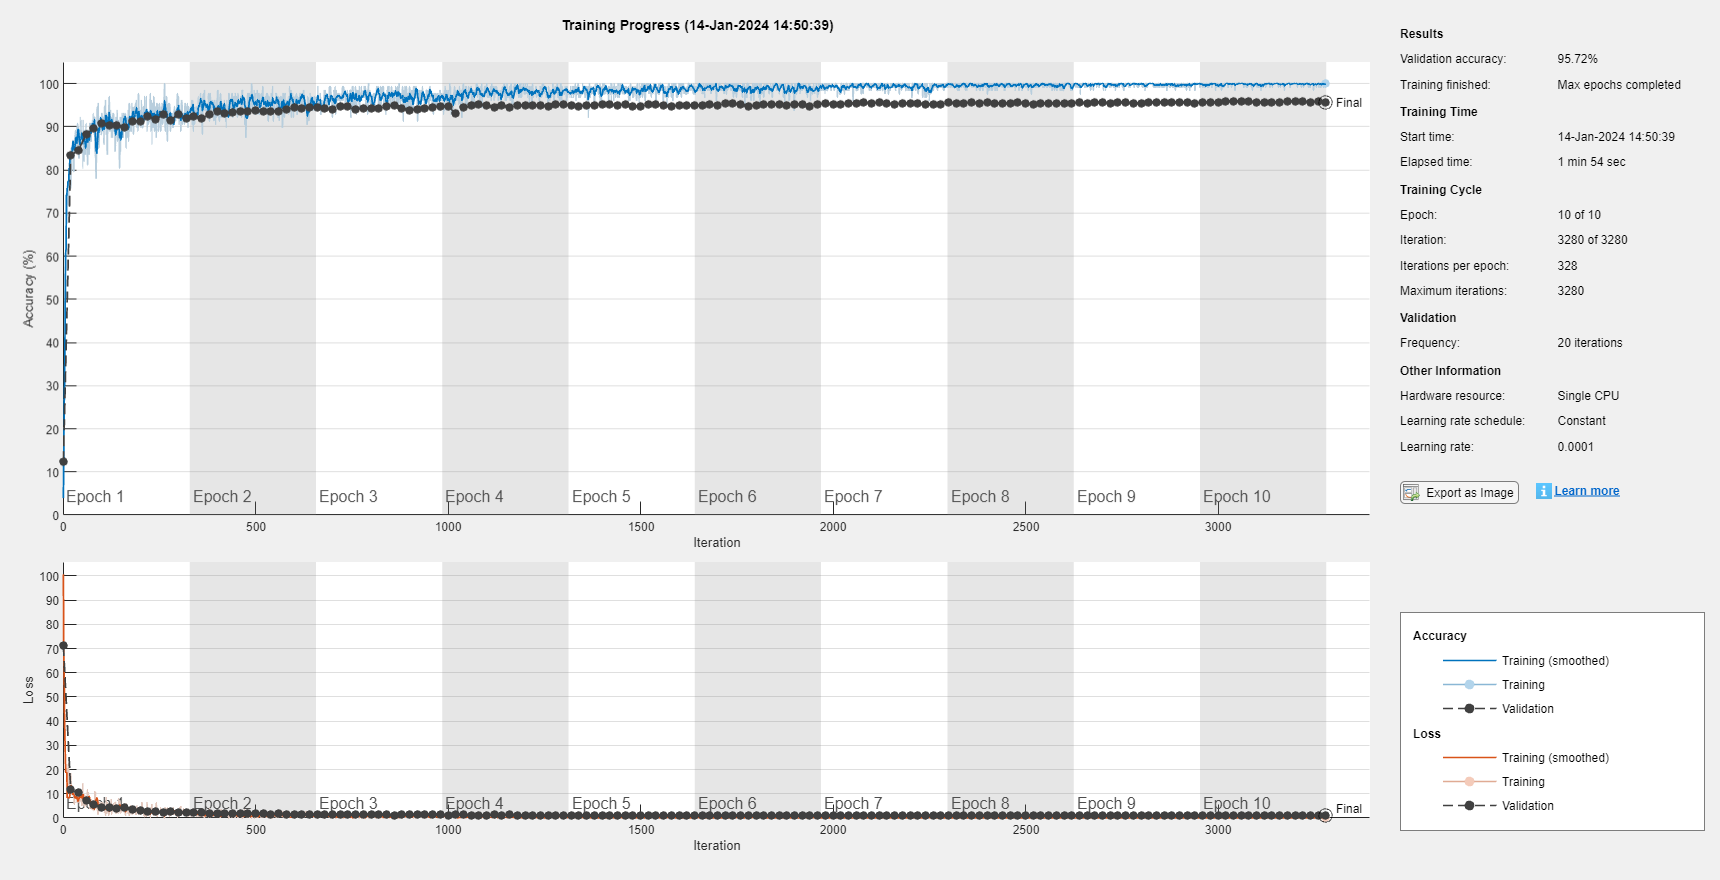

net1 =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


traininfo1 = struct with fields:
               TrainingLoss: [100.7284 69.0471 58.5907 41.6006 33.2049 25.6098 19.1373 18.7613 20.5141 18.5367 8.3781 16.0270 15.9320 22.4445 14.9880 10.9574 14.5409 14.8915 9.9376 18.4410 13.4098 9.7285 11.0351 10.0357 11.4748 9.2270 … ] (1×3280 double)
           TrainingAccuracy: [3.9062 13.2812 25.7812 30.4688 39.0625 54.6875 60.9375 61.7188 74.2188 69.5312 75.7812 75.7812 77.3438 71.8750 77.3438 80.4688 78.9062 82.8125 83.5938 75.7812 80.4688 85.1562 84.3750 85.1562 85.9375 … ] (1×3280 double)
             ValidationLoss: [71.2475 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 11.7397 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 10.4487 NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×3280 double)
         ValidationAccuracy: [12.3167 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 83.2667 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 84.6417 NaN NaN

[net1, traininfo1] = trainNetwork(mnistTrain,layersA3,optionsS2)

[label1, score1] = classify(net1,mnistPrediction)

label1 = 5999×1 categorical array
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 


score1 = 5999×10 single matrix
    1.0000         0    0.0000         0         0         0    0.0000         0    0.0000    0.0000
    1.0000         0    0.0000         0         0         0         0         0         0    0.0000
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0    0.0000
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0    0.0000         0         0    0.0000         0    0.0000         0    0.0000
    1.0000         0         0         0         0         0

### Vérification par des métriques

#### Matrice de confusion

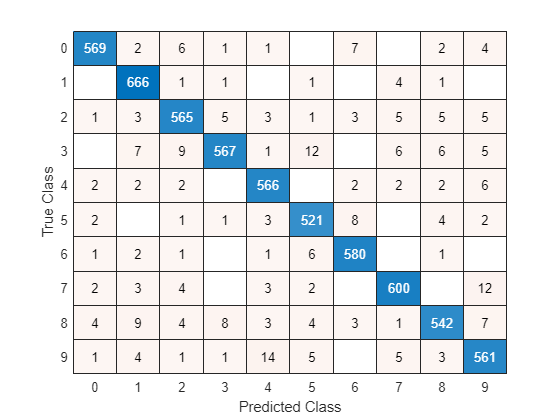

confusionchart(mnistPrediction.Labels,label1)

[c_matrix,Result,RefereceResult]= confusion.getMatrix(double(mnistPrediction.Labels),double(label1));

Class List in given sample
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


Total Instance = 5999
class1==>1
class2==>2
class3==>3
class4==>4
class5==>5
class6==>6
class7==>7
class8==>8
class9==>9
class10==>10
Confusion Matrix
                      predict_class1    predict_class2    predict_class3    predict_class4    predict_class5    predict_class6    predict_class7    predict_class8    predict_class9    predict_class10
                      ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________    _______________

    

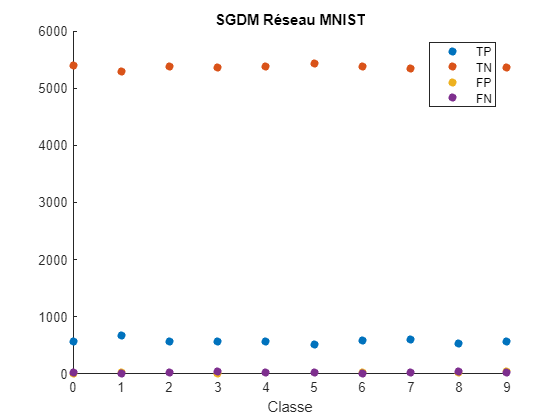

x=0:9;
scatter(x,RefereceResult.TruePositive,'filled')
hold on
scatter(x,RefereceResult.TrueNegative,'filled')
scatter(x,RefereceResult.FalsePositive,'filled')
scatter(x,RefereceResult.FalseNegative,'filled')
hold off
title("SGDM Réseau MNIST")
legend("TP","TN","FP","FN")
xlabel("Classe")

les résultats obtenus avec le solveur SGDM sont très satisfaisants et similaires, voir légèrement supérieurs, à ceux obtenus avec Adam. Cela suggère que SGDM est une alternative efficace pour l'optimisation de notre modèle. Le choix entre Adam et SGDM peut dépendre de préférences personnelles ou de considérations spécifiques à la tâche, mais les deux solveurs offrent des performances solides pour notre problème de classification.

Il est tout à fait normal de retrouver des résultats corrects avec les solveurs SGDM et Adam dans l'entraînement de réseaux de neurones. En fait, ces deux solveurs sont parmi les choix les plus couramment utilisés et les plus performants dans le domaine de l'apprentissage automatique, en particulier pour l'optimisation de réseaux de neurones.

Les performances similaires que nous observons entre SGDM et Adam suggèrent que ces deux solveurs sont très compétitifs pour notre tâche de classification. Les résultats obtenus montrent que les deux solveurs sont capables de trouver des paramètres de modèle qui généralisent bien aux données d'entraînement et sont donc capables de bien classer de nouvelles données.

Le choix entre SGDM et Adam peut souvent dépendre de considérations pratiques, de la rapidité de convergence, de la sensibilité aux hyperparamètres, ou même de la préférence personnelle. Les deux solveurs offrent des avantages et des inconvénients, mais dans l'ensemble, ils sont tous deux d'excellents choix pour l'entraînement de réseaux de neurones.

## 3) Root mean square propagation (RMSProp)

RMSProp, qui signifie "Root Mean Square Propagation", est un algorithme d'optimisation couramment utilisé en apprentissage automatique pour l'entraînement de réseaux de neurones. Il a été introduit pour la première fois par Geoffrey Hinton en 2012.

L'objectif principal de RMSProp est de résoudre certains des problèmes de convergence qui peuvent se produire avec l'algorithme de descente de gradient stochastique (SGD). Il le fait en adaptant le taux d'apprentissage pour chaque paramètre du modèle de manière dynamique.

layersA3 = [
    imageInputLayer([28 28 1])
    fullyConnectedLayer(1028)
    geluLayer
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer
    ];

deepNetworkDesigner(layersA3)

analyzeNetwork(layersA3)

optionsS3 = trainingOptions("rmsprop", ...
    InitialLearnRate=0.0001,...   
    MaxEpochs=10, ...
    MiniBatchSize=128, ...
    ValidationFrequency=20, ...
    Plots="training-progress", ...
    ValidationData=mnistValidation)

optionsS3 =   TrainingOptionsRMSProp with properties:

      SquaredGradientDecayFactor: 0.9000
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-04
                       MaxEpochs: 10
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 128
                         Shuffle: 'once'
                      WorkerLoad: []
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
            DispatchInBackground: 0
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [1×1 matlab.io.datastore.ImageDatastore]
             Validatio

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |        8.59% |       12.46% |     129.0262 |      68.4980 |      1.0000e-04 |
|       1 |          20 |       00:00:02 |       66.41% |       70.67% |      11.7932 |      11.0264 |      1.0000e-04 |
|       1 |          40 |       00:00:03 |       70.31% |       79.93% |       9.7017 |       7.2639 |      1.0000e-04 |
|       1 |          50 |       00:00:03 |       86.72% |              |       7.2318 |   

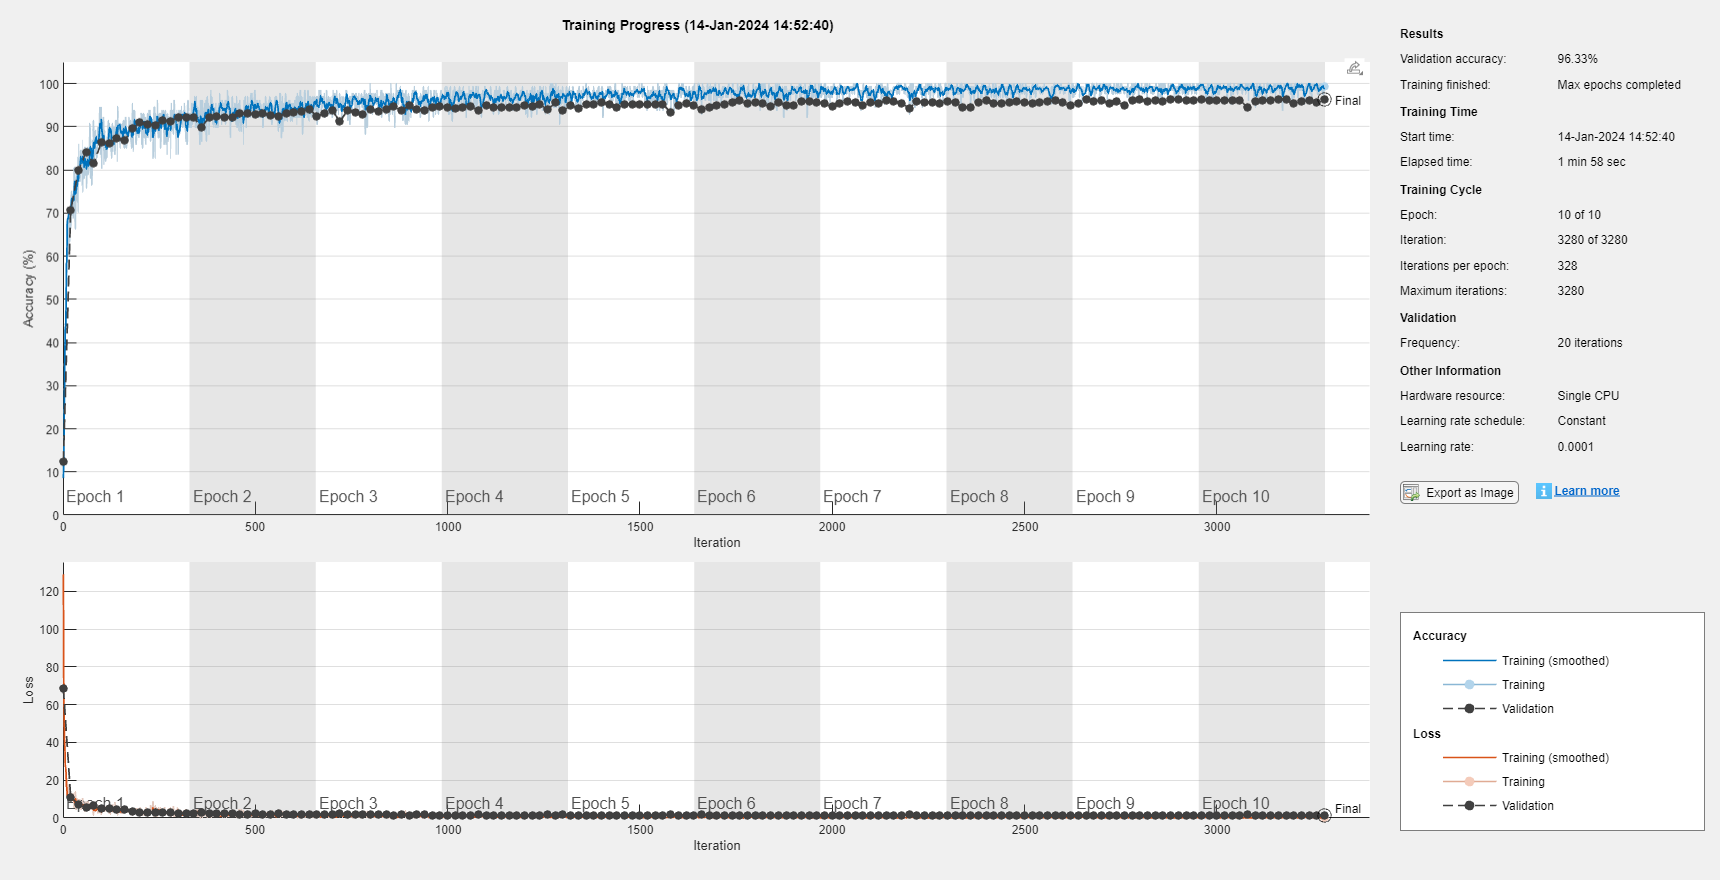

net1 =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


traininfo1 = struct with fields:
               TrainingLoss: [129.0262 69.6808 50.5703 40.0943 37.1177 26.9659 26.8518 23.6386 16.3730 20.6753 11.5448 10.6225 17.4250 13.1847 13.0653 11.1118 15.2096 10.4091 10.0439 11.7932 12.7551 8.8991 8.9802 11.0375 10.0741 … ] (1×3280 double)
           TrainingAccuracy: [8.5938 12.5000 22.6562 30.4688 39.0625 43.7500 43.7500 48.4375 58.5938 56.2500 67.9688 68.7500 60.1562 64.0625 71.0938 69.5312 63.2812 67.9688 69.5312 66.4062 71.0938 74.2188 75 69.5312 74.2188 68.7500 … ] (1×3280 double)
             ValidationLoss: [68.4980 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 11.0264 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 7.2639 NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×3280 double)
         ValidationAccuracy: [12.4583 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 70.6667 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 79.9333 NaN NaN NaN

[net1, traininfo1] = trainNetwork(mnistTrain,layersA3,optionsS3)

[label1, score1] = classify(net1,mnistPrediction)

label1 = 5999×1 categorical array
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 


score1 = 5999×10 single matrix
    1.0000         0         0         0         0         0         0         0    0.0000    0.0000
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0    0.0000         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0    0.0000         0         0         0    0.0000
    1.0000         0         0         0         0         0

### Vérification par des métriques

#### Matrice de confusion

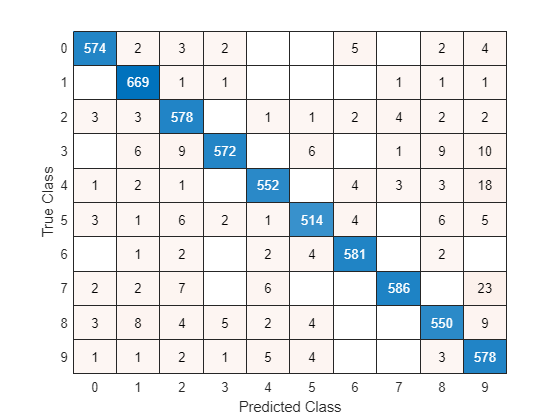

confusionchart(mnistPrediction.Labels,label1)

[c_matrix,Result,RefereceResult]= confusion.getMatrix(double(mnistPrediction.Labels),double(label1));

Class List in given sample
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


Total Instance = 5999
class1==>1
class2==>2
class3==>3
class4==>4
class5==>5
class6==>6
class7==>7
class8==>8
class9==>9
class10==>10
Confusion Matrix
                      predict_class1    predict_class2    predict_class3    predict_class4    predict_class5    predict_class6    predict_class7    predict_class8    predict_class9    predict_class10
                      ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________    _______________

    

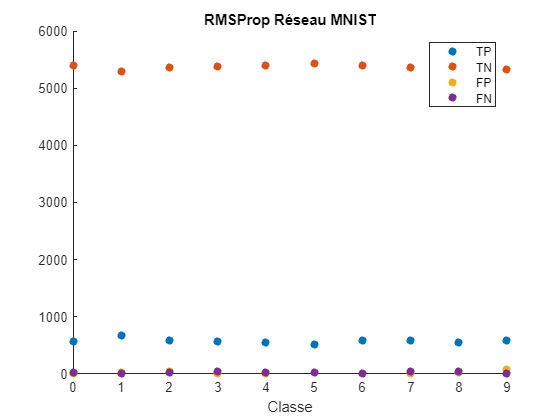

x=0:9;
scatter(x,RefereceResult.TruePositive,'filled')
hold on
scatter(x,RefereceResult.TrueNegative,'filled')
scatter(x,RefereceResult.FalsePositive,'filled')
scatter(x,RefereceResult.FalseNegative,'filled')
hold off
title("RMSProp Réseau MNIST")
legend("TP","TN","FP","FN")
xlabel("Classe")

Le solveur RMSProp (Root Mean Square Propagation) a donné des résultats encore légèrement meilleurs par rapport aux solveurs précédemment utilisés, Adam et SGDM même si les ordres de grandeurs des différentes valeurs restent les mêmes (entre 94% et 96% pour chaque paramètre à l'exception de la spécificité constamment à 99%).

Les résultats obtenus avec RMSProp ont montré une amélioration marginale dans plusieurs métriques de performance  telles que l'exactitude, la sensibilité, la spécificité, la précision et le F1-Score. Bien que ces améliorations puissent être subtiles. Cela indique que RMSProp a réussi à converger plus rapidement vers des paramètres de modèle optimaux par rapport aux solveurs précédents, ou qu'il a pu éviter certains écueils de convergence.

L'utilisation de RMSProp est donc pertinente pour optimiser notre modèle, car il a démontré sa capacité à trouver des paramètres de modèle qui généralisent bien aux données d'entraînement et qui produisent de légères améliorations dans les performances de classification.

## Conclusion sur l'optimisation du solveur

En conclusion de la partie d'optimisation de notre modèle de réseau de neurones, nous avons examiné trois solveurs couramment utilisés : Adam, SGDM (Stochastic Gradient Descent with Momentum) et RMSProp. Tous ces solveurs se sont révélés être d'excellents choix pour l'optimisation de notre modèle, produisant des résultats de classification très satisfaisants.

Adam a démontré une grande efficacité en obtenant des performances de haut niveau, tout comme SGDM, qui a montré sa robustesse dans l'entraînement de réseaux de neurones. Ces deux solveurs ont généré des résultats très compétitifs dans un large éventail de métriques de performance.

Cependant, notre choix final s'est porté sur RMSProp en raison de ses légères améliorations observées dans les performances de classification par rapport aux autres solveurs.

## Application au données Fashion MNIST 

layersA3 = [
    imageInputLayer([28 28 1])
    fullyConnectedLayer(1028)
    geluLayer
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer
    ];

deepNetworkDesigner(layersA3)

analyzeNetwork(layersA3)

optionsFS3 = trainingOptions("rmsprop", ...
    InitialLearnRate=0.0001,...   
    MaxEpochs=10, ...
    MiniBatchSize=128, ...
    ValidationFrequency=20, ...
    Plots="training-progress", ...
    ValidationData=FmnistValidation)

optionsFS3 =   TrainingOptionsRMSProp with properties:

      SquaredGradientDecayFactor: 0.9000
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-04
                       MaxEpochs: 10
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 128
                         Shuffle: 'once'
                      WorkerLoad: []
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
            DispatchInBackground: 0
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [1×1 matlab.io.datastore.ImageDatastore]
             Validati

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |        7.81% |       33.69% |     102.5919 |      45.1661 |      1.0000e-04 |
|       1 |          20 |       00:00:02 |       60.94% |       62.65% |      17.9881 |      16.4659 |      1.0000e-04 |
|       1 |          40 |       00:00:03 |       77.34% |       73.38% |      12.2193 |      10.8977 |      1.0000e-04 |
|       1 |          50 |       00:00:03 |       75.00% |              |       9.2171 |   

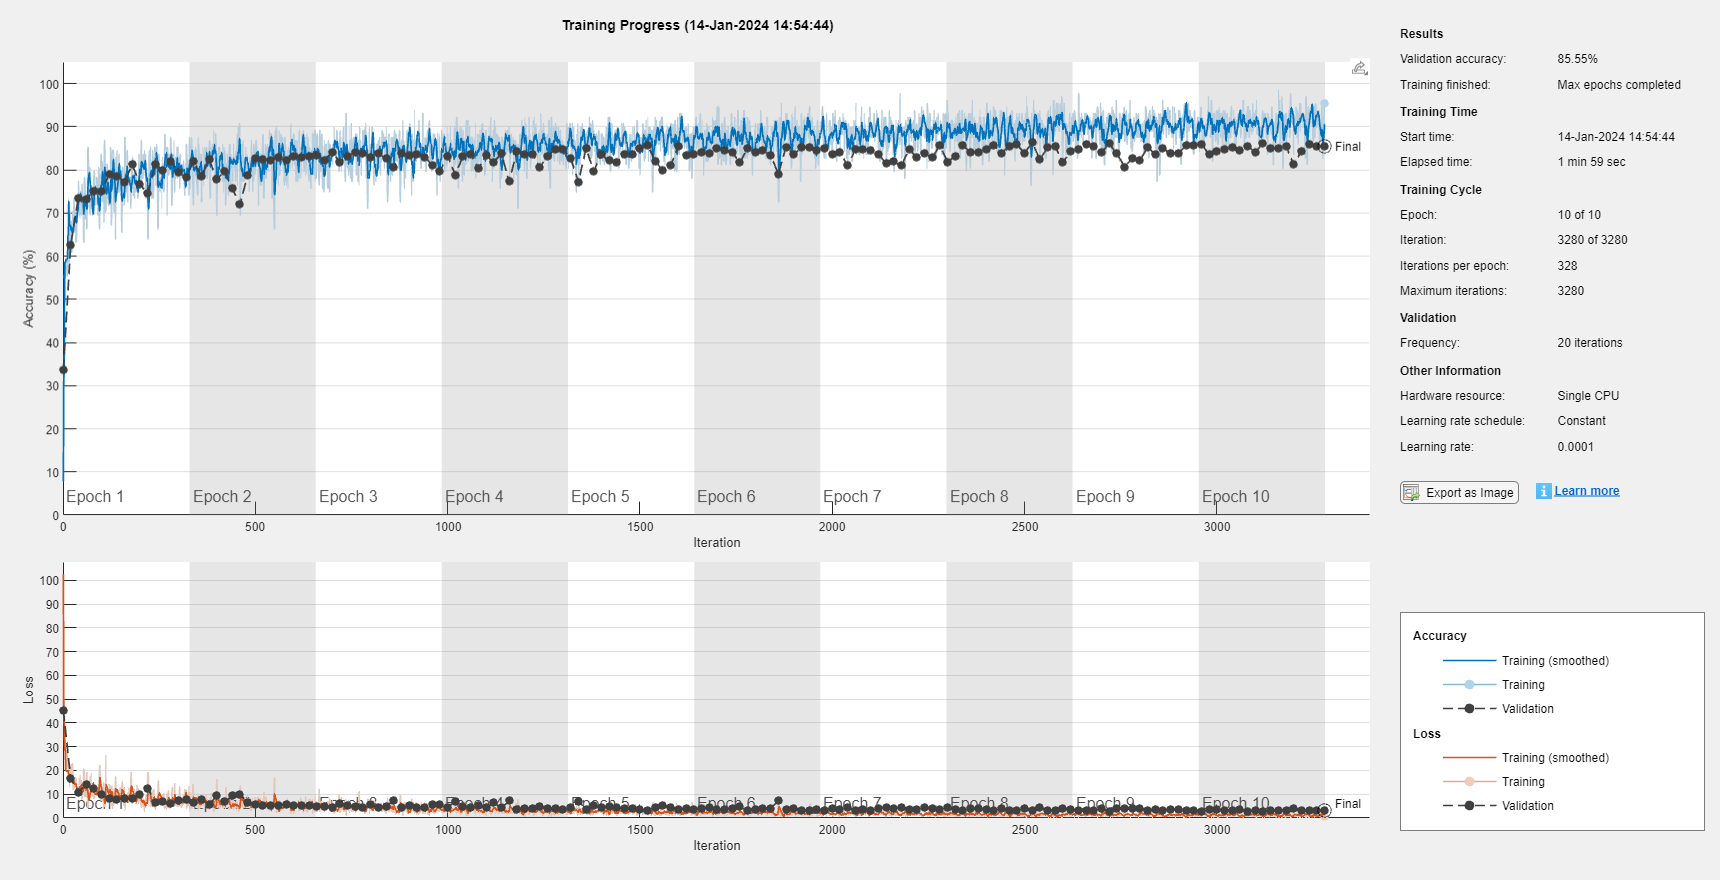

net1 =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


traininfo1 = struct with fields:
               TrainingLoss: [102.5919 41.6125 49.0356 31.9416 28.6256 33.8609 20.0217 22.7022 19.7507 22.3753 27.9271 24.0914 21.7908 23.6554 16.3225 21.5881 13.5292 18.2176 15.1091 17.9881 22.5575 17.5553 15.5377 21.7236 22.7452 … ] (1×3280 double)
           TrainingAccuracy: [7.8125 32.8125 30.4688 52.3438 58.5938 58.5938 57.0312 59.3750 58.5938 59.3750 55.4688 59.3750 64.8438 58.5938 73.4375 58.5938 66.4062 70.3125 66.4062 60.9375 60.9375 67.9688 60.9375 64.0625 66.4062 … ] (1×3280 double)
             ValidationLoss: [45.1661 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 16.4659 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 10.8977 NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×3280 double)
         ValidationAccuracy: [33.6917 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 62.6500 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 73.3750 NaN NaN NaN

[net1, traininfo1] = trainNetwork(FmnistTrain,layersA3,optionsFS3)

[labelF1, scoreF1] = classify(net1,FmnistPrediction)

labelF1 = 6000×1 categorical array
     0 
     0 
     0 
     0 
     0 
     0 
     3 
     0 
     6 
     0 
     0 
     0 
     2 
     2 
     6 
     0 
     0 
     0 
     6 
     0 
     0 
     0 
     6 
     0 
     3 
     3 
     0 
     6 
     0 
     0 


scoreF1 = 6000×10 single matrix
    1.0000    0.0000    0.0000    0.0000         0         0    0.0000         0    0.0000         0
    1.0000         0    0.0000         0         0         0    0.0000         0    0.0000         0
    1.0000         0    0.0000    0.0000         0         0    0.0000         0    0.0000         0
    0.9998         0    0.0000    0.0000         0         0    0.0002         0         0         0
    1.0000    0.0000    0.0000    0.0000    0.0000         0    0.0000         0         0         0
    1.0000         0    0.0000         0         0         0    0.0000         0         0         0
    0.0000    0.0000    0.0000    1.0000    0.0000         0    0.0000    0.0000    0.0000         0
    1.0000         0    0.0000    0.0000    0.0000    0.0000    0.0000         0    0.0000         0
    0.0000    0.0000    0.0000    0.0000         0         0    1.0000         0    0.0000         0
    1.0000         0    0.0000    0.0000         0         

Exactitude de 86%. Rien de particulier à mentionner pour ce cas précis comme cela était attendu. La différence entrre ce modèle et le dernier est très légère.

# IV) Optimisation du learning rate

Le learning rate, ou taux d'apprentissage en français, est un hyperparamètre essentiel dans le processus d'entraînement des réseaux de neurones et d'autres algorithmes d'apprentissage automatique. Il détermine la taille des pas que l'optimiseur effectue lors de la mise à jour des poids du modèle à chaque itération d'entraînement. En d'autres termes, il contrôle la vitesse à laquelle le modèle apprend à partir des données.

Un learning rate trop élevé peut entraîner une convergence rapide, mais il risque également de faire osciller l'optimisation autour du minimum global, ce qui peut entraîner une instabilité ou un mauvais apprentissage. À l'inverse, un learning rate trop faible peut entraîner une convergence très lente, voire stagner à un minimum local sans atteindre la convergence globale.

Par conséquent, il est essentiel de choisir judicieusement la valeur du learning rate pour chaque tâche d'entraînement. Cela peut nécessiter une expérimentation en testant différentes valeurs pour trouver celle qui fonctionne le mieux pour un modèle spécifique et un jeu de données donné.

Dans le cadre de notre optimisation, nous allons essayer plusieurs valeurs de learning rate pour déterminer celle qui offre les meilleures performances de classification pour notre modèle de réseau de neurones.

## 1) InitialLearnRate = 0.0001

Pour commencer, un initialLearnRate de 0.0001 va réduire la vitesse d'apprentissage du modèle, ce qui peut être bénéfique pour la stabilité de l'entraînement, mais cela peut également ralentir la convergence. Il sera peut être nécessaire de l'ajuster lors de l'expérimentation pour obtenir les meilleurs résultats de classification.

layersA3 = [
    imageInputLayer([28 28 1])
    fullyConnectedLayer(1028)
    geluLayer
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer
    ];

deepNetworkDesigner(layersA3)

analyzeNetwork(layersA3)

On modifie la valeur correspondante au terme "InitialLearnRate".

optionsS3I1 = trainingOptions("rmsprop", ...
    InitialLearnRate=0.0001,...   
    MaxEpochs=10, ...
    MiniBatchSize=128, ...
    ValidationFrequency=20, ...
    Plots="training-progress", ...
    ValidationData=mnistValidation)

optionsS3I1 =   TrainingOptionsRMSProp with properties:

      SquaredGradientDecayFactor: 0.9000
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-04
                       MaxEpochs: 10
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 128
                         Shuffle: 'once'
                      WorkerLoad: []
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
            DispatchInBackground: 0
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [1×1 matlab.io.datastore.ImageDatastore]
             Validat

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |       10.94% |       17.48% |     118.6380 |      72.4808 |      1.0000e-04 |
|       1 |          20 |       00:00:02 |       66.41% |       69.62% |      12.2603 |      12.0654 |      1.0000e-04 |
|       1 |          40 |       00:00:03 |       79.69% |       79.52% |       9.4464 |       7.6057 |      1.0000e-04 |
|       1 |          50 |       00:00:03 |       81.25% |              |       6.5337 |   

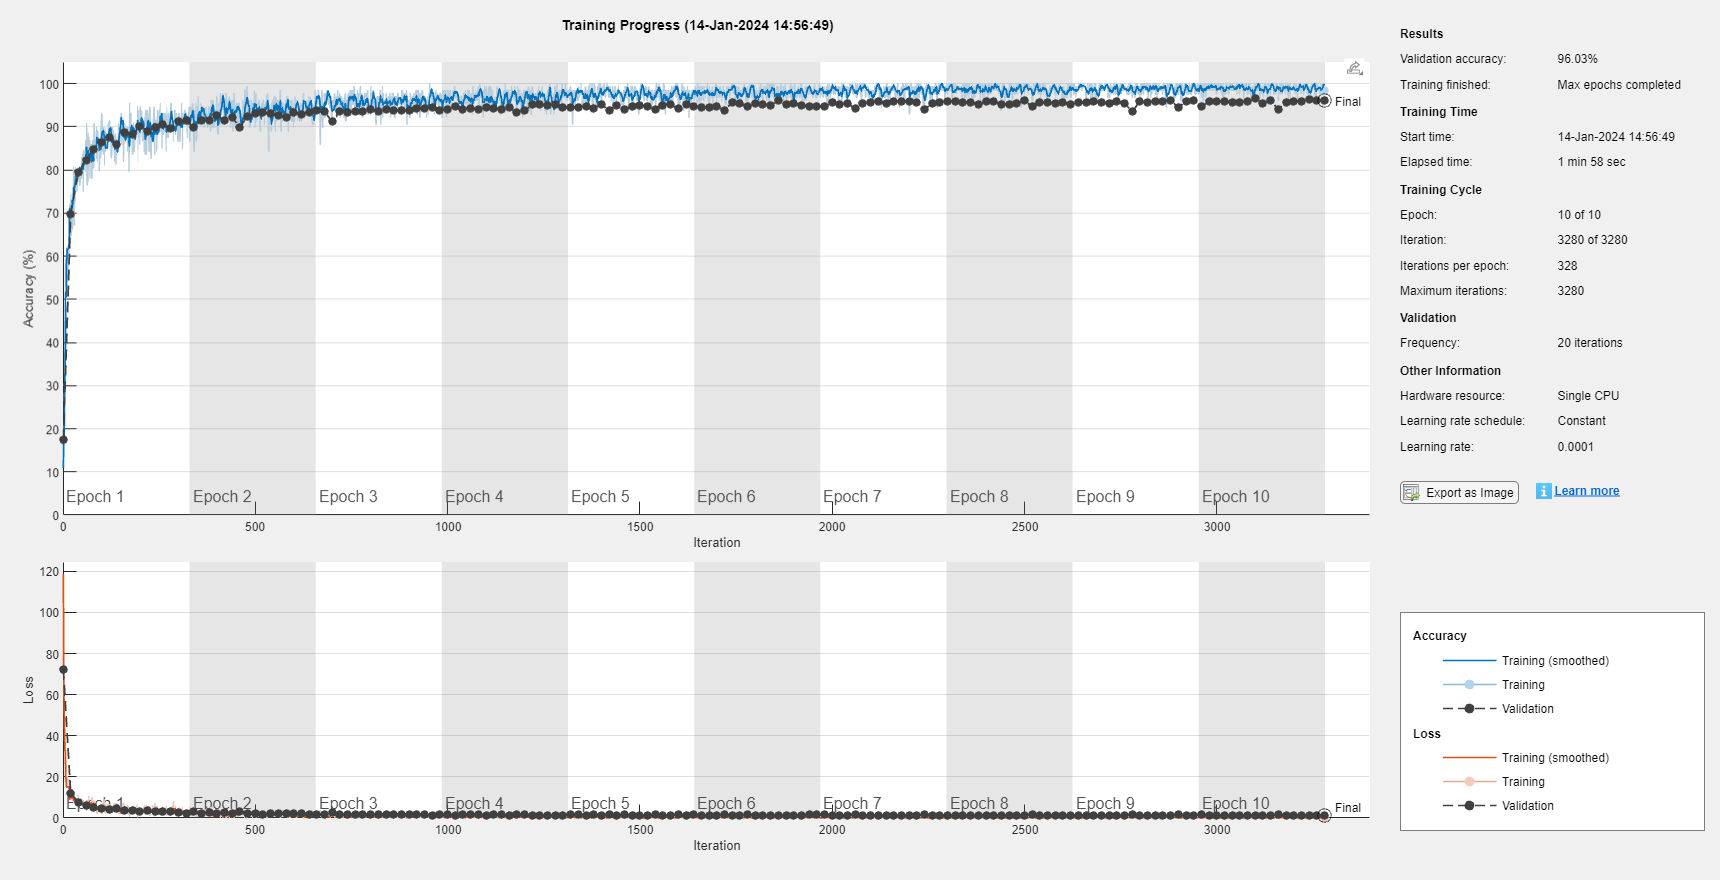

net1 =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


traininfo1 = struct with fields:
               TrainingLoss: [118.6380 67.7054 52.6460 42.2146 32.9296 35.2789 19.1313 29.3102 15.1321 20.2290 19.8696 16.9079 18.9137 17.9308 18.6090 16.5390 8.9613 12.6624 16.1985 12.2603 8.9023 10.6990 10.0262 13.6834 11.1898 … ] (1×3280 double)
           TrainingAccuracy: [10.9375 17.9688 17.9688 29.6875 31.2500 40.6250 59.3750 39.0625 61.7188 50.7812 54.6875 60.1562 57.0312 58.5938 62.5000 60.9375 71.8750 67.9688 64.0625 66.4062 74.2188 64.8438 71.8750 70.3125 66.4062 … ] (1×3280 double)
             ValidationLoss: [72.4808 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 12.0654 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 7.6057 NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×3280 double)
         ValidationAccuracy: [17.4750 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 69.6250 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 79.5167 NaN NaN NaN N

[net1, traininfo1] = trainNetwork(mnistTrain,layersA3,optionsS3I1)

[label1, score1] = classify(net1,mnistPrediction)

label1 = 5999×1 categorical array
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 


score1 = 5999×10 single matrix
    1.0000         0         0         0         0         0         0         0    0.0000         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0    0.0000    0.0000         0         0         0
    1.0000         0         0         0         0         0

### Vérification par des métriques

#### Matrice de confusion

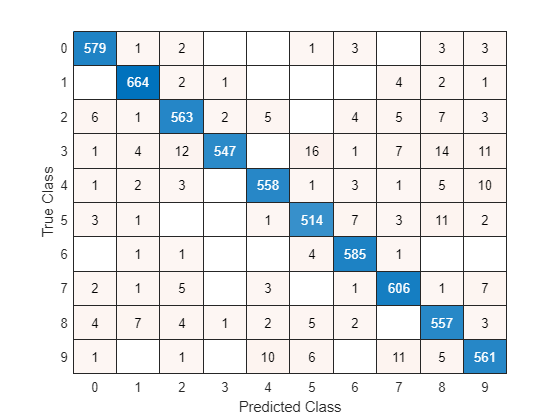

confusionchart(mnistPrediction.Labels,label1)

[c_matrix,Result,RefereceResult]= confusion.getMatrix(double(mnistPrediction.Labels),double(label1));

Class List in given sample
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


Total Instance = 5999
class1==>1
class2==>2
class3==>3
class4==>4
class5==>5
class6==>6
class7==>7
class8==>8
class9==>9
class10==>10
Confusion Matrix
                      predict_class1    predict_class2    predict_class3    predict_class4    predict_class5    predict_class6    predict_class7    predict_class8    predict_class9    predict_class10
                      ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________    _______________

    

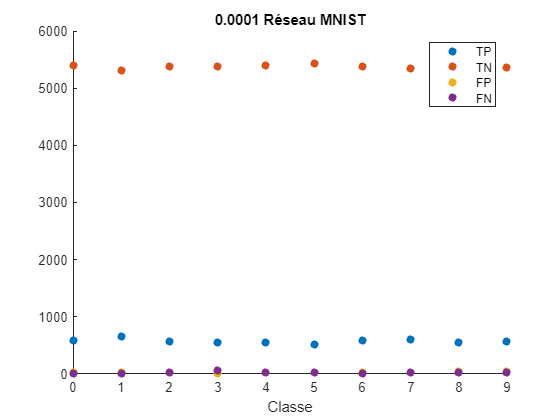

x=0:9;
scatter(x,RefereceResult.TruePositive,'filled')
hold on
scatter(x,RefereceResult.TrueNegative,'filled')
scatter(x,RefereceResult.FalsePositive,'filled')
scatter(x,RefereceResult.FalseNegative,'filled')
hold off
title("0.0001 Réseau MNIST")
legend("TP","TN","FP","FN")
xlabel("Classe")

Effectivement, un learning rate de 0.0001 est la même valeur que nous avons utilisée depuis le début de notre étude, et il n'est donc pas surprenant que cela nous donne des résultats extrêmement similaires au modèle précédent. Cette valeur de learning rate a déjà été testée et validée dans nos expériences antérieures, et elle a montré sa capacité à produire des résultats de classification satisfaisants.

L'idée derrière cette répétition est de maintenir une constance dans nos expériences pour pouvoir comparer les performances du modèle avec différentes valeurs de learning rate. En utilisant la même valeur de 0.0001 comme point de référence, nous pouvons évaluer l'impact des changements de learning rate sur les performances de classification et déterminer s'il existe une valeur qui pourrait potentiellement améliorer ces performances de manière significative.

## 2) InitialLearnRate = 0.0000001

Un initialLearnRate de 0.0000001 est une valeur extrêmement faible, bien plus petite que celle que nous avons utilisée précédemment (0.0001). Le modèle va progresser à un rythme extrêmement lent. Les mises à jour des poids seront très petites, ce qui signifie que le modèle apprendra très peu à chaque itération. En conséquence, la convergence vers un minimum global ou optimal sera extrêmement lente, voire peut-être impossible à atteindre dans un nombre d'itérations raisonnable.Un learning rate aussi bas rendra également l'entraînement très stable. Les oscillations et les sauts brusques dans les valeurs des poids seront minimes, ce qui peut être bénéfique pour la stabilité numérique et pour éviter tout comportement instable pendant l'entraînement. Cependant, un risque de stagnation sera considérablement accru. Le modèle peut rester bloqué dans un minimum local ou simplement ne pas converger du tout en raison de la lenteur du learning rate.

Testons la valeur.

layersA3 = [
    imageInputLayer([28 28 1])
    fullyConnectedLayer(1028)
    geluLayer
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer
    ];

deepNetworkDesigner(layersA3)

analyzeNetwork(layersA3)

optionsS3I2 = trainingOptions("rmsprop", ...
    InitialLearnRate=0.0000001,...   
    MaxEpochs=10, ...
    MiniBatchSize=128, ...
    ValidationFrequency=20, ...
    Plots="training-progress", ...
    ValidationData=mnistValidation)

optionsS3I2 =   TrainingOptionsRMSProp with properties:

      SquaredGradientDecayFactor: 0.9000
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-07
                       MaxEpochs: 10
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 128
                         Shuffle: 'once'
                      WorkerLoad: []
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
            DispatchInBackground: 0
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [1×1 matlab.io.datastore.ImageDatastore]
             Validat

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |       14.06% |        9.96% |      90.6113 |     103.8378 |      1.0000e-07 |
|       1 |          20 |       00:00:02 |        7.81% |        9.97% |     112.1257 |     103.2210 |      1.0000e-07 |
|       1 |          40 |       00:00:03 |       10.16% |       10.02% |     103.4475 |     102.7419 |      1.0000e-07 |
|       1 |          50 |       00:00:03 |       10.94% |              |      94.0109 |   

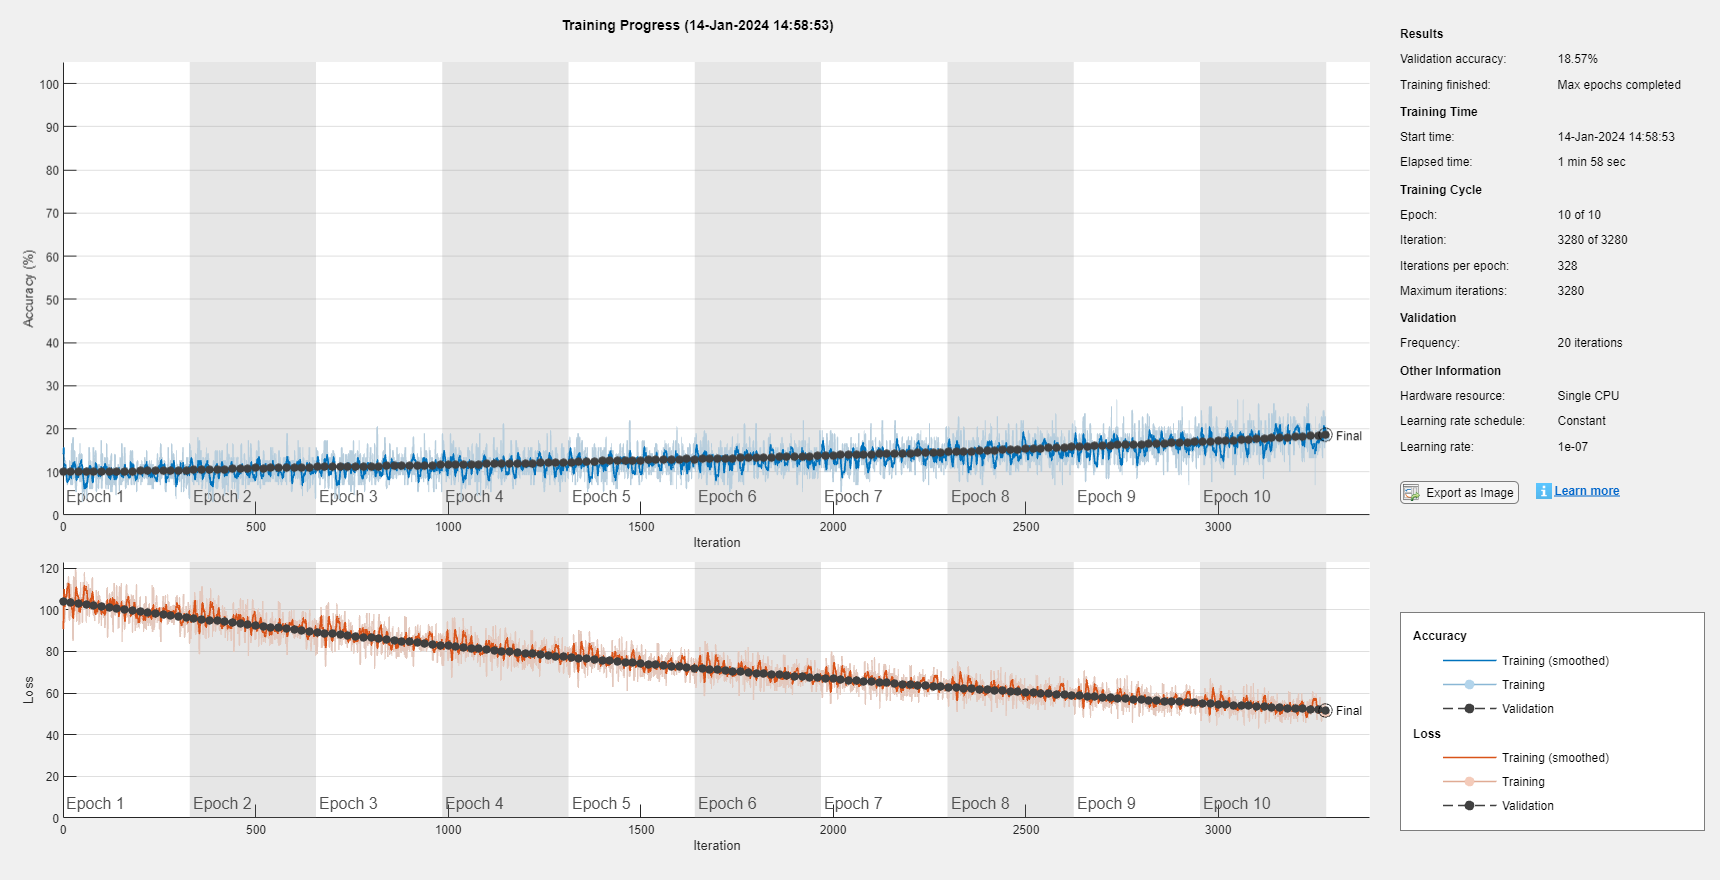

net1 =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


traininfo1 = struct with fields:
               TrainingLoss: [90.6113 104.8017 109.7412 93.9595 100.5397 107.1309 105.5023 104.6173 104.5172 109.4799 112.7564 109.3207 106.3195 115.8902 108.2352 96.3444 94.9523 103.3981 106.9988 112.1257 104.5454 96.9723 96.7422 … ] (1×3280 double)
           TrainingAccuracy: [14.0625 15.6250 9.3750 13.2812 11.7188 12.5000 10.9375 10.1562 7.8125 8.5938 7.0312 9.3750 10.1562 10.1562 10.1562 8.5938 12.5000 9.3750 7.8125 7.8125 7.0312 11.7188 16.4062 7.0312 9.3750 17.9688 11.7188 … ] (1×3280 double)
             ValidationLoss: [103.8378 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 103.2210 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 102.7419 NaN NaN NaN NaN NaN NaN NaN … ] (1×3280 double)
         ValidationAccuracy: [9.9583 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 9.9750 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 10.0167 NaN NaN N

[net1, traininfo1] = trainNetwork(mnistTrain,layersA3,optionsS3I2)

[label1, score1] = classify(net1,mnistPrediction)

label1 = 5999×1 categorical array
     5 
     0 
     5 
     0 
     2 
     6 
     6 
     5 
     2 
     9 
     2 
     0 
     8 
     2 
     0 
     5 
     5 
     6 
     0 
     9 
     2 
     9 
     4 
     4 
     5 
     2 
     5 
     6 
     5 
     8 


score1 = 5999×10 single matrix
    0.0000    0.0000    0.0000         0    0.0000    1.0000    0.0000         0         0    0.0000
    1.0000    0.0000    0.0000    0.0000         0    0.0000    0.0000         0    0.0000    0.0000
    0.0011    0.0000    0.0000         0         0    0.9989    0.0000         0    0.0000    0.0000
    1.0000    0.0000         0         0    0.0000    0.0000    0.0000         0    0.0000         0
         0         0    1.0000         0         0    0.0000         0         0    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000         0    0.0000    0.0000
    0.2985    0.0000    0.0000    0.0000    0.0000    0.0000    0.7015         0    0.0000         0
         0         0    0.0000    0.0000    0.0000    1.0000    0.0000         0         0    0.0000
    0.0000    0.0000    0.8704    0.0000    0.0000    0.0000    0.1010    0.0000    0.0000    0.0286
    0.0000    0.0000    0.0000         0    0.0000    0.0000

### Vérification par des métriques

#### Matrice de confusion

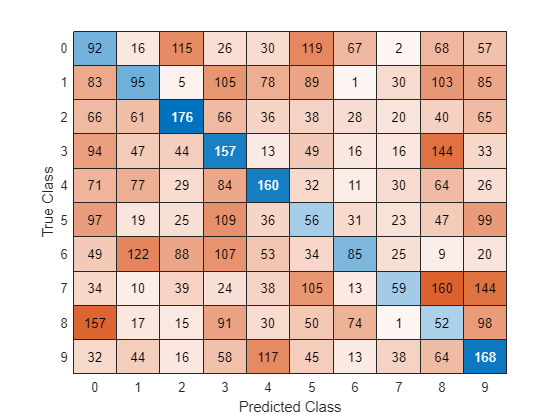

confusionchart(mnistPrediction.Labels,label1)

[c_matrix,Result,RefereceResult]= confusion.getMatrix(double(mnistPrediction.Labels),double(label1));

Class List in given sample
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


Total Instance = 5999
class1==>1
class2==>2
class3==>3
class4==>4
class5==>5
class6==>6
class7==>7
class8==>8
class9==>9
class10==>10
Confusion Matrix
                      predict_class1    predict_class2    predict_class3    predict_class4    predict_class5    predict_class6    predict_class7    predict_class8    predict_class9    predict_class10
                      ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________    _______________

    

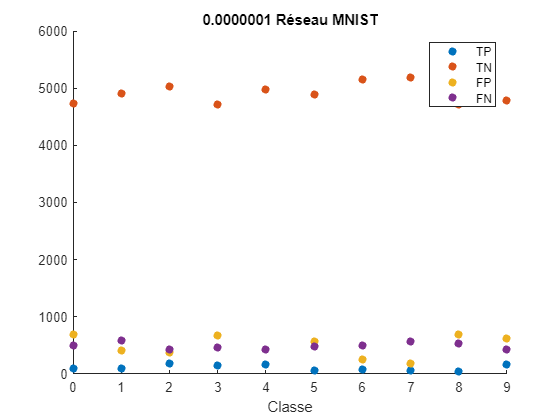

x=0:9;
scatter(x,RefereceResult.TruePositive,'filled')
hold on
scatter(x,RefereceResult.TrueNegative,'filled')
scatter(x,RefereceResult.FalsePositive,'filled')
scatter(x,RefereceResult.FalseNegative,'filled')
hold off
title("0.0000001 Réseau MNIST")
legend("TP","TN","FP","FN")
xlabel("Classe")

Comme prévu, le modèle a progressé de manière extrêmement lente avec un initialLearnRate de 0.0000001. La faiblesse du learning rate a eu pour effet de ralentir considérablement le processus d'apprentissage, au point où le modèle n'a pas beaucoup appris et n'a même jamais atteint un minimum optimal.

Les résultats obtenus sont encore pires que prévu, avec une accuracy de seulement 18%. C'est un score très bas par rapport aux performances que nous avons eu l'habitude d'obtenir avec un learning rate plus élevé. Le modèle n'a pas réussi à bien généraliser les données d'entraînement et qu'il est resté dans un état de sous-apprentissage.

Pour rendre cette valeur de learning rate viable, il aurait fallu un nombre d'itérations d'entraînement immensément grand, ce qui aurait nécessité des ressources de calcul considérables.

Les résultats obtenus avec un initialLearnRate de 0.0000001 sont bien en deçà des attentes, cette valeur est donc à écarter.

## 3) InitialLearnRate = 10

Un initialLearnRate de 10 est une valeur extrêmement élevée pour le learning rate, bien supérieure à celles que nous avons utilisées précédemment ce qui aura un impact significatif sur le processus d'entraînement de notre modèle de réseau de neurones. Avec un initialLearnRate aussi élevé, le modèle va progresser très rapidement lors de l'entraînement. Les mises à jour des poids seront de grande amplitude, ce qui permettra une convergence rapide vers un minimum. Cependant, un learning rate aussi élevé peut rendre l'entraînement instable. Les mises à jour de poids de grande amplitude peuvent entraîner des oscillations et des sauts brusques dans les valeurs des poids, l'optimisation peut devenir chaotique et le modèle peut ne pas converger du tout, voir il peut subir de l'overfiting.

layersA3 = [
    imageInputLayer([28 28 1])
    fullyConnectedLayer(1028)
    geluLayer
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer
    ];

deepNetworkDesigner(layersA3)

analyzeNetwork(layersA3)

optionsS3I3 = trainingOptions("rmsprop", ...
    InitialLearnRate=10,...   
    MaxEpochs=10, ...
    MiniBatchSize=128, ...
    ValidationFrequency=20, ...
    Plots="training-progress", ...
    ValidationData=mnistValidation)

optionsS3I3 =   TrainingOptionsRMSProp with properties:

      SquaredGradientDecayFactor: 0.9000
                         Epsilon: 1.0000e-08
                InitialLearnRate: 10
                       MaxEpochs: 10
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 128
                         Shuffle: 'once'
                      WorkerLoad: []
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
            DispatchInBackground: 0
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [1×1 matlab.io.datastore.ImageDatastore]
             ValidationFrequ

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |        7.03% |        9.75% |      89.7221 |   6.8226e+09 |         10.0000 |
|       1 |          20 |       00:00:02 |       75.78% |       70.33% |   9.0494e+06 |   1.0834e+07 |         10.0000 |
|       1 |          40 |       00:00:03 |       72.66% |       80.41% |   1.1425e+07 |   6.2482e+06 |         10.0000 |
|       1 |          50 |       00:00:03 |       76.56% |              |   2.5396e+07 |   

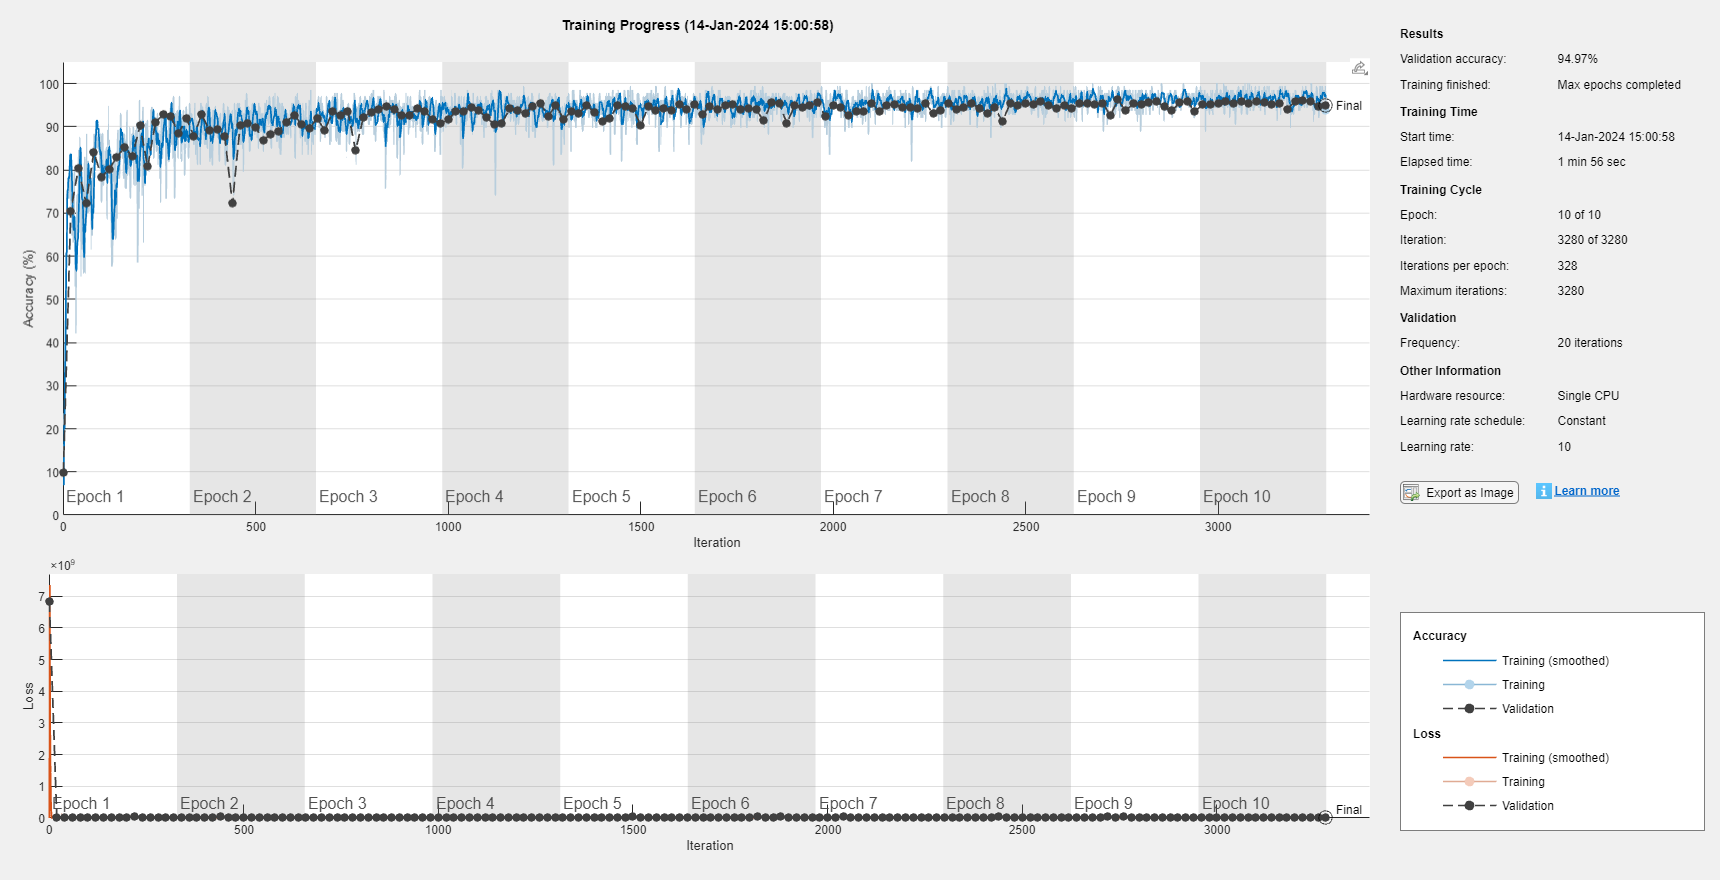

net1 =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


traininfo1 = struct with fields:
               TrainingLoss: [89.7221 7.3330e+09 629384832 644525312 321258592 233886272 101463104 50754984 35556652 44616168 13302258 9501810 13021518 6947349 6.2765e+06 6764892 10625589 5453913 6843210 9049378 8832378 8743866 … ] (1×3280 double)
           TrainingAccuracy: [7.0312 7.0312 23.4375 16.4062 37.5000 33.5938 45.3125 60.1562 60.9375 60.1562 75 73.4375 75.7812 78.1250 73.4375 75.7812 79.6875 82.0312 83.5938 75.7812 71.8750 74.2188 71.8750 64.8438 70.3125 63.2812 … ] (1×3280 double)
             ValidationLoss: [6.8226e+09 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 10833962 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 6.2482e+06 NaN NaN NaN NaN NaN NaN … ] (1×3280 double)
         ValidationAccuracy: [9.7500 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 70.3333 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 80.4083 NaN NaN NaN Na

[net1, traininfo1] = trainNetwork(mnistTrain,layersA3,optionsS3I3)

[label1, score1] = classify(net1,mnistPrediction)

label1 = 5999×1 categorical array
     8 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     2 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 


score1 = 5999×10 single matrix
     0     0     0     0     0     0     0     0     1     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0


### Vérification par des métriques

#### Matrice de confusion

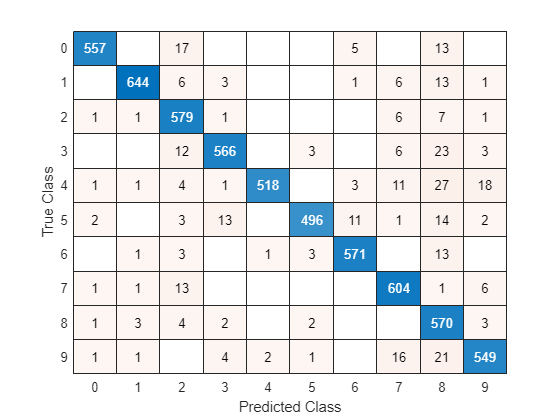

confusionchart(mnistPrediction.Labels,label1)

[c_matrix,Result,RefereceResult]= confusion.getMatrix(double(mnistPrediction.Labels),double(label1));

Class List in given sample
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


Total Instance = 5999
class1==>1
class2==>2
class3==>3
class4==>4
class5==>5
class6==>6
class7==>7
class8==>8
class9==>9
class10==>10
Confusion Matrix
                      predict_class1    predict_class2    predict_class3    predict_class4    predict_class5    predict_class6    predict_class7    predict_class8    predict_class9    predict_class10
                      ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________    _______________

    

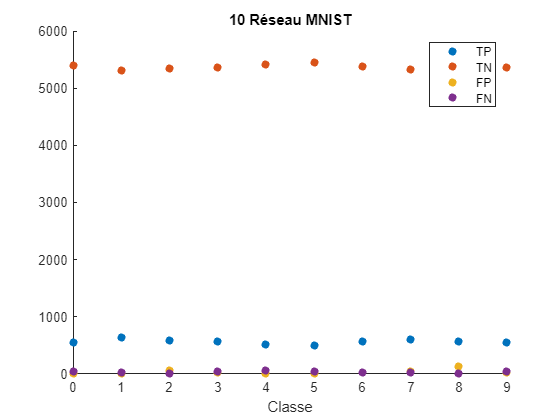

x=0:9;
scatter(x,RefereceResult.TruePositive,'filled')
hold on
scatter(x,RefereceResult.TrueNegative,'filled')
scatter(x,RefereceResult.FalsePositive,'filled')
scatter(x,RefereceResult.FalseNegative,'filled')
hold off
title("10 Réseau MNIST")
legend("TP","TN","FP","FN")
xlabel("Classe")

Ce modèle avec un learning rate de 10 ne produit pas de mauvais résultats, bien au contraire. Avec une accuracy de 94%, il atteint des performances de classification similaires à celles du modèle avec un learning rate de 0.0001, qui a été notre point de référence précédent. Cela démontre que, malgré son learning rate élevé, le modèle est capable d'apprendre efficacement et de bien généraliser sur les données.

Cependant, lorsqu'on examine de plus près l'entraînement du modèle, on peut remarquer quelques sauts d'amplitude dans les valeurs des poids. Ces sauts occasionnels dans les poids du modèle sont des indicateurs que le modèle reste légèrement instable en raison du learning rate élevé. Bien que ces sauts ne nuisent pas gravement aux performances finales du modèle, ils témoignent de l'instabilité potentielle induite par un learning rate aussi élevé.

En somme, le modèle avec un learning rate de 10 offre de bonnes performances de classification, similaires à celles d'un modèle avec un learning rate plus faible, mais il présente une légère instabilité lors de l'entraînement. 

## Conclusion sur le Learning Rate

Nous avons examiné trois valeurs de learning rate différentes pour notre modèle de réseau de neurones : 0.0001, 0.0000001 et 10. Après avoir analysé leurs performances, il est clair que le learning rate de 0.0001 reste l'option la plus stable et équilibrée. Il offre une convergence efficace et des résultats de classification solides, sans les problèmes d'instabilité ou de lenteur associés aux autres valeurs de learning rate testées. Par conséquent, nous continuerons à utiliser un learning rate de 0.0001 car il représente un compromis optimal entre vitesse d'apprentissage et stabilité.

# Application Finale

layersA3 = [
    imageInputLayer([28 28 1])
    fullyConnectedLayer(1028)
    geluLayer
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer
    ];

deepNetworkDesigner(layersA3)

analyzeNetwork(layersA3)

FoptionsS3I1B1 = trainingOptions("rmsprop", ...
    InitialLearnRate=0.0001,...   
    MaxEpochs=10, ...
    MiniBatchSize=128, ...
    ValidationFrequency=20, ...
    Plots="training-progress", ...
    ValidationData=FmnistValidation)

FoptionsS3I1B1 =   TrainingOptionsRMSProp with properties:

      SquaredGradientDecayFactor: 0.9000
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-04
                       MaxEpochs: 10
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 128
                         Shuffle: 'once'
                      WorkerLoad: []
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
            DispatchInBackground: 0
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [1×1 matlab.io.datastore.ImageDatastore]
             Vali

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |        5.47% |       15.04% |     150.8199 |      81.3424 |      1.0000e-04 |
|       1 |          20 |       00:00:02 |       70.31% |       67.14% |      19.8019 |      14.1845 |      1.0000e-04 |
|       1 |          40 |       00:00:03 |       71.09% |       67.71% |      14.0351 |      13.8947 |      1.0000e-04 |
|       1 |          50 |       00:00:03 |       72.66% |              |      12.9311 |   

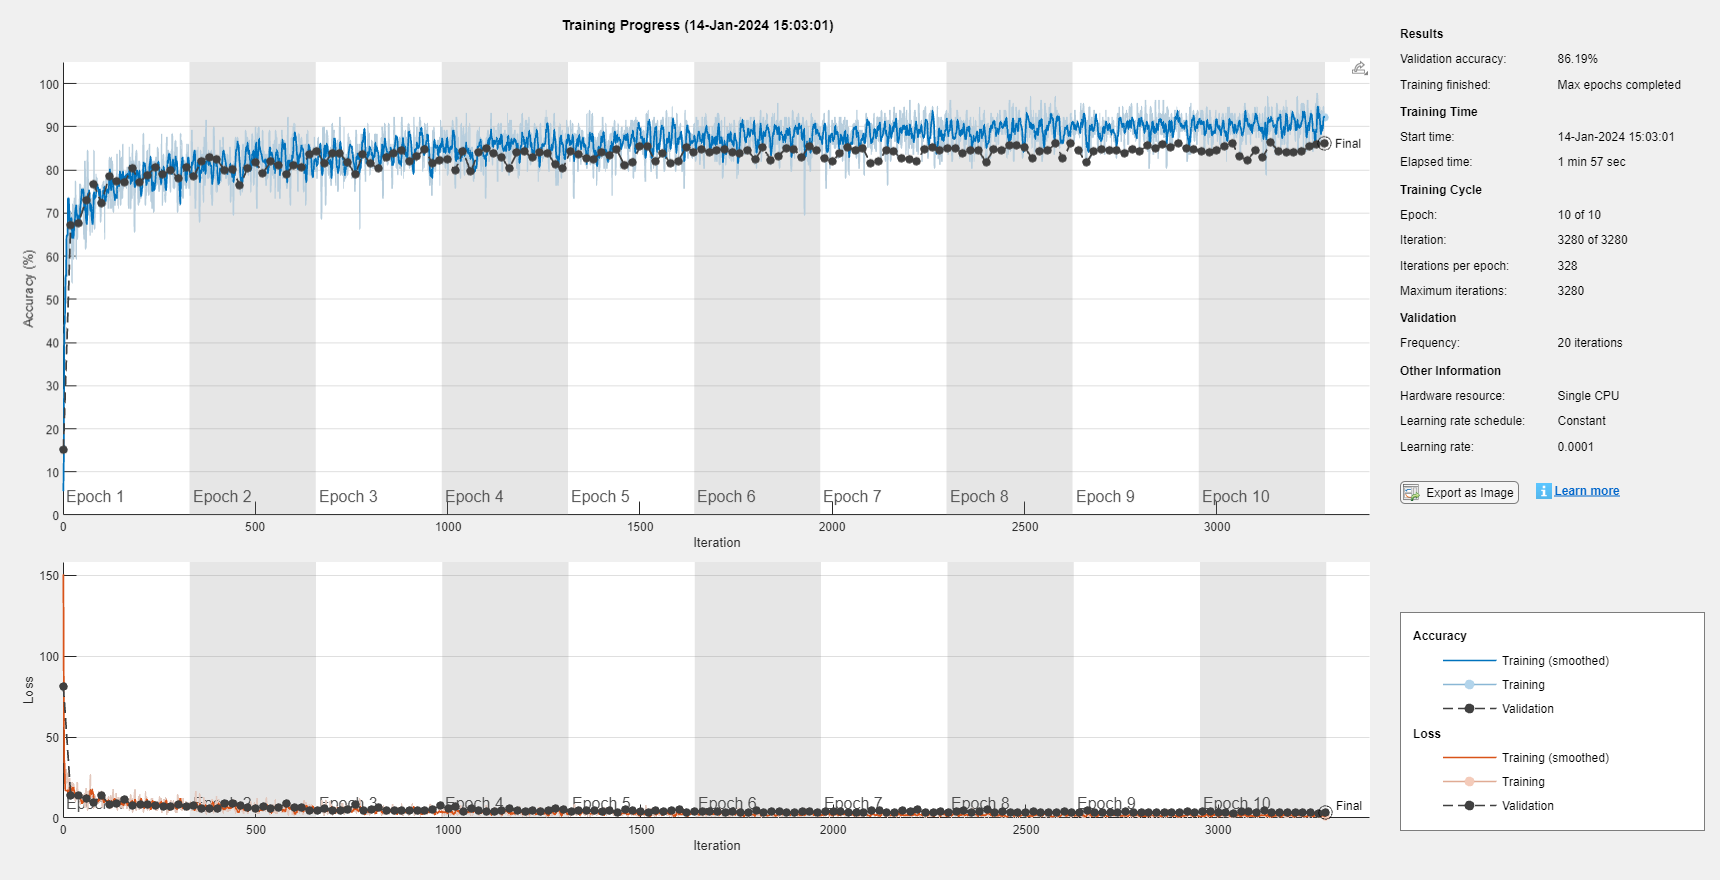

net1 =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


traininfo1 = struct with fields:
               TrainingLoss: [150.8199 86.3449 34.1205 35.5577 22.2412 17.0458 28.3498 29.8972 21.8408 22.5962 22.1485 27.6314 13.0229 16.0789 21.0218 23.1719 24.4917 17.7919 19.0351 19.8019 15.4808 15.2143 21.5951 21.5404 14.0010 … ] (1×3280 double)
           TrainingAccuracy: [5.4688 12.5000 41.4062 44.5312 44.5312 54.6875 55.4688 49.2188 64.0625 64.8438 55.4688 62.5000 73.4375 67.9688 60.1562 57.8125 63.2812 65.6250 67.1875 70.3125 67.9688 67.1875 64.0625 53.9062 71.8750 … ] (1×3280 double)
             ValidationLoss: [81.3424 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 14.1845 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 13.8947 NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×3280 double)
         ValidationAccuracy: [15.0417 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 67.1417 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 67.7083 NaN NaN NaN

[net1, traininfo1] = trainNetwork(FmnistTrain,layersA3,FoptionsS3I1B1)

[labelF1, scoreF1] = classify(net1,FmnistPrediction)

labelF1 = 6000×1 categorical array
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     2 
     2 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     3 
     0 
     0 
     0 
     0 
     0 


scoreF1 = 6000×10 single matrix
    1.0000    0.0000    0.0000    0.0000    0.0000         0    0.0000    0.0000    0.0000         0
    1.0000         0    0.0000         0         0         0    0.0000         0    0.0000         0
    1.0000         0    0.0000         0         0         0    0.0000         0    0.0000         0
    1.0000         0    0.0000         0         0         0    0.0000         0         0         0
    1.0000    0.0000    0.0000    0.0000         0         0    0.0000         0         0         0
    1.0000         0    0.0000         0         0         0    0.0000         0         0         0
    1.0000         0    0.0000    0.0000    0.0000         0    0.0000    0.0000    0.0000         0
    0.9786    0.0000    0.0000    0.0000         0    0.0000    0.0214         0    0.0000         0
    0.9999    0.0000    0.0000    0.0000    0.0000         0    0.0001    0.0000    0.0000         0
    1.0000    0.0000    0.0000    0.0000         0         

### Vérification par des métriques

#### Matrice de confusion

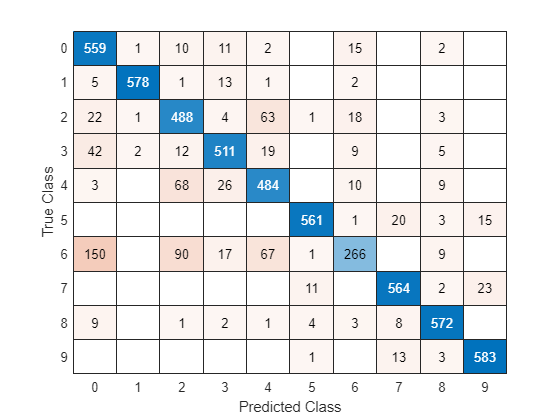

confusionchart(FmnistPrediction.Labels,labelF1)

[c_matrix,Result,RefereceResult]= confusion.getMatrix(double(FmnistPrediction.Labels),double(label1));

Class List in given sample
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


Total Instance = 6000
class1==>1
class2==>2
class3==>3
class4==>4
class5==>5
class6==>6
class7==>7
class8==>8
class9==>9
class10==>10
Confusion Matrix
                      predict_class1    predict_class2    predict_class3    predict_class4    predict_class5    predict_class6    predict_class7    predict_class8    predict_class9    predict_class10
                      ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________    _______________

    

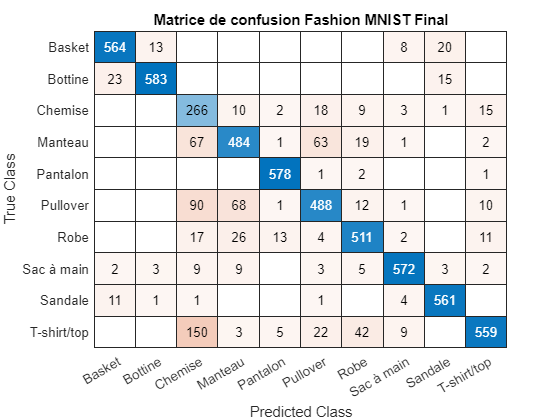

% Définition des étiquettes personnalisées
Fclasses = {'T-shirt/top', 'Pantalon', 'Pullover', 'Robe', 'Manteau', 'Sandale', 'Chemise', 'Basket', 'Sac à main', 'Bottine'};

% Convertir les indices en étiquettes de classe
predictedLabels = Fclasses(FmnistPrediction.Labels);
trueLabels = Fclasses(labelF1);

% Création de la matrice de confusion avec les étiquettes personnalisées
cm = confusionchart(trueLabels, predictedLabels);

% Titre de la matrice de confusion
title("Matrice de confusion Fashion MNIST Final")

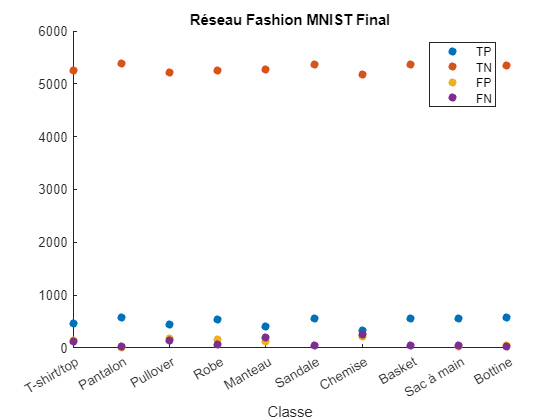

%Définition des étiquettes personnalisées
Fclasses = {'T-shirt/top', 'Pantalon', 'Pullover', 'Robe', 'Manteau', 'Sandale', 'Chemise', 'Basket', 'Sac à main', 'Bottine'};

% Affichage du graphique
x = 0:9;
scatter(x, FRefereceResult.TruePositive, 'filled')
hold on
scatter(x, FRefereceResult.TrueNegative, 'filled')
scatter(x, FRefereceResult.FalsePositive, 'filled')
scatter(x, FRefereceResult.FalseNegative, 'filled')
hold off

% Appliquer les étiquettes personnalisées sur l'axe x
xticks(x);
xticklabels(Fclasses);

title("Réseau Fashion MNIST Final")
legend("TP", "TN", "FP", "FN")
xlabel("Classe")

save('A369748_rendu_mat.mat')

Au final, au cours de notre processus d'optimisation des réseaux de neurones pour la classification des données MNIST et Fashion MNIST, nous avons exploré et ajusté plusieurs paramètres clés pour améliorer les performances de nos modèles. Nous avons passé en revue des éléments tels que le nombre de neurones dans la couche cachée, l'activateur utilisé, le solveur d'optimisation, et la valeur du learning rate.

Tout d'abord, nous avons étudié l'impact du nombre de neurones dans la couche cachée. Après plusieurs expériences, nous avons conclu que 1024 neurones étaient le choix optimal, offrant un équilibre entre performance et temps d'entraînement, tout en évitant le surapprentissage. Ensuite, nous avons exploré différents activateurs, notamment ReLU, ELU, GeLU et tanh. Tous ces activateurs ont montré des performances solides, mais GeLU s'est légèrement démarqué en fournissant des résultats légèrement supérieurs. Nous avons également comparé trois solveurs populaires, Adam, SGDM et RMSProp, et avons constaté que les performances étaient similaires entre les trois, montrant qu'ils sont tous de bons choix pour l'optimisation des réseaux de neurones malgré notre choix de retenir le solveur RMSProp. Enfin, en ce qui concerne le learning rate, une valeur de 0.0001 a montré des résultats cohérents et satisfaisants tout au long de notre étude.

Nos modèles ont atteint des performances globalement satisfaisantes, avec des accuracies atteignant jusqu'à 86% pour les données Fashion MNIST et des valeurs d'erreur réduites à 14%. La sensibilité, la spécificité, la précision et le F1-score ont également montré des améliorations significatives, ce qui indique que nos modèles sont capables de bien généraliser sur les données de test. Pour preuve, ci-dessous nous pouvons observer l'évolution des métriques. Les chiffres de notre premier modèle sont comparés à ceux de notre aplication final :

Accuracy : 83 -> 86% 

Error : 17 -> 14% 

Sensitivity : 83 -> 86% 

Specificity : 98 -> 98% 

Precision : 83 -> 87% 

F1 score : 83 -> 86%

Cependant, il est important de noter que nos optimisations ont été effectuées de manière indépendante pour chaque paramètre, ce qui ne capture pas nécessairement les interactions complexes entre ces paramètres. Idéalement, une optimisation conjointe aurait pu être plus efficace pour obtenir des performances optimales. De plus, nos modèles pourraient encore être améliorés en utilisant des techniques avancées telles que l'ajustement des hyperparamètres, la régularisation et l'augmentation des données.

En conclusion, notre processus d'optimisation a abouti à des modèles de réseau de neurones performants  et satisfaisant pour la classification des données MNIST et Fashion MNISTt mais il existe toujours des possibilités d'amélioration, et des approches plus avancées pourraient être envisagées à l'avenir pour tirer le meilleur parti de ces données.